# Toy problems in SE(2)

## Group Actions

Let's start by initializing two arbitrary SE(2) group elements `g `and `h`.

We shall be visualizing their vector and matrix forms (group actions happen when they are in their matrix form).

% Initialize the variables to work with:
syms x y theta u v beta real

% V2M M2V functions:
v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

% Group action functions:
L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

% Group lifted-actiion functions:
T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

% Define the vector form of two points in our group 'g', 'h', and 'e':
g_vec = [x;
         y;
         theta]

$$g\_vec = \left(\begin{array}{c} x\\ y\\ \theta \end{array}\right)$$

h_vec = [u;
         v;
         beta]

$$h\_vec = \left(\begin{array}{c} u\\ v\\ \beta \end{array}\right)$$

e_vec = [0;
         0;
         0] % 'e' is the identity and in a more traditional sense the origin for the manifold

e_vec =      0
     0
     0


% Get the matrix forms for these vectors:
g_mat = v2M_SE2(g_vec)

$$g\_mat = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & x\\ \sin\left(\theta \right) & \cos\left(\theta \right) & y\\ 0 & 0 & 1 \end{array}\right)$$

h_mat = v2M_SE2(h_vec)

$$h\_mat = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & u\\ \sin\left(\beta \right) & \cos\left(\beta \right) & v\\ 0 & 0 & 1 \end{array}\right)$$

e_mat = v2M_SE2(e_vec)

e_mat =      1     0     0
     0     1     0
     0     0     1


Let's show how a group action works step-by-step,

eg = simplify(h_mat*g_mat, 'Steps', 10)

$$eg = \left(\begin{array}{ccc} \cos\left(\beta +\theta \right) & -\sin\left(\beta +\theta \right) & u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ \sin\left(\beta +\theta \right) & \cos\left(\beta +\theta \right) & v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ 0 & 0 & 1 \end{array}\right)$$

Now, if we write it in the vector form, we get,

eg = simplify([eg(1,3); 
          eg(2,3);
          atan(eg(2,1)/eg(1,1))], 'Steps', 10, 'IgnoreAnalyticConstraints', true)

$$eg = \left(\begin{array}{c} u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ \beta +\theta \end{array}\right)$$

The angles have obviously added up, and the vector $\left\lbrack x,y\right\rbrack$ is rotated by $\beta$. 

We shall use the previously functions to do the rest of the computation,

% Let's perform some group actions as a sanity check ~ matrix first, then
% vector form
hg_vec = L_h_ofg(g_vec, h_vec)

$$hg\_vec = \left(\begin{array}{c} u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ \beta +\theta \end{array}\right)$$

gh_vec = R_h_ofg(g_vec, h_vec)

$$gh\_vec = \left(\begin{array}{c} x+u\,\cos\left(\theta \right)-v\,\sin\left(\theta \right)\\ y+v\,\cos\left(\theta \right)+u\,\sin\left(\theta \right)\\ \beta +\theta \end{array}\right)$$

## Group Lifted Actions - Mapping tangent spaces

Next, we shall implement the left and right lifted actions that map velocities in 'g' to velocities in 'gh' or 'hg',

% Now, we can try lifted actions:
T_g_to_T_hg = T_gL_h(g_vec, h_vec)

$$T\_g\_to\_T\_hg = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & 0\\ \sin\left(\beta \right) & \cos\left(\beta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T_g_to_T_gh = T_gR_h(g_vec, h_vec)

$$T\_g\_to\_T\_gh = \left(\begin{array}{ccc} 1 & 0 & -v\,\cos\left(\theta \right)-u\,\sin\left(\theta \right)\\ 0 & 1 & u\,\cos\left(\theta \right)-v\,\sin\left(\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

These results match the equations described in section A.3 of  this paper [https://link.springer.com/article/10.1140/epjst/e2015-50085-y](https://link.springer.com/article/10.1140/epjst/e2015-50085-y) 

With this understanding, we can try to replicate results in section 3.1.2 in the same paper. Some important lifted actions that will help us define local (body frame) velocity, global (rest frame) velocity, and spatial velocity (think what velocity should the global frame have to produce the same body velocity relatively) are needed to conclude this review before moving onto an example.

% Compute the inverse of a group element -- we do this by first converting
% it to the matrix form, then take its inverse, and finally pull it back to
% the vector form.
gInv_mat = simplify(inv(g_mat), 'Steps', 10)

$$gInv\_mat = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & -x\,\cos\left(\theta \right)-y\,\sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & x\,\sin\left(\theta \right)-y\,\cos\left(\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

gInv_vec = M2v_SE2(gInv_mat)

$$gInv\_vec = \left(\begin{array}{c} -x\,\cos\left(\theta \right)-y\,\sin\left(\theta \right)\\ x\,\sin\left(\theta \right)-y\,\cos\left(\theta \right)\\ -\theta \end{array}\right)$$

In order to obtain the ***body velocity*** from the global velocity, we need to map from the tangent space at global frame to the tangent space at the body frame of the robot (tangent space is the space where the velocities of group elements are defined -- $\forall g \in G$, $\dot{g} \in T_e G$),


$$\overset{\circ}{\text{g}} = \frac{\partial{e}}{\partial{g}} \dot{g} = \frac{\partial{g^{-1} g}}{\partial{g}} \dot{g} = T_g L_{g^{-1}} \: \dot{g}$$


Since, we already have $g^{-1}$, we can get the corresponding left-lifted action,

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]))

$$TgLgInv = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Similar to this, we can get the ***spatial velocity***,


$$\overset{\circ}{\text{g}^S} = \frac{\partial{e}}{\partial{g}} \dot{g} = \frac{\partial{g g^{-1}}}{\partial{g}} \dot{g} = T_g R_{g^{-1}} \: \dot{g}$$


TgRgInv = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]))

$$TgRgInv = \left(\begin{array}{ccc} 1 & 0 & y\\ 0 & 1 & -x\\ 0 & 0 & 1 \end{array}\right)$$

Wwe compute the global velocity from body velocity as follows,


$$\dot{g} = \frac{\partial{g}}{\partial{e}} \: \overset{\circ}{\text{g}} = \frac{\partial{ge}}{\partial{e}} \: \overset{\circ}{\text{g}} = T_e L_g \: \overset{\circ}{\text{g}}$$


TeLg = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]))

$$TeLg = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

And finally, we compute the global velocity from spatial velocity,


$$\dot{g} = \frac{\partial{g}}{\partial{e}} \: \overset{\circ}{\text{g}^S} = \frac{\partial{eg}}{\partial{e}} \: \overset{\circ}{\text{g}^S} = T_e R_g \: \overset{\circ}{\text{g}^S}$$


TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]))

$$TeRg = \left(\begin{array}{ccc} 1 & 0 & -y\\ 0 & 1 & x\\ 0 & 0 & 1 \end{array}\right)$$

As expected, it just rotates the body frame velocity by $\theta \;\ldotp$

## Adjoint inverse maps in the tangent space

The adjoint-inverse mapping encodes the transfer of velocity between frames on a rigid body. It can be split up into two successive transformations,

- cross product

- inverse rotation

The adjoint-inverse of map between tangent spaces $T_{h_1} G$ and $T_{h_i} G$ is $ \overset{\circ}{\text{h}_i} = Ad^{-1}_{g}  \overset{\circ}{\text{h}_1}$, where g is the transformation between the group elements. Using our initial definition of $g = (x, y, \theta)$, the adjoint inverse map $Ad^{-1}_{g}$ is given by,


$$\left\lbrack \begin{array}{ccc}
\cos \;\theta  & \sin \;\theta  & 0\\
-\sin \;\theta  & \cos \;\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & -y\\
0 & 1 & x\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \;\theta  & \sin \;\theta  & x\;\sin \;\theta \;-y\;\cos \;\theta \;\\
-\sin \;\theta  & \cos \;\theta  & x\;\cos \;\theta \;+y\;\sin \;\theta \\
0 & 0 & 0
\end{array}\right\rbrack$$


Let's now define this as an inline function to use later,

AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

## 2-legged system with pins at the foot

Consider an SE(2) system with 2 legs at diametrically opposite ends of a disk centered at the body center, and the right foot is highlighted in the figure below because it is pinned to the ground.

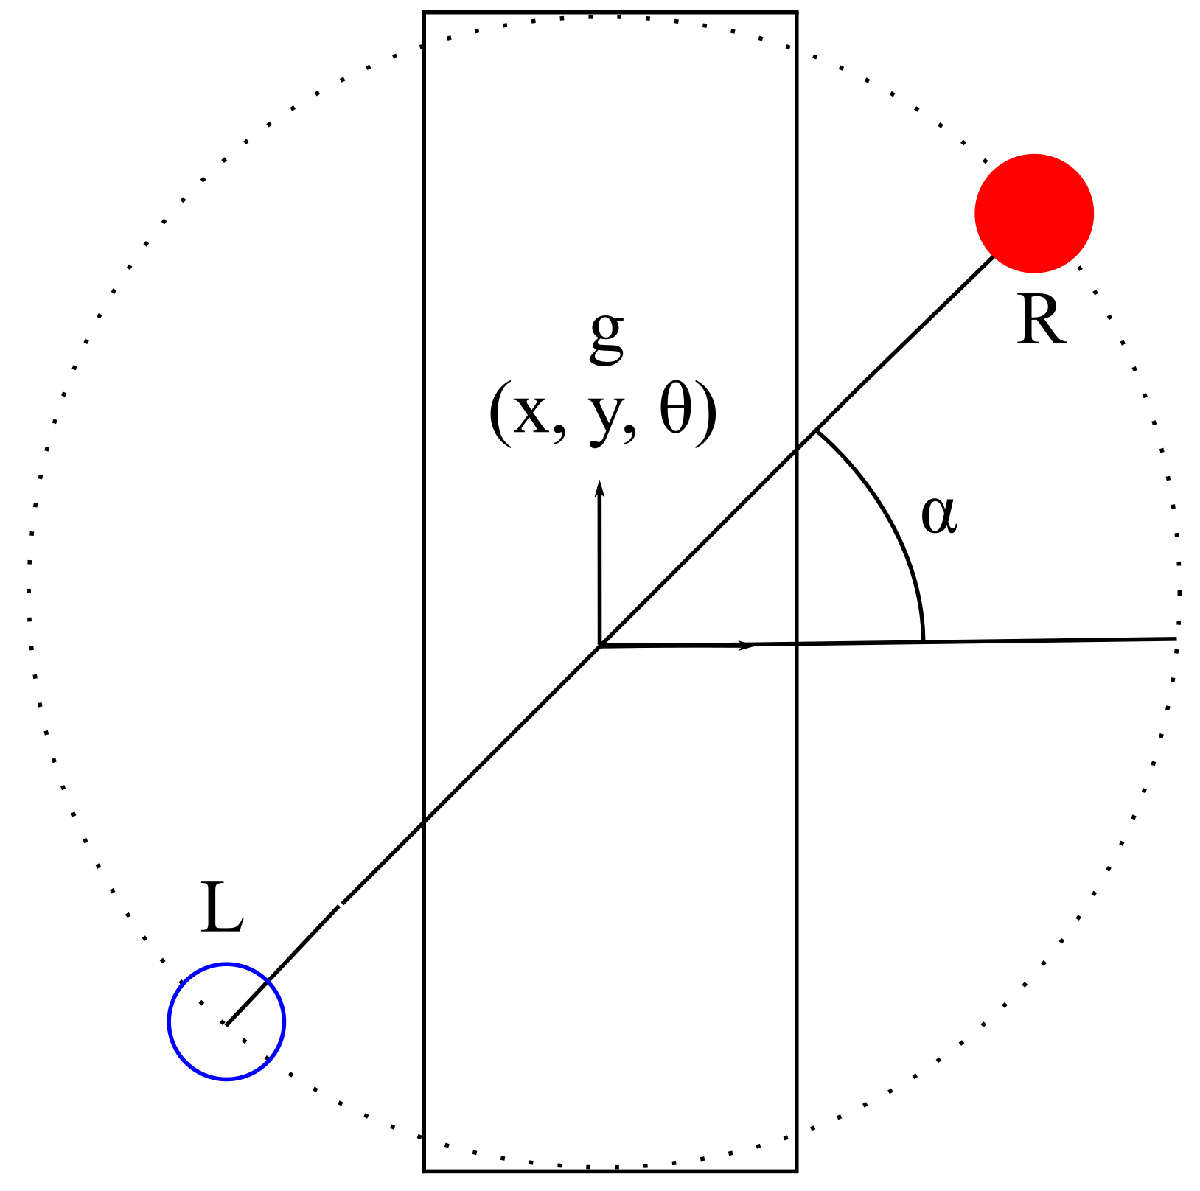

### Transforms and Jacobians

The transforms (denoted by 'h' and the frame name in the subscript) to the feet are pretty straightforward,

syms r alpha alpha_dot real
% Transform to the right leg:
h_R = [r*cos(alpha);
       r*sin(alpha);
       alpha]

$$h\_R = \left(\begin{array}{c} r\,\cos\left(\alpha \right)\\ r\,\sin\left(\alpha \right)\\ \alpha \end{array}\right)$$

% Transform to the left leg:
h_L = [r*cos(pi + alpha);
       r*sin(pi + alpha);
       pi + alpha]

$$h\_L = \left(\begin{array}{c} -r\,\cos\left(\alpha \right)\\ -r\,\sin\left(\alpha \right)\\ \alpha +\pi \end{array}\right)$$

With this, we can now get mappings of the velocities attached to the feet to the center of mass frame ***g*** velocity through the adjoint inverse map,

AdjInv_R = AdjInvMap(h_R)

$$AdjInv\_R = \left(\begin{array}{ccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & r\\ 0 & 0 & 1 \end{array}\right)$$

AdjInv_L = AdjInvMap(h_L)

$$AdjInv\_L = \left(\begin{array}{ccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & r\\ 0 & 0 & 1 \end{array}\right)$$

Now, in order to include the influence of the rotation of the disk $\dot{\;\alpha \;}$, we repeat the third column of the adjoint inverse map we just generated to get the complete foot jacobians as shown below,

footJacobian_R = [AdjInv_R, AdjInv_R(:,end)]

$$footJacobian\_R = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & r & r\\ 0 & 0 & 1 & 1 \end{array}\right)$$

footJacobian_L = [AdjInv_L, AdjInv_L(:,end)]

$$footJacobian\_L = \left(\begin{array}{cccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & r & r\\ 0 & 0 & 1 & 1 \end{array}\right)$$

### Connection

Alright, now we can talk about assumptions on the system,

- The anchored foot is not allowed to translate, but can pivot

- The COM frame is allowed to translate, but not rotate

Incorporating this into our right foot jacobian, and swap the column on the LHS with the third column on the RHS to express this as a Pfaffian constraint,


$$\left(\begin{array}{c}
0 \\
0 \\
\overset{\circ}{g^R_{\theta}} \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha \right) & \sin \left(\alpha \right) & 0 & 0\\
-\sin \left(\alpha \right) & \cos \left(\alpha \right) & r & r\\
0 & 0 & 1 & 1
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
0 \\
\dot{\alpha} \\
\end{array}\right)
 
\Longrightarrow$$
 
$$\left(\begin{array}{c}
0 \\
0 \\
0 \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha \right) & \sin \left(\alpha \right) & 0 & 0\\
-\sin \left(\alpha \right) & \cos \left(\alpha \right) & 0 & r\\
0 & 0 & -1 & 1
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
\overset{\circ}{g^R_\theta} \\
\dot{\alpha} \\
\end{array}\right) $$


And we shall do the same for the other leg.

omega_R = footJacobian_R; omega_R(:,3) = [0; 0; -1]

$$omega\_R = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & r\\ 0 & 0 & -1 & 1 \end{array}\right)$$

omega_L = footJacobian_L; omega_L(:,3) = [0; 0; -1]

$$omega\_L = \left(\begin{array}{cccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & 0 & r\\ 0 & 0 & -1 & 1 \end{array}\right)$$

Now, we can finally obtain the connection for each foot distinctly,

A_R = -simplify(omega_R(:,1:3)\omega_R(:,4:end))

$$A\_R = \left(\begin{array}{c} r\,\sin\left(\alpha \right)\\ -r\,\cos\left(\alpha \right)\\ 1 \end{array}\right)$$

A_L = -simplify(omega_L(:,1:3)\omega_L(:,4:end))

$$A\_L = \left(\begin{array}{c} -r\,\sin\left(\alpha \right)\\ r\,\cos\left(\alpha \right)\\ 1 \end{array}\right)$$

And there we have our binary switching-mode connections assuming only one leg gets to stay on the ground.

### **Velocity of the unpinned leg**

Let's first assume the ***right leg is pinned to the ground***, and from our connection, we can write out the body velocity as follows,

gcirc__1_r = [1, 0, 0;
            0, 1, 0;
            0, 0, 0]*A_R*alpha_dot % the small r denotes which leg is fixed on the ground

$$gcirc\_\_1\_r = \left(\begin{array}{c} \dot{\alpha }\,r\,\sin\left(\alpha \right)\\ -\dot{\alpha }\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

The velocity of the unpinned leg can be obtained by doing another adjoint transformation with respect to *g*  and $\dot{\alpha \;}$,

simplify(footJacobian_L*[gcirc__1_r; alpha_dot])

$$ans = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

Similarly, if the left-leg is anchored and the right-leg drags along, we can obtain a similar expression,

gcirc__1_l = [1, 0, 0;
            0, 1, 0;
            0, 0, 0]*A_L*alpha_dot

$$gcirc\_\_1\_l = \left(\begin{array}{c} -\dot{\alpha }\,r\,\sin\left(\alpha \right)\\ \dot{\alpha }\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

gcirc__R_l = simplify(footJacobian_R*[gcirc__1_l; alpha_dot])

$$gcirc\_\_R\_l = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

**The velocities are identical since the frames have the same sense of rotation and are diametrically opposite. Hence, we should have the same power dissipation formulation which will be worked out below **(and we shall just call the dissipation P since it will be the same irrespective of which leg gets to be anchored).

gcirc = gcirc__R_l

$$gcirc = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

Let's start by defining translational viscous friction acting on the passive leg that gets dragged along,

syms nu positive
viscTrans_friction_Mat = -nu*[1, 0, 0;
                              0, 1, 0;
                              0, 0, 0]

$$viscTrans\_friction\_Mat = \left(\begin{array}{ccc} -\nu & 0 & 0\\ 0 & -\nu & 0\\ 0 & 0 & 0 \end{array}\right)$$

P = gcirc' * viscTrans_friction_Mat * gcirc

$$P = -4\,{\dot{\alpha }}^{2}\,\nu \,r^{2}$$

Let's say the the drag matrix $D^{\alpha \;}$is the riemannian metric on the joint space, such that pathlengths $s$ are equal to the time required to traverse paths in the shape space at constant unit power dissipation (quoting **DOI:** [10.1109/TRO.2019.2915424](https://doi.org/10.1109/TRO.2019.2915424)).


$$s = \int \sqrt{d\alpha^T D^\alpha d\alpha}$$


After summing the power lost in all links and interacting frames, the power loss expression assumes a weighted inner-product form with $\dot{\alpha}$,


$$P = \sum_i P_i = \dot{\alpha}^T (\sum_i J_i^{\alpha, T} D_i J_i^\alpha) \dot{\alpha}$$


where, the summation in the middle is the the drag matrix $D^{\alpha \;}$.

D_alpha = P/(alpha_dot^2)

$$D\_alpha = -4\,\nu \,r^{2}$$

## The general case: connection and dissipation metric for the different leg angles

There are a few issues when it comes to computing the connection if in the general case we consider the legs to be independently controlled -- $\alpha_1$ and $\alpha_2$. Unlike the serial link case, each leg-angle only controls the corresponding leg-link and hence, the full jacobian is expected to have a column for zeros for every other joint.

syms r_1 r_2 alpha_1 alpha_2 alpha_dot_1 alpha_dot_2 real
h_R = [r_1*cos(alpha_1);
       r_1*sin(alpha_1);
       alpha_1]

$$h\_R = \left(\begin{array}{c} r_{1}\,\cos\left(\alpha_{1}\right)\\ r_{1}\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

h_L = [r_2*cos(alpha_2);
       r_2*sin(alpha_2);
       alpha_2]

$$h\_L = \left(\begin{array}{c} r_{2}\,\cos\left(\alpha_{2}\right)\\ r_{2}\,\sin\left(\alpha_{2}\right)\\ \alpha_{2} \end{array}\right)$$

AdjInv_R = AdjInvMap(h_R)

$$AdjInv\_R = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & r_{1}\\ 0 & 0 & 1 \end{array}\right)$$

AdjInv_L = AdjInvMap(h_L)

$$AdjInv\_L = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & r_{2}\\ 0 & 0 & 1 \end{array}\right)$$


footJacobian_R = [AdjInv_R, AdjInv_R*[0,0,1]', AdjInv_R*[0,0,0]']

$$footJacobian\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & r_{1} & r_{1} & 0\\ 0 & 0 & 1 & 1 & 0 \end{array}\right)$$

footJacobian_L = [AdjInv_L, AdjInv_L*[0,0,0]', AdjInv_L*[0,0,1]']

$$footJacobian\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & r_{2} & 0 & r_{2}\\ 0 & 0 & 1 & 0 & 1 \end{array}\right)$$

### Modes 1 & 2: Anchored right and left legs

As mentioned earlier, the column corresponding to the joint of the other leg should be empty. Rederiving the connections and dissipation metric,


$$\left(\begin{array}{c}
0 \\
0 \\
\overset{\circ}{g^R_{\theta}} \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha_1 \right) & \sin \left(\alpha_1 \right) & 0 & 0 & 0\\
-\sin \left(\alpha_1 \right) & \cos \left(\alpha_1 \right) & r_1 & r_1 & 0\\
0 & 0 & 1 & 1 & 0
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
0 \\
\dot{\alpha}_1 \\
\dot{\alpha}_2
\end{array}\right)
 
\Longrightarrow$$
 
$$\left(\begin{array}{c}
0 \\
0 \\
0 \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha_1 \right) & \sin \left(\alpha_1 \right) & 0 & 0 & 0\\
-\sin \left(\alpha_1 \right) & \cos \left(\alpha_1 \right) & 0 & r_1 & 0\\
0 & 0 & -1 & 1 & 0
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
\overset{\circ}{g^R_\theta} \\
\dot{\alpha}_1 \\
\dot{\alpha}_2
\end{array}\right) $$


omega_R = footJacobian_R; omega_R(:,3) = [0, 0, -1]'

$$omega\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & 0 & r_{1} & 0\\ 0 & 0 & -1 & 1 & 0 \end{array}\right)$$

omega_L = footJacobian_L; omega_L(:,3) = [0, 0, -1]'

$$omega\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & 0 & 0 & r_{2}\\ 0 & 0 & -1 & 0 & 1 \end{array}\right)$$

A_R = -simplify(omega_R(:,1:3)\omega_R(:,4:end))

$$A\_R = \left(\begin{array}{cc} r_{1}\,\sin\left(\alpha_{1}\right) & 0\\ -r_{1}\,\cos\left(\alpha_{1}\right) & 0\\ 1 & 0 \end{array}\right)$$

A_L = -simplify(omega_L(:,1:3)\omega_L(:,4:end))

$$A\_L = \left(\begin{array}{cc} 0 & r_{2}\,\sin\left(\alpha_{2}\right)\\ 0 & -r_{2}\,\cos\left(\alpha_{2}\right)\\ 0 & 1 \end{array}\right)$$

The new connection is the more general version of the connection we defined earlier based the active on-the-ground leg.

Since, we don't want the map to the rotational velocity of the pinned leg, we zero the third row of the connection maps.

A_R(3,:) = zeros(1,size(A_R,2)); A_L(3,:) = zeros(1,size(A_L,2));

### Dissipation metric in each mode

Velocity of the rigid body and unpinned leg in each case (anchored leg is denoted by a lower case r or l at the end of velocities),

gcirc__1_r = A_R*[alpha_dot_1; alpha_dot_2]

$$gcirc\_\_1\_r = \left(\begin{array}{c} {\dot{\alpha }}_{1}\,r_{1}\,\sin\left(\alpha_{1}\right)\\ -{\dot{\alpha }}_{1}\,r_{1}\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

gcirc__L_r = simplify(footJacobian_L*[gcirc__1_r; alpha_dot_1; alpha_dot_2])

$$gcirc\_\_L\_r = \left(\begin{array}{c} {\dot{\alpha }}_{1}\,r_{1}\,\sin\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{2}\,r_{2}-{\dot{\alpha }}_{1}\,r_{1}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{2} \end{array}\right)$$

gcirc__1_l = A_L*[alpha_dot_1; alpha_dot_2]

$$gcirc\_\_1\_l = \left(\begin{array}{c} {\dot{\alpha }}_{2}\,r_{2}\,\sin\left(\alpha_{2}\right)\\ -{\dot{\alpha }}_{2}\,r_{2}\,\cos\left(\alpha_{2}\right)\\ 0 \end{array}\right)$$

gcirc__R_l = simplify(footJacobian_R*[gcirc__1_l; alpha_dot_1; alpha_dot_2])

$$gcirc\_\_R\_l = \left(\begin{array}{c} -{\dot{\alpha }}_{2}\,r_{2}\,\sin\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{1}\,r_{1}-{\dot{\alpha }}_{2}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{1} \end{array}\right)$$

P_r = simplify(gcirc__L_r' * viscTrans_friction_Mat * gcirc__L_r, 'Steps', 10)

$$P\_r = -\nu \,\left({{\dot{\alpha }}_{1}}^{2}\,{r_{1}}^{2}-2\,\cos\left(\alpha_{1}-\alpha_{2}\right)\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}\,r_{1}\,r_{2}+{{\dot{\alpha }}_{2}}^{2}\,{r_{2}}^{2}\right)$$

P_l = simplify(gcirc__R_l' * viscTrans_friction_Mat * gcirc__R_l, 'Steps', 10)

$$P\_l = -\nu \,\left({{\dot{\alpha }}_{1}}^{2}\,{r_{1}}^{2}-2\,\cos\left(\alpha_{1}-\alpha_{2}\right)\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}\,r_{1}\,r_{2}+{{\dot{\alpha }}_{2}}^{2}\,{r_{2}}^{2}\right)$$

Here comes the tricky part: we need to express this as a weighted inner-norm to collect the $D_\alpha$ matrix, but since we know what it entails, let's define a generic matrix and see what happens to the terms (we shall only expand it for one of the cases),

D_alpha_r = sym('Dr%d%d',[2,2],'real')

$$D\_alpha\_r = \left(\begin{array}{cc} {\mathrm{Dr}}_{11} & {\mathrm{Dr}}_{12}\\ {\mathrm{Dr}}_{21} & {\mathrm{Dr}}_{22} \end{array}\right)$$

D_alpha_l = sym('Dr%d%d',[2,2],'real');
P_r_gen = expand([alpha_dot_1; alpha_dot_2]'*D_alpha_r*[alpha_dot_1; alpha_dot_2])

$$P\_r\_gen = {\mathrm{Dr}}_{11}\,{{\dot{\alpha }}_{1}}^{2}+{\mathrm{Dr}}_{22}\,{{\dot{\alpha }}_{2}}^{2}+{\mathrm{Dr}}_{12}\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}+{\mathrm{Dr}}_{21}\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}$$

Let's collect the square terms separately and since we want to make the matrix symmetric, we can make the off-diagonal terms equal as follows,

[coeffs_r, term_r] = coeffs(P_r, [alpha_dot_1 alpha_dot_2], 'All')

$$coeffs\_r = \left(\begin{array}{ccc} 0 & 0 & -\nu \,{r_{1}}^{2}\\ 0 & 2\,\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & 0\\ -\nu \,{r_{2}}^{2} & 0 & 0 \end{array}\right)$$

$$term\_r = \left(\begin{array}{ccc} {{\dot{\alpha }}_{1}}^{2}\,{{\dot{\alpha }}_{2}}^{2} & {{\dot{\alpha }}_{1}}^{2}\,{\dot{\alpha }}_{2} & {{\dot{\alpha }}_{1}}^{2}\\ {\dot{\alpha }}_{1}\,{{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2} & {\dot{\alpha }}_{1}\\ {{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{2} & 1 \end{array}\right)$$

[coeffs_l, term_l] = coeffs(P_l, [alpha_dot_1 alpha_dot_2], 'All')

$$coeffs\_l = \left(\begin{array}{ccc} 0 & 0 & -\nu \,{r_{1}}^{2}\\ 0 & 2\,\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & 0\\ -\nu \,{r_{2}}^{2} & 0 & 0 \end{array}\right)$$

$$term\_l = \left(\begin{array}{ccc} {{\dot{\alpha }}_{1}}^{2}\,{{\dot{\alpha }}_{2}}^{2} & {{\dot{\alpha }}_{1}}^{2}\,{\dot{\alpha }}_{2} & {{\dot{\alpha }}_{1}}^{2}\\ {\dot{\alpha }}_{1}\,{{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2} & {\dot{\alpha }}_{1}\\ {{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{2} & 1 \end{array}\right)$$

Now, we have obtained all the terms and coefficients. In a for loop we can insert the corresponding coefficient 

warning('off', 'symbolic:sym:isAlways:TruthUnknown')
% sum(isAlways(term_r == alpha_dot_1^2).*c_r, 'All')
for idx1 = 1:2
    for idx2 = 1:2
        % Makes sure it is the main diagonal and upper triangular region
        if idx2 == idx1

            % Get the variable string to check and get the coefficient
            D_alpha_r(idx1,idx2) =...
                sum(isAlways(term_r == str2sym(['alpha_dot_',num2str(idx1),'^2'])).*coeffs_r,'All');

            D_alpha_l(idx1,idx2) =...
                sum(isAlways(term_l == str2sym(['alpha_dot_',num2str(idx1),'^2'])).*coeffs_l,'All');

        elseif idx2 > idx1

            D_alpha_r(idx1,idx2) = ...
                0.5*sum(isAlways(term_r == str2sym([...
                'alpha_dot_',num2str(idx1)])*...
                str2sym(['alpha_dot_',num2str(idx2)])).*coeffs_r,'All');
            D_alpha_r(idx2,idx1) = D_alpha_r(idx1,idx2); % the symmetric parts will add up

            D_alpha_l(idx1,idx2) = ...
                0.5*sum(isAlways(term_l == str2sym([...
                'alpha_dot_',num2str(idx1)])*...
                str2sym(['alpha_dot_',num2str(idx2)])).*coeffs_l,'All');
            D_alpha_l(idx2,idx1) = D_alpha_l(idx1,idx2);  

        end
    end
end
D_alpha_r

$$D\_alpha\_r = \left(\begin{array}{cc} -\nu \,{r_{1}}^{2} & \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & -\nu \,{r_{2}}^{2} \end{array}\right)$$

D_alpha_l

$$D\_alpha\_l = \left(\begin{array}{cc} -\nu \,{r_{1}}^{2} & \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & -\nu \,{r_{2}}^{2} \end{array}\right)$$

They end up being exactly equal as we saw earlier in the specific case!  But, since we are going to use them to define a metric in our configurations space, $D^\alpha$ is a metric tensor and hence, we want it to a positive definite tensor.

Just to check, let's check if the weighted norm works out,

isAlways(simplify([alpha_dot_1; alpha_dot_2]'*D_alpha_r*[alpha_dot_1; alpha_dot_2]) == P_r)

ans = logical
   1


isAlways(simplify([alpha_dot_1; alpha_dot_2]'*D_alpha_l*[alpha_dot_1; alpha_dot_2]) == P_l)

ans = logical
   1


% -1*double(subs(D_alpha_r, [nu r_1 r_2 alpha_1 alpha_2], [1 1 1 pi/4 -pi/4]))
% we should substitute this in the function as show here

We need to metric to be positive definite, and hence we must multiply the tensor by a -sign at the end.

J__alpha_r = footJacobian_R*[[1, 0, 0;
                              0, 1, 0;
                              0, 0, 0]*A_L;
                              eye(size(A_L,2))]

$$J\_\_alpha\_r = \left(\begin{array}{cc} 0 & r_{2}\,\cos\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)-r_{2}\,\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{1}\right)\\ r_{1} & -r_{2}\,\cos\left(\alpha_{1}\right)\,\cos\left(\alpha_{2}\right)-r_{2}\,\sin\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)\\ 1 & 0 \end{array}\right)$$

D__alpha = simplify(J__alpha_r'*viscTrans_friction_Mat*J__alpha_r, 'Steps', 10); D__alpha = -D__alpha

$$D\_\_alpha = \left(\begin{array}{cc} \nu \,{r_{1}}^{2} & -\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ -\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & \nu \,{r_{2}}^{2} \end{array}\right)$$

Let's make sure the tensor is positive definite,

eigs_D__alpha = simplify(eig(D__alpha), 'Steps', 10)

$$eigs\_D\_\_alpha = \left(\begin{array}{c} \frac{\nu \,\left({r_{1}}^{2}-\sqrt{{r_{1}}^{4}+2\,\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)\,{r_{1}}^{2}\,{r_{2}}^{2}+{r_{2}}^{4}}+{r_{2}}^{2}\right)}{2}\\ \frac{\nu \,\left(\sqrt{{r_{1}}^{4}+2\,\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)\,{r_{1}}^{2}\,{r_{2}}^{2}+{r_{2}}^{4}}+{r_{1}}^{2}+{r_{2}}^{2}\right)}{2} \end{array}\right)$$

Let's say the legs are of equal length,

syms r real
eigs_D__alpha = simplify(subs(eigs_D__alpha, [r_1, r_2], [r r]), 'Steps', 10)

$$eigs\_D\_\_alpha = \left(\begin{array}{c} -\frac{\nu \,r^{2}\,\left(\sqrt{2}\,\sqrt{\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)+1}-2\right)}{2}\\ \frac{\nu \,r^{2}\,\left(\sqrt{2}\,\sqrt{\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)+1}+2\right)}{2} \end{array}\right)$$

Let's check if the eigenvalues are positive if the legs are diametrically opposite to each other,

eigs_D__alpha_DiaOpp = simplify(subs(eigs_D__alpha, [alpha_1, alpha_2], [alpha alpha]), 'Steps', 10)

$$eigs\_D\_\_alpha\_DiaOpp = \left(\begin{array}{c} 0\\ 2\,\nu \,r^{2} \end{array}\right)$$

For this case, we have a ***positive semi-definite*** ***matrix ***(even for one of the simpler cases we are interested in), and hence this ***can't be our power dissipation metric.***

### Metric based on limits in adhesion and leg swing rates

The new metric would just limit the rates of actuation on the system and that would just be the dot product, or a identity-weighted inner product -- this would make our space flat.

## Connection in leg swing angle and adhesion coordinates

For this problem, it would be great if we can draw gaits in the leg-swing and adhesion coordinates. So, let's see if we can incorporate that through our connection by collapsing it's dimensions from four discrete states to two (two swing rates and adhesion controls to one in each) for the sake of simplicity.

Let's say the legs are diametrically oppsite,


$$\alpha_1 = \alpha, \alpha_2 = \pi + \alpha$$


At the moment, we have two discrete contact states given by {1,0} and {0,1} (the other two states {0,0} and {1,1} doesn't interest us as both prevents the system from moving due to coupling between the legs in the prior and due to lack of movement freedom in the later) --  let's ***try to dilute the transition between these contact states:***

Let's say $c \in [0, 1] \cap \mathbb{R}$ is the contact variable, and the *smooth* transition between the states 1 and 2 can be characterized as follows, $A_{1 \leftrightarrow 2} = [cA_1 + (1-c)A_2]$. Now, we can work this out with the connections we have,

clear r
syms c r real positive
A_temp = A_R + A_L;
A_R2L = c*A_temp(:,1) + (1 - c)*A_temp(:,2)

$$A\_R2L = \left(\begin{array}{c} c\,r_{1}\,\sin\left(\alpha_{1}\right)-r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)\\ r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)-c\,r_{1}\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

A_R2L = simplify(subs(A_R2L, [alpha_1 alpha_2 r_1 r_2], [alpha pi + alpha r r]))

$$A\_R2L = \left(\begin{array}{c} r\,\sin\left(\alpha \right)\,\left(2\,c-1\right)\\ -r\,\cos\left(\alpha \right)\,\left(2\,c-1\right)\\ 0 \end{array}\right)$$

A_R2L = collect(A_R2L, 'c')

$$A\_R2L = \left(\begin{array}{c} \left(2\,r\,\sin\left(\alpha \right)\right)\,c-r\,\sin\left(\alpha \right)\\ \left(-2\,r\,\cos\left(\alpha \right)\right)\,c+r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

Let's now split this 3x1 vector into a 3x2 matrix by collecting the 'c' terms,

c_Coef = sym('c_Coef%d%d',[size(A_R2L,1),2]); c_Term = sym('c_Term%d%d',[size(A_R2L,1),2]);
for idx = 1:size(A_R2L,1)
    [c_Coef(idx,:), c_Term(idx,:)] = coeffs(A_R2L(idx), c, 'All');
end
c_Term = flipud(transpose(c_Term(1,:)))

$$c\_Term = \left(\begin{array}{c} 1\\ c \end{array}\right)$$

c_Coef = fliplr(c_Coef)

$$c\_Coef = \left(\begin{array}{cc} -r\,\sin\left(\alpha \right) & 2\,r\,\sin\left(\alpha \right)\\ r\,\cos\left(\alpha \right) & -2\,r\,\cos\left(\alpha \right) \end{array}\right)$$

By what we have shown above, our new shape-velocities are of the form,

c_Term = c_Term * alpha_dot

$$c\_Term = \left(\begin{array}{c} \dot{\alpha }\\ \dot{\alpha }\,c \end{array}\right)$$

In this, we are specifically interested in the first term which is the leg-velocity scaled by the strength of the adhesion mechanism. if we call the second velocity $\dot{\tilde{\alpha}}$, we don't know what $\tilde{\alpha}$ looks like? So, it better to keep these as a single column and make $\mathbf{\dot{c}}$ our second shape-velocity term.

A_R2L(:,2) = zeros(size(A_R2L,1),1); A_R2L = simplify(A_R2L, 'Steps', 10)

$$A\_R2L = \left(\begin{array}{cc} r\,\sin\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ -r\,\cos\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ 0 & 0 \end{array}\right)$$

Let's code this into the geometric system plotter (**also make sure to invert the sign since the program runs the connection as -A**)!

## Algorithmically obtaining the contact dilution from Pfaffian constraints

Here, we are going to go back to the Omega matrix(ces) to check if the following algorithm derives our smooth dual-contact mode switch connection.

temp_L = omega_L; temp_R = omega_R;
temp_L(:,4:end) = (1-c)*omega_L(:,4:end)

$$temp\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & 0 & 0 & -r_{2}\,\left(c-1\right)\\ 0 & 0 & -1 & 0 & 1-c \end{array}\right)$$

temp_R(:,4:end) = c*omega_R(:,4:end)

$$temp\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & 0 & c\,r_{1} & 0\\ 0 & 0 & -1 & c & 0 \end{array}\right)$$

A_Rc = simplify(temp_R(:,1:3)\temp_R(:,4:end)); A_Rc(3,:) = zeros(1,size(A_Rc,2))

$$A\_Rc = \left(\begin{array}{cc} -c\,r_{1}\,\sin\left(\alpha_{1}\right) & 0\\ c\,r_{1}\,\cos\left(\alpha_{1}\right) & 0\\ 0 & 0 \end{array}\right)$$

A_Lc = simplify(temp_L(:,1:3)\temp_L(:,4:end)); A_Lc(3,:) = zeros(1,size(A_Lc,2))

$$A\_Lc = \left(\begin{array}{cc} 0 & r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 & -r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 & 0 \end{array}\right)$$

A_R2Lc = sum(A_Rc + A_Lc, 2)

$$A\_R2Lc = \left(\begin{array}{c} r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)-c\,r_{1}\,\sin\left(\alpha_{1}\right)\\ c\,r_{1}\,\cos\left(\alpha_{1}\right)-r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 \end{array}\right)$$

A_R2Lc = simplify(subs(A_R2Lc, [r_1 r_2 alpha_1 alpha_2], [r r alpha (pi + alpha)]), 'Steps', 10)

$$A\_R2Lc = \left(\begin{array}{c} -r\,\sin\left(\alpha \right)\,\left(2\,c-1\right)\\ r\,\cos\left(\alpha \right)\,\left(2\,c-1\right)\\ 0 \end{array}\right)$$

Since we are adding $\mathbf{\dot{c}}$ as a shape velocity, we need to add a column of zeros, and here's our new connection in swing and adhesion coordinates,

A = [A_R2Lc, zeros(size(A_R2Lc,1),1)]

$$A = \left(\begin{array}{cc} -r\,\sin\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ r\,\cos\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ 0 & 0 \end{array}\right)$$

## Modifying the domain of the contact state

Due to some convergence issues in the optimizer, we will see if shifting the domain of the contact state from $\left\lbrack 0,1\right\rbrack$ to $\left\lbrack -1,1\right\rbrack$ will have an impact on convergence.

temp_L = omega_L; temp_R = omega_R;
temp_L(:,4:end) = -(c/2)*omega_L(:,4:end);
temp_R(:,4:end) = (c/2)*omega_R(:,4:end);
A_Rc = simplify(temp_R(:,1:3)\temp_R(:,4:end)); A_Rc(3,:) = zeros(1,size(A_Rc,2))

$$A\_Rc = \left(\begin{array}{cc} -\frac{c\,r_{1}\,\sin\left(\alpha_{1}\right)}{2} & 0\\ \frac{c\,r_{1}\,\cos\left(\alpha_{1}\right)}{2} & 0\\ 0 & 0 \end{array}\right)$$

A_Lc = simplify(temp_L(:,1:3)\temp_L(:,4:end)); A_Lc(3,:) = zeros(1,size(A_Lc,2))

$$A\_Lc = \left(\begin{array}{cc} 0 & \frac{c\,r_{2}\,\sin\left(\alpha_{2}\right)}{2}\\ 0 & -\frac{c\,r_{2}\,\cos\left(\alpha_{2}\right)}{2}\\ 0 & 0 \end{array}\right)$$

A_R2Lc = sum(A_Rc + A_Lc, 2)

$$A\_R2Lc = \left(\begin{array}{c} \frac{c\,r_{2}\,\sin\left(\alpha_{2}\right)}{2}-\frac{c\,r_{1}\,\sin\left(\alpha_{1}\right)}{2}\\ \frac{c\,r_{1}\,\cos\left(\alpha_{1}\right)}{2}-\frac{c\,r_{2}\,\cos\left(\alpha_{2}\right)}{2}\\ 0 \end{array}\right)$$

A_R2Lc = simplify(subs(A_R2Lc, [r_1 r_2 alpha_1 alpha_2], [r r alpha (pi + alpha)]), 'Steps', 10)

$$A\_R2Lc = \left(\begin{array}{c} -c\,r\,\sin\left(\alpha \right)\\ c\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

Since we are adding $\mathbf{\dot{c}}$ as a shape velocity, we need to add a column of zeros, and here's our new connection in swing and adhesion coordinates,

A = [A_R2Lc, zeros(size(A_R2Lc,1),1)]

$$A = \left(\begin{array}{cc} -c\,r\,\sin\left(\alpha \right) & 0\\ c\,r\,\cos\left(\alpha \right) & 0\\ 0 & 0 \end{array}\right)$$

# Single-disk, decoupled, systems

## Two-legged System

Here, we unlock the two legs and they are no longer opposite to each other. Let's obtain the corresponding connections:

syms r alpha_1 alpha_2 real
A_1 = r*[-sin(alpha_1), 0;
        cos(alpha_1), 0]

$$A\_1 = \left(\begin{array}{cc} -r\,\sin\left(\alpha_{1}\right) & 0\\ r\,\cos\left(\alpha_{1}\right) & 0 \end{array}\right)$$

A_2 = r*[0, -sin(pi + alpha_2);
        0, cos(pi + alpha_2)] % defined in a traditional negative sense

$$A\_2 = \left(\begin{array}{cc} 0 & r\,\sin\left(\alpha_{2}\right)\\ 0 & -r\,\cos\left(\alpha_{2}\right) \end{array}\right)$$

Let's plot the vector fields -- assume the legs are one unit long!

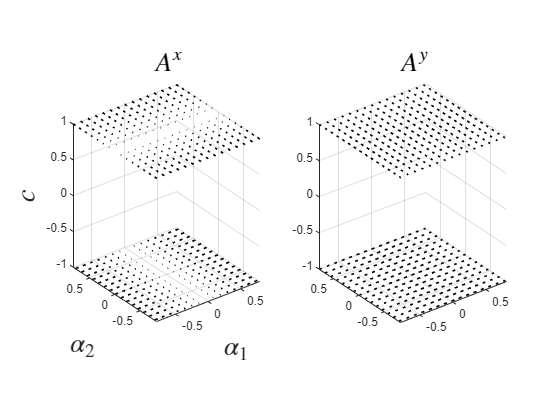

% Let the legs have a 90deg swing range centered about 0
ank = pi/4;

% Define the colors for each contact mode:
circ1 = [215,25,28]*(1/255); 
circ2 = [96,0,220]*(1/255);
circ3 = [44,123,182]*(1/255);

% The 3D shape-space is discretized equally
numD = 15; % if you change individual spacing it will break

% Let's also introduce a contact variable c and stack the vector fields on
% top of each other:
c = linspace(-1,1,numD);

% Discretize the continuous shapes and meshgrid
am = linspace(-ank,ank,numD); ap = am;
[am,ap,c] = meshgrid(am,ap,c); am = reshape(am,1,numel(am)); ap = reshape(ap,1,numel(ap));
c = reshape(c,1,numel(c));

%%% UNCOMMENT TO OBTAIN THE VECTOR FIELDS SEPARATELY
% X1U = @(r,a_1,a_2) -r.*sin(a_1);
% X1V = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% Y1U = @(r,a_1,a_2) r.*cos(a_1);
% Y1V = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% X2U = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% X2V = @(r,a_1,a_2) r.*sin(a_2);
% Y2U = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% Y2V = @(r,a_1,a_2) -r.*cos(a_2);
% x1u = X1U(1,a1,a2); x1v = X1V(1,a1,a2); y1u = Y1U(1,a1,a2); y1v = Y1V(1,a1,a2);
% x2u = X2U(1,a1,a2); x2v = X2V(1,a1,a2); y2u = Y2U(1,a1,a2); y2v = Y2V(1,a1,a2);

% figure()
% subplot(2,2,1) % x vector field of A1
% quiver(a1,a2,x1u,x1v,'k','LineWidth',1.2);
% axis equal tight;
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% title('$A_1^x$','Interpreter','latex',FontSize=20);
% 
% subplot(2,2,3) % y vector field of A1
% quiver(a1,a2,y1u,y1v,'k','LineWidth',1.2);
% axis equal tight;
% title('$A_1^y$','Interpreter','latex',FontSize=20);
% 
% subplot(2,2,2) % x vector field of A2
% quiver(a1,a2,x2u,x2v,'k','LineWidth',1.2);
% axis equal tight;
% title('$A_2^x$','Interpreter','latex',FontSize=20);
% 
% subplot(2,2,4) % y vector field of A2
% quiver(a1,a2,y2u,y2v,'k','LineWidth',1.2);
% axis equal tight;
% title('$A_2^y$','Interpreter','latex',FontSize=20);

% At c=-1 is the first vector field and c=1 is the second vector field
XU = @(r,a_1,a_2,c) -r.*sin(a_1).*(c==-1) + 0.*r.*a_1.*a_2.*(c==1);
XV = @(r,a_1,a_2,c) 0.*r.*a_1.*a_2.*(c==-1) - r.*sin(pi + a_2).*(c==1);
YU = @(r,a_1,a_2,c) r.*cos(a_1).*(c==-1) + 0.*r.*a_1.*a_2.*(c==1);
YV = @(r,a_1,a_2,c) 0.*r.*a_1.*a_2.*(c==-1) + r.*cos(pi + a_2).*(c==1);

xu_1 = XU(1,am,ap,c); xv_2 = XV(1,am,ap,c); xw_3 = zeros(size(xv_2));
yu = YU(1,am,ap,c); yv = YV(1,am,ap,c); yw = zeros(size(yv));

figure()

subplot(1,2,1)
quiver3(am,ap,c,xu_1,xv_2,xw_3,'k','LineWidth',1.2);
axis equal tight;
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$c$','Interpreter','latex',FontSize=20);
title('$A^x$','Interpreter','latex',FontSize=20);

subplot(1,2,2)
quiver3(am,ap,c,yu,yv,yw,'k','LineWidth',1.2);
axis equal tight;
title('$A^y$','Interpreter','latex',FontSize=20);

Next, we shall draw the gait and try to highlight the vector field along the shape-space traverse by the gait; for the sake of simplicity, we consider a gait where equal time is spent between switching and swinging for all legs and contact states considered. Recall that the 

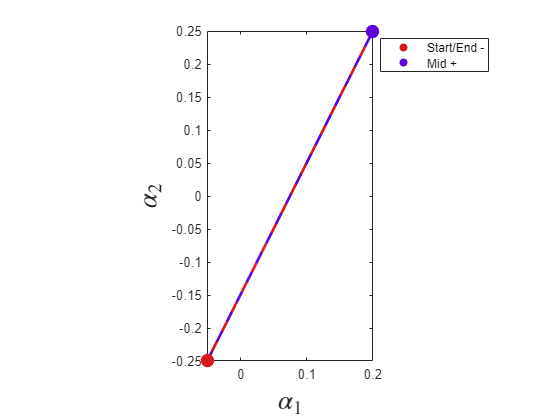

% Now, we can construct arbitrary gaits and run the approximation -- just
% panel 12
temp = [-0.051, 0.20;
   -0.25, 0.25]; % randomized -- (rand(2,2) - 0.5)*ank
phi_0 = temp(:,1); phi_m = temp(:,2);

% Plot the gait in the shape-space of the system
figure()
p1 = plot(temp(1,:),temp(2,:),'LineStyle','-','Color',circ1,'LineWidth',2);
set(get(get(p1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
hold on;
p2 = plot(temp(1,:),temp(2,:),'LineStyle','--','Color',circ2,'LineWidth',2);
set(get(get(p2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
scatter(phi_0(1),phi_0(2),100,circ1,'filled','DisplayName','Start/End -'); % color matches the first half of the gait
scatter(phi_m(1),phi_m(2),100,circ2,'filled','DisplayName','Mid +'); % midway point for second half
axis equal tight; legend('location','best');
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);

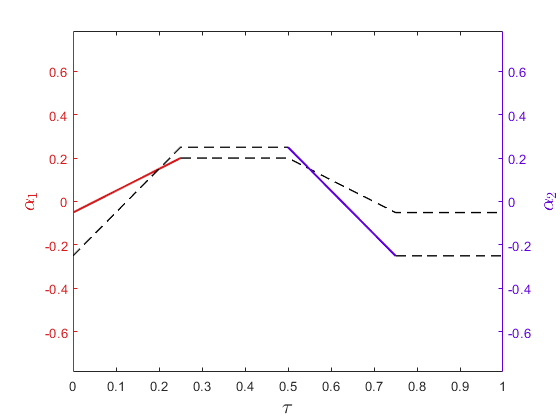

% Number of points to display the vector field for the contact stroke (spans tau for 0.25)
numV = 7;

% Shape change in each direction for the chosen gait
quartg_temp = linspace(phi_0(1),phi_m(1),numV); quartg_temp = quartg_temp(:);
phi_1 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];
quartg_temp = linspace(phi_0(2),phi_m(2),numV); quartg_temp = quartg_temp(:);
phi_2 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];

% Create a time period vector
tau = linspace(0,1,length(phi_1));

% Define the contact state over the gait first
phi_c = zeros(size(tau)); phi_c(tau < 0.25) = -1; 
phi_c(tau >= 0.25 & tau < 0.5) = linspace(-1,1,numel(tau(tau >= 0.25 & tau < 0.5)));
phi_c(tau >= 0.5 & tau < 0.75) = 1; 
phi_c(tau >= 0.75) = linspace(1,-1,numel(tau(tau >= 0.75)));

% Plot the gait as a function of the time-period
figure()
yyaxis left
plot(tau(tau<=0.25), phi_1(tau<=0.25), 'Color', circ1, 'LineStyle', '-', 'LineWidth', 1.5);
hold on;
plot(tau(tau>=0.25), phi_1(tau>=0.25), 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.0);
ylim([-ank, ank]);
% axis tight;
ylabel('$\alpha_1$','Interpreter','latex','FontSize',15,'Color',circ1);
set(gca,'YColor',circ1);

xlabel('$\tau$','Interpreter','latex','FontSize',15);

yyaxis right
plot(tau(tau<=0.5), phi_2(tau<=0.5), 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.0);
hold on;
plot(tau(tau>=0.75), phi_2(tau>=0.75), 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.0);
plot(tau(tau>=0.5 & tau<=0.75), phi_2(tau>=0.5 & tau<=0.75), 'Color', circ2, 'LineStyle', '-', 'LineWidth', 1.5);
ylim([-ank, ank]);
% axis tight;
ylabel('$\alpha_2$','Interpreter','latex','FontSize',15,'Color',circ2);
set(gca,'YColor',circ2);

The contact states are highlighted in their respective colors -- in a contact state, only the leg in contact's shape change matters.

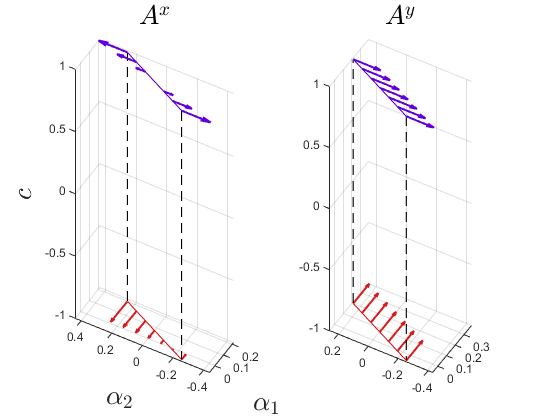

% % Buff percentage and line width for the plotting window:
% buff = 10;
% % Get the limits in each continuous shape axis for plot positioning
% lim1_L = min([phi_0(1),phi_m(1)]); lim1_H = max([phi_0(1),phi_m(1)]); range1 = buff*(lim1_H-lim1_L)/100;
% lim2_L = min([phi_0(2),phi_m(2)]); lim2_H = max([phi_0(2),phi_m(2)]);

qW = 1.5; linW = 0.8;

% Indices to distinguish each vector field
idx1 = (tau <= 0.25); idx2 = (tau >= 0.5 & tau <= 0.75); idxU = (tau>=0.25 & tau<=0.5); idxD = (tau>=0.75 & tau<=1);

% Compute the vector field:
xu_2phi = XU(1,phi_1,phi_2,phi_c); xv_2phi = XV(1,phi_1,phi_2,phi_c); xz_2phi = zeros(size(xv_2phi));
yu_2phi = YU(1,phi_1,phi_2,phi_c); yv_2phi = YV(1,phi_1,phi_2,phi_c); yz_2phi = zeros(size(yv_2phi));

% Now, plot in 3D shape-space:
figure()

azi = -60; elev = 45;

subplot(1,2,1)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),xu_2phi(idx1),xv_2phi(idx1),xz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),xu_2phi(idx2),xv_2phi(idx2),xz_2phi(idx2),'Color',circ2,'LineWidth',qW);
% quiver3(phi_1(~idx1 & ~idx2),phi_2(~idx1 & ~idx2),phi_c(~idx1 & ~idx2)...
%     ,xu_2phi(~idx1 & ~idx2),xv_2phi(~idx1 & ~idx2),xz_2phi(~idx1 & ~idx2),'k','LineWidth',1.2);
% Now plot the lines:
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$c$','Interpreter','latex',FontSize=20);
title('$A^x$','Interpreter','latex',FontSize=20);

subplot(1,2,2)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),yu_2phi(idx1),yv_2phi(idx1),yz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),yu_2phi(idx2),yv_2phi(idx2),yz_2phi(idx2),'Color',circ2,'LineWidth',qW);
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
% quiver3(phi_1(~idx1 & ~idx2),phi_2(~idx1 & ~idx2),phi_c(~idx1 & ~idx2)...
%     ,yu_2phi(~idx1 & ~idx2),yv_2phi(~idx1 & ~idx2),yz_2phi(~idx1 & ~idx2),'k','LineWidth',1.2);
title('$A^y$','Interpreter','latex',FontSize=20);

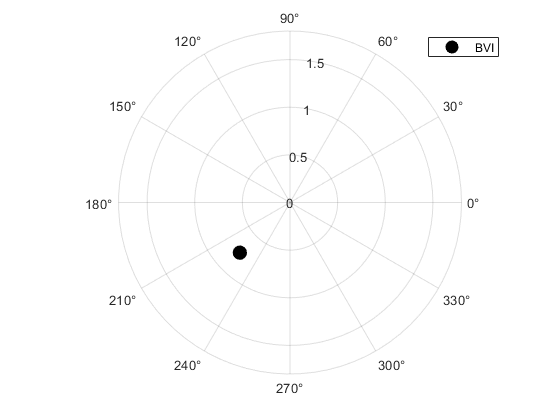

% Let's estimate the displacement through the boundary integral
z_phi_BVI = double(-int(subs(A_1,r,1)*[1; 0], alpha_1, [phi_0(1) phi_m(1)]) -int(subs(A_2,r,1)*[0; 1], alpha_2, [phi_m(2) phi_0(2)]));

% Let's plot this as a phasor:
figure()
polarplot(atan2(z_phi_BVI(2),z_phi_BVI(2)),norm(z_phi_BVI),...
    'ko','MarkerSize',10,'MarkerFaceColor','k','DisplayName','BVI');
legend('Location','best');

Now, we shall plot the switching flux and plot it in the system's shape space **<CHECK NOTES "SINGLE DISK DECOUPLED" FOR ANALYTICAL RESULTS>**. Let's compute the line equation to collapse to the flux face for the given discrete gait.

lineQ = null([temp',  ones(2,1)])

lineQ =     0.8917
   -0.4477
   -0.0664


% Let's introduce the line equation with symbol alpha
syms a b c alpha real % a, b, and c belong to the line equation

% Use the analytical result and substitute the line equation parameters
flux_slice = a/b*[sin(a/b*alpha + c/b); cos(a/b*alpha + c/b)] - [-sin(alpha); cos(alpha)];
flux_slice = subs(flux_slice, [a, b, c], [lineQ(1), lineQ(2), lineQ(3)])

$$flux\_slice = \left(\begin{array}{c} \frac{8032050041201797\,\sin\left(\frac{8032050041201797\,\alpha }{4032089120683304}-\frac{2393550912278135}{16128356482733216}\right)}{4032089120683304}+\sin\left(\alpha \right)\\ -\frac{8032050041201797\,\cos\left(\frac{8032050041201797\,\alpha }{4032089120683304}-\frac{2393550912278135}{16128356482733216}\right)}{4032089120683304}-\cos\left(\alpha \right) \end{array}\right)$$

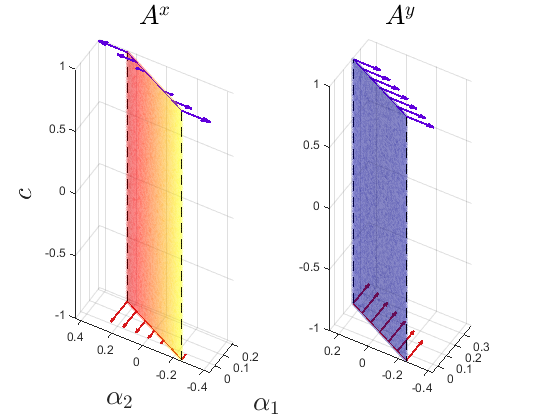

% Convert this into a matlab function
fluxS_X = matlabFunction(flux_slice(1), 'Vars', alpha);
fluxS_Y = matlabFunction(flux_slice(2), 'Vars', alpha);

% Get the switching flux surface parameterized
[A2_fS, C_fS] = meshgrid(linspace(phi_0(2),phi_m(2)),linspace(-1,1));
A1_fS = -lineQ(2)/lineQ(1).*A2_fS -lineQ(3)/lineQ(1);
A1_fS = A1_fS(:); A2_fS = A2_fS(:); C_fS = C_fS(:);

% Compute the slices for each alpha_1 value (or alpha_2 based of b == 0)
fS_X = fluxS_X(A1_fS); fS_Y = fluxS_Y(A1_fS);
fS_X = fS_X(:); fS_Y = fS_Y(:);

% Get the maximum and minimum values for the colorbar:
maxC = max([ceil(max(fS_X,[],'all')), ceil(max(fS_Y,[],'all'))],[],'all');
minC = min([floor(min(fS_X,[],'all')), floor(min(fS_Y,[],'all'))],[],'all');

% Now, plot in 3D shape-space:
figure()

azi = -60; elev = 45;

subplot(1,2,1)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),xu_2phi(idx1),xv_2phi(idx1),xz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),xu_2phi(idx2),xv_2phi(idx2),xz_2phi(idx2),'Color',circ2,'LineWidth',qW);
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$c$','Interpreter','latex',FontSize=20);
title('$A^x$','Interpreter','latex',FontSize=20);
% Plot the switching flux using scatter3
scatter3(A1_fS,A2_fS,C_fS,10,fS_X,'filled','MarkerFaceAlpha',0.1,'MarkerEdgeColor','none','Marker','o'); %
colormap(jet); clim([minC maxC]); % colorbar('ylim',[minC maxC]); 

subplot(1,2,2)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),yu_2phi(idx1),yv_2phi(idx1),yz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),yu_2phi(idx2),yv_2phi(idx2),yz_2phi(idx2),'Color',circ2,'LineWidth',qW);
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
title('$A^y$','Interpreter','latex',FontSize=20);
scatter3(A1_fS,A2_fS,C_fS,10,fS_Y,'filled','MarkerFaceAlpha',0.1,'MarkerEdgeColor','none','Marker','o'); %
colormap(jet); clim([minC maxC]); % colorbar('ylim',[minC maxC]);

% 
% subplot(1,3,3)
% colormap(jet); sP = colorbar('ylim',[minC maxC],'Position',[0.1,0.1,0.1,0.1]); 
% set(gca,'Visible','off');

Let's figure out the displacement with the Stokes' approximation.

z_phi_sFI = double(int(flux_slice, alpha, [phi_1(1) phi_m(1)]));

Closely matches our BVI as shown below!

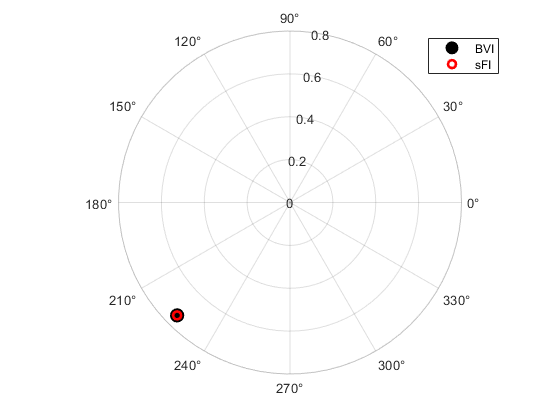

figure()
polarplot(atan2(z_phi_BVI(2),z_phi_BVI(2)),norm(z_phi_BVI),...
    'ko','MarkerSize',10,'MarkerFaceColor','k','DisplayName','BVI');
hold on;
polarplot(atan2(z_phi_sFI(2),z_phi_sFI(2)),norm(z_phi_sFI),...
    'ro','LineWidth',2,'MarkerFaceColor','none','DisplayName','sFI');
legend('Location','best');

Alright, now we can finally animate the system with its trajectory per gait cycle shown.

## Animation (without fanimator)

% Let's increase the resolution on our gait time-series (this needs to be improved on!!)
numV = 25;
quartg_temp = linspace(phi_0(1),phi_m(1),numV); quartg_temp = quartg_temp(:);
phi_1 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];
quartg_temp = linspace(phi_0(2),phi_m(2),numV); quartg_temp = quartg_temp(:);
phi_2 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];
tau = linspace(0,1,length(phi_1));
phi_c = zeros(size(tau)); phi_c(tau < 0.25) = -1; 
phi_c(tau >= 0.25 & tau < 0.5) = linspace(-1,1,numel(tau(tau >= 0.25 & tau < 0.5)));
phi_c(tau >= 0.5 & tau < 0.75) = 1; 
phi_c(tau >= 0.75) = linspace(1,-1,numel(tau(tau >= 0.75)));

% We shall use fanimator for this section -- this will be the boundary
% integral method.
syms x y theta

% This method uses a constant fixed time to switch between legs and the
% same time to swing the legs.

% Let's obtain some indices that will be useful later on:
idx1 = (tau == 0.25);
idx2s = (tau == 0.5);
idx2 = (tau == 0.75);

% Leg resting position vector length:
lr = 0.5;

% Compute the leg-tip positions and leg-base positions LOCALLY
leg_1 = matlabFunction(subs(r*[cos(alpha_1); sin(alpha_1)],r,1), 'Vars', alpha_1);
leg_2 = matlabFunction(subs(-r*[cos(alpha_2); sin(alpha_2)],r,1), 'Vars', alpha_2);
leg_1r = double(subs(r*[cos(alpha_1); sin(alpha_1)],[r, alpha_1],[lr, 0])); % direction when each leg is unactuated (leg resting position)
leg_2r = double(subs(-r*[cos(alpha_2); sin(alpha_2)],[r, alpha_2],[lr, 0])); 

% Get the COM location and leg locations defined above as a function of time:
Xcm = zeros(size(tau)); Ycm = Xcm;
L1_x = Xcm; L2_x = L1_x; L1_y = L2_x; L2_y = L1_y;
L1r_x = Xcm; L2r_x = L1r_x; L1r_y = L2r_x; L2r_y = L1r_y;

for i = 1:numel(Xcm)

    % COMPUTE COM:
    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    if (tau(i) < 0.25) % contact state 1
        
        % Compute the system translation:
        Xcm(i) = -double(int(subs(A_1(1,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));
        Ycm(i) = -double(int(subs(A_1(2,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));

    elseif (tau(i) >= 0.25) && (tau(i) < 0.50) % switching

        % Compute the translations at the end of the first contact phase:
        if tau(i) == 0.25
            Xcm(i) = -double(int(subs(A_1(1,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));
            Ycm(i) = -double(int(subs(A_1(2,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));
        else
            % Substitute the computation at the end of the first contact phase
            Xcm(i) = Xcm(idx1);
            Ycm(i) = Ycm(idx1);
        end

    elseif (tau(i) >= 0.50) && (tau(i) < 0.75) % contact state 2

        Xcm(i) = Xcm(idx1) + -double(int(subs(A_2(1,2),r,1), alpha_2, [phi_1(idx2s) phi_1(i)]));
        Ycm(i) = Ycm(idx1) + -double(int(subs(A_2(2,2),r,1), alpha_2, [phi_2(idx2s) phi_2(i)]));

    else % switching
        
        if tau(i) == 0.75
            Xcm(i) = Xcm(idx1) + -double(int(subs(A_2(1,2),r,1), alpha_2, [phi_1(idx2s) phi_1(i)]));
            Ycm(i) = Ycm(idx1) + -double(int(subs(A_2(2,2),r,1), alpha_2, [phi_2(idx2s) phi_2(i)]));
        else
            Xcm(i) = Xcm(idx2);
            Ycm(i) = Ycm(idx2);
        end

    end
    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    % COMPUTE THE LEG POSITIONS GLOBALLY
    
    L1_x(i) = Xcm(i) + [1,0]*leg_1(phi_1(i));
    L1_y(i) = Ycm(i) + [0,1]*leg_1(phi_1(i));
    L2_x(i) = Xcm(i) + [1,0]*leg_2(phi_2(i));
    L2_y(i) = Ycm(i) + [0,1]*leg_2(phi_2(i));

    L1r_x(i) = Xcm(i) + [1,0]*leg_1r;
    L1r_y(i) = Ycm(i) + [0,1]*leg_1r;
    L2r_x(i) = Xcm(i) + [1,0]*leg_2r;
    L2r_y(i) = Ycm(i) + [0,1]*leg_2r;

end

Now, we have all values computed for plotting:

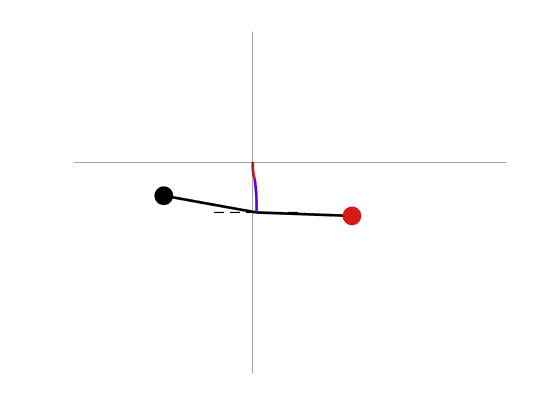

% Get the plot parameters
lW = 2; lW_r = 0.8; circS = 200;
lW_O = 0.5; alp_O = 0.2;
lW_traj = 2;
legL = 1; mulL = 3;

% Get the figure limit
limX = [min(Xcm,[],'all') - mulL*legL, max(Xcm,[],'all') + mulL*legL]; % add the leg length on either side
limY = [min(Ycm,[],'all') - mulL*legL, max(Ycm,[],'all') + mulL*legL];

% Plot the results in a loop
figure()
for i = 1:numel(tau)
    
    % If it is not the final frame, clear it:
    if i ~= numel(tau)
        clf;
    end

    % Plot the legs 
    plot([Xcm(i) L1_x(i)], [Ycm(i) L1_y(i)], 'k', 'LineWidth', lW);
    hold on; set(gca, 'visible', 'off');
    plot([Xcm(i) L2_x(i)], [Ycm(i) L2_y(i)], 'k', 'LineWidth', lW);

    % Plot the origin with thin gray lines
    xline(0,'k','LineWidth',lW_O,'Alpha',0.2); yline(0,'k','LineWidth',lW_O,'Alpha',alp_O);

    % Compute and plot the trajectory:
%     % This method works, but has its bugs since jumps happen when you
%     % transition from one region to another.
    Xcm_temp = Xcm(1:i); Ycm_temp = Ycm(1:i);
%     Xcm_1 = Xcm_temp(phi_c(1:i) == -1); Xcm_2 = Xcm_temp(phi_c(1:i) == 1);
%     Ycm_1 = Ycm_temp(phi_c(1:i) == -1); Ycm_2 = Ycm_temp(phi_c(1:i) == 1);
%     plot(Xcm_1, Ycm_1, 'Color', circ1, 'LineWidth', lW_traj);
%     plot(Xcm_2, Ycm_2, 'Color', circ2, 'LineWidth', lW_traj);
% 
%     % This is the constant color method that will when trajectory color
%     is supplied.
%     plot(Xcm(1:i), Ycm(1:i), 'g', 'LineWidth', lW_traj); % old method

    % This method based on time should fix the issue -- there are only two
    % motion phases (cumulatively adds up) -- this is not an extendable
    % when talking about larger scale locomotion phases.
    if tau(i) <= 0.25
        plot(Xcm_temp, Ycm_temp, 'Color', circ1, 'LineWidth', lW_traj);
    elseif tau(i) >= 0.25 && tau(i) <= 0.5
        plot(Xcm_temp, Ycm_temp, 'Color', circ1, 'LineWidth', lW_traj);
    elseif tau(i) >= 0.5 && tau(i) <= 0.75
        plot(Xcm_temp(tau<=0.25), Ycm_temp(tau<=0.25), 'Color', circ1, 'LineWidth', lW_traj);
        plot(Xcm_temp(tau >= 0.5 & tau<=tau(i)), Ycm_temp(tau >= 0.5 & tau<=tau(i)), 'Color', circ2, 'LineWidth', lW_traj);
    else
        plot(Xcm_temp(tau<=0.25), Ycm_temp(tau<=0.25), 'Color', circ1, 'LineWidth', lW_traj);
        plot(Xcm_temp(tau >= 0.5 & tau <= 0.75), Ycm_temp(tau >= 0.5 & tau <= 0.75), 'Color', circ2, 'LineWidth', lW_traj);
    end
    
    % Plot the leg resting positions
    plot([Xcm(i) L1r_x(i)], [Ycm(i) L1r_y(i)], 'k--', 'LineWidth', lW_r);
    plot([Xcm(i) L2r_x(i)], [Ycm(i) L2r_y(i)], 'k--', 'LineWidth', lW_r);

    % Scatter circle to the leg tips
    scatter(L1_x(i), L1_y(i), circS, interp1([-1,1],[circ1; 0,0,0],phi_c(i)),'filled'); % interpolate between the legs color and black
    scatter(L2_x(i), L2_y(i), circS, interp1([-1,1],[0,0,0; circ2],phi_c(i)),'filled');

    % Set the figure limits:
    xlim(limX); ylim(limY);
    
    % Output the plot:
    drawnow();
end

%%%% TEXT TITLE 1: Animation with fanimator
% % Let's start by calling some variables we didn't have last time. These
% % include the time taken to swing the foot at a given rate and the time
% % take to switch the pin condition from one foot to another.
% T_alpha = 0.5; T_switch = 0.5; % these values are in units of time
% 
% % Compute the total time period T
% T = 2*(T_alpha + T_switch);
% 
% % Let's adopt the convention that the first phase will be in the first
% % vector field and then the second phase will be in the second vector
% % field -- we can break this when we are in the gait coordinates.
% vec_ord = false; % this is the default -- vec_1 and then followed by vec_2
% 
% % Let's generate the time vector -- assume we are generating over 5
% % gait-cycles (this way we can make sure T~=1 is handled properly and our
% % integration works out in fanimator)

The natural next step is, how does this extend to a similar three-legged system?

%%%% TEXT: Considering the difference between the vector fields for infinitesimal discrete gaits, we can draw a heat-map that signifies the maximum displacement and plots it out for us. <CHECK NOTES: Compliant Bodied Legged Systems/GM theory/2-legged Single Disk>
% % We need to compute a simplification for finding the average displacement
% % to a orientation independent infinitesimal loop
% syms epsilon alpha theta real
% intg = (1/epsilon)*[-cos(alpha_1 + alpha*epsilon*cos(theta))/cos(theta) + cos(alpha_2 + alpha*epsilon*sin(theta))/sin(theta);
%                     -sin(alpha_1 + alpha*epsilon*cos(theta))/cos(theta) + sin(alpha_2 + alpha*epsilon*sin(theta))/sin(theta)]
% temp = subs(intg,alpha,1) - subs(intg,alpha,-1); 
% intg = simplify(temp,'Steps',50)
% intg = limit(intg,epsilon,0)
%%%% TEXT: Works out to 2( A_2^{(2)}) - A_1^{(1)}) ) as expected for a positive infinitesimal discrete gait! The superscripts denote the corresponding columns involved in the operation. Let's compute this and plot it as a heatmap for each for displacement in X and Y respectively.
% % Let's plot the heatmap - use a 2D discretization (`_2' respresents that)
% a1_2 = reshape(a1(c == -1),numD,numD); a2_2 = reshape(a2(c == -1),numD,numD);
% 
% % Heat
% Xdisp = 2*reshape(xv_2(c == 1) - xu_1(c == -1),numD,numD); Ydisp = 2*reshape(yv(c == 1) - yu(c == -1),numD,numD);
% 
% % Let's get the color limits:
% maxL = max([max(Xdisp,[],'all'), max(Ydisp,[],'all')]);
% minL = min([min(Xdisp,[],'all'), min(Ydisp,[],'all')]);
% 
% % Plot the results:
% figure()
% 
% subplot(1,2,1)
% surf(a1_2,a2_2,Xdisp,'EdgeColor','none'); 
% view(2);
% axis equal tight;
% colormap(jet); 
% colorbar('ylim',[round(min(Xdisp,[],'all')), round(max(Xdisp,[],'all'))]);
% caxis([minL maxL]);
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{12}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(1,2,2)
% surf(a1_2,a2_2,Ydisp,'EdgeColor','none');
% view(2);
% axis equal tight;
% colormap(jet); 
% colorbar('ylim',[round(min(Ydisp,[],'all')), round(max(Ydisp,[],'all'))]); 
% caxis([minL maxL]);
% title('$dz_{\{\phi_{12}\}}^{y}$','Interpreter','latex',FontSize=20)
%%%% TEXT: Now, we can superimpose this as a slight transparent vector
%%%% cloud onto our disjointed vector field to give a sense of how to draw
%%%% these discrete gaits. 
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % NOT REQUIRED!!!!!!!!!!!!!
% % Create the 3D version of the heatmap:
% Xdisp_3 = reshape(repmat(Xdisp,1,1,numD),1,numel(Xdisp)*numD); Ydisp_3 = reshape(repmat(Ydisp,1,1,numD),1,numel(Ydisp)*numD);
% 
% % Plot the vector field again:
% figure()
% 
% h1 = subplot(1,2,1);
% quiver3(a1,a2,c,xu,xv,xz,'k','LineWidth',1.2);
% axis equal tight; hold on;
% scatter3(a1,a2,c,100,Xdisp_3,'filled','MarkerFaceAlpha',0.2,'MarkerEdgeColor','none','Marker','o');
% colormap(jet); 
% % colorbar('peer',h1,'east','Location','eastoutside'); 
% caxis([minL maxL]);
% % xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% % ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% zlabel('$c$','Interpreter','latex',FontSize=20);
% title('$A^x$','Interpreter','latex',FontSize=20);
% 
% h2 = subplot(1,2,2);
% quiver3(a1,a2,c,yu,yv,yz,'k','LineWidth',1.2);
% axis equal tight; hold on;
% scatter3(a1,a2,c,100,Ydisp_3,'filled','MarkerFaceAlpha',0.2,'MarkerEdgeColor','none','Marker','o');
% colormap(jet); 
% % colorbar('peer',h2,'east','Location','eastoutside'); 
% caxis([minL maxL]);
% title('$A^y$','Interpreter','latex',FontSize=20);

## Three-legged system

Since it is a single-disk system, let's evenly distribute the legs around a circle.

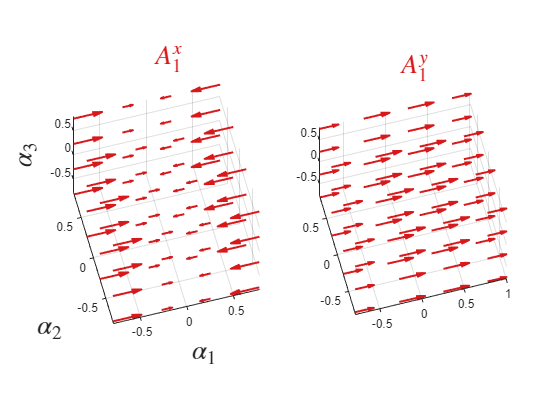

% Number of legs:
numL = 3;

% Leg angle offset from each other:
off = mean(diff(linspace(0,2*pi,numL+1)));

% Let the legs have a 90deg swing range centered about 0
ank = pi/4;

% The 3D shape-space is discretized equally
numD = 4; % if you change individual spacing it will break

% Let the leg length be 1 unit:
r = 1;

% Discretize the continuous shapes and meshgrid
am = linspace(-ank,ank,numD); ap = am; a3 = am;
[am,ap,a3] = meshgrid(am,ap,a3);
am = reshape(am,1,numel(am)); ap = reshape(ap,1,numel(ap)); a3 = reshape(a3,1,numel(a3));

% Directly define the vector field
XU_1 = @(r,a_1,a_2,a_3) -r.*sin(0*off*ones(size(a_2)) + a_1) + 0.*r.*a_1.*a_2.*a_3;
XV_2 = @(r,a_1,a_2,a_3) - r.*sin(1*off*ones(size(a_2)) + a_2) + 0.*r.*a_1.*a_2.*a_3;
XW_3 = @(r,a_1,a_2,a_3) - r.*sin(2*off*ones(size(a_2)) + a_3) + 0.*r.*a_1.*a_2.*a_3;

YU_1 = @(r,a_1,a_2,a_3) r.*cos(0*off*ones(size(a_2)) + a_1) + 0.*r.*a_1.*a_2.*a_3;
YV_2 = @(r,a_1,a_2,a_3) r.*cos(1*off*ones(size(a_2)) + a_2) + 0.*r.*a_1.*a_2.*a_3;
YW_3 = @(r,a_1,a_2,a_3) r.*cos(2*off*ones(size(a_2)) + a_3) + 0.*r.*a_1.*a_2.*a_3;

% Get the data:
xu_1 = XU_1(r,am,ap,a3); xv_2 = XV_2(r,am,ap,a3); xw_3 = XW_3(r,am,ap,a3);
yu_1 = YU_1(r,am,ap,a3); yv_2 = YV_2(r,am,ap,a3); yw_3 = YW_3(r,am,ap,a3);

% Vector field line thickness:
qW = 1.5;

% Define the colors for each contact mode:
circ1 = [215,25,28]*(1/255); 
circ3 = [44,123,182]*(1/255);
circ2 = [96,0,220]*(1/255);

% PLOT THE VECTOR FIELDS
figure()

% in degs
azi_1 = -15; elv_1 = 60;

subplot(1,2,1)
quiver3(am,ap,a3,xu_1,zeros(size(xu_1)),zeros(size(xu_1)),'Color',circ1,'LineWidth',qW);
axis equal tight; view(azi_1,elv_1);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$\alpha_3$','Interpreter','latex',FontSize=20);
title('$A_1^x$','Interpreter','latex','Color',circ1,FontSize=20);

subplot(1,2,2)
quiver3(am,ap,a3,yu_1,zeros(size(yu_1)),zeros(size(yu_1)),'Color',circ1,'LineWidth',qW);
axis equal tight; view(azi_1,elv_1);
title('$A_1^y$','Interpreter','latex','Color',circ1,FontSize=20);

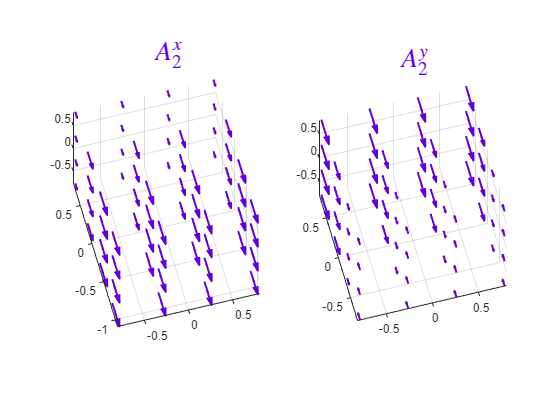

% in degs
azi_2 = -15; elv_2 = 60;

figure()

subplot(1,2,1)
quiver3(am,ap,a3,zeros(size(xv_2)),xv_2,zeros(size(xv_2)),'Color',circ2,'LineWidth',qW);
axis equal tight; view(azi_2,elv_2);
title('$A_2^x$','Interpreter','latex','Color',circ2,FontSize=20);

subplot(1,2,2)
quiver3(am,ap,a3,zeros(size(yv_2)),yv_2,zeros(size(yv_2)),'Color',circ2,'LineWidth',qW);
axis equal tight; view(azi_2,elv_2);
title('$A_2^y$','Interpreter','latex','Color',circ2,FontSize=20);

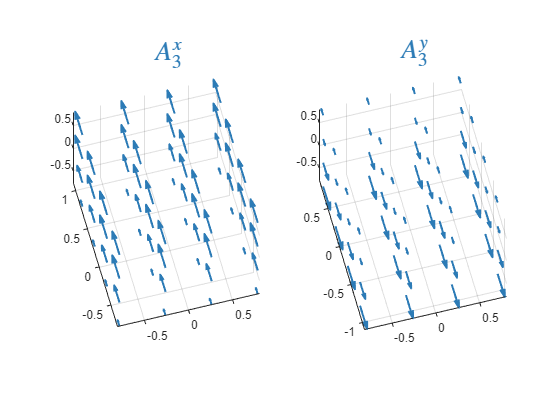

% in degs
azi_3 = -15; elv_3 = 60;

figure()

subplot(1,2,1)
quiver3(am,ap,a3,zeros(size(xw_3)),xw_3,zeros(size(xw_3)),'Color',circ3,'LineWidth',qW);
axis equal tight; view(azi_3,elv_3);
title('$A_3^x$','Interpreter','latex','Color',circ3,FontSize=20);

subplot(1,2,2)
quiver3(am,ap,a3,zeros(size(yw_3)),yw_3,zeros(size(yw_3)),'Color',circ3,'LineWidth',qW);
axis equal tight; view(azi_3,elv_3);
title('$A_3^y$','Interpreter','latex','Color',circ3,FontSize=20);

% %%%% TEXT: Now, we can take the difference to obtain the infinitesimal displacement heat-maps.
% % Get the data for a different discretization:
% numD = 15;
% a1 = linspace(-ank,ank,numD); a2 = a1; a3 = a1;
% [a1,a2,a3] = meshgrid(a1,a2,a3);
% a1 = reshape(a1,1,numel(a1)); a2 = reshape(a2,1,numel(a2)); a3 = reshape(a3,1,numel(a3));
% xu_1 = XU_1(r,a1,a2,a3); xv_2 = XV_2(r,a1,a2,a3); xw_3 = XW_3(r,a1,a2,a3);
% yu_1 = YU_1(r,a1,a2,a3); yv_2 = YV_2(r,a1,a2,a3); yw_3 = YW_3(r,a1,a2,a3);
% 
% % Get the indicies for each plot
% idx12 = a3 == ank; idx13 = a2 == ank; idx23 = a1 == ank;
% % Shape-space 3D
% a1_12 = reshape(a1(idx12),numD,numD); a2_12 = reshape(a2(idx12),numD,numD);
% a2_23 = reshape(a2(idx23),numD,numD); a3_23 = reshape(a3(idx23),numD,numD);
% a1_13 = reshape(a1(idx13),numD,numD); a3_13 = reshape(a3(idx13),numD,numD);
% 
% % Heat-Map 3D
% Xdisp_12 = 2*reshape(xv_2(idx12) - xu_1(idx12),numD,numD); 
% Ydisp_12 = 2*reshape(yv_2(idx12) - yu_1(idx12),numD,numD);
% 
% Xdisp_23 = 2*reshape(xv_2(idx23) - xu_1(idx23),numD,numD); 
% Ydisp_23 = 2*reshape(yv_2(idx23) - yu_1(idx23),numD,numD);
% 
% Xdisp_13 = 2*reshape(xw_3(idx13) - xu_1(idx13),numD,numD); 
% Ydisp_13 = 2*reshape(yw_3(idx13) - yu_1(idx13),numD,numD);
% 
% % Let's get the color limits:
% maxL_12 = max([max(Xdisp_12,[],'all'), max(Ydisp_12,[],'all')]);
% minL_12 = min([min(Xdisp_12,[],'all'), min(Ydisp_12,[],'all')]);
% maxL_23 = max([max(Xdisp_23,[],'all'), max(Ydisp_23,[],'all')]);
% minL_23 = min([min(Xdisp_23,[],'all'), min(Ydisp_23,[],'all')]);
% maxL_13 = max([max(Xdisp_13,[],'all'), max(Ydisp_13,[],'all')]);
% minL_13 = min([min(Xdisp_13,[],'all'), min(Ydisp_13,[],'all')]);
% 
% % Decimal places to round off for the colorbar
% decB = 2;
% 
% % Plot the results:
% figure()
% 
% subplot(3,2,1)
% surf(a1_12,a2_12,Xdisp_12,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_12 maxL_12]);
% colorbar('ylim',[round(min(Xdisp_12,[],'all'),decB), round(max(Xdisp_12,[],'all'),decB)]);
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{12}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,2)
% surf(a1_12,a2_12,Ydisp_12,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_12 maxL_12]);
% colorbar('ylim',[round(min(Ydisp_12,[],'all'),decB), round(max(Ydisp_12,[],'all'),decB)]);
% title('$dz_{\{\phi_{12}\}}^{y}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,3)
% surf(a2_23,a3_23,Xdisp_23,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_23 maxL_23]);
% colorbar('ylim',[round(min(Xdisp_23,[],'all'),decB), round(max(Xdisp_23,[],'all'),decB)]);
% xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{23}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,4)
% surf(a2_23,a3_23,Ydisp_23,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_23 maxL_23]);
% colorbar('ylim',[round(min(Ydisp_23,[],'all'),decB), round(max(Ydisp_23,[],'all'),decB)]);
% title('$dz_{\{\phi_{23}\}}^{y}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,5)
% surf(a1_13,a3_13,Xdisp_13,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_13 maxL_13]);
% colorbar('ylim',[round(min(Xdisp_13,[],'all'),decB), round(max(Xdisp_13,[],'all'),decB)]);
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{13}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,6)
% surf(a1_13,a3_13,Ydisp_13,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_13 maxL_13]);
% colorbar('ylim',[round(min(Ydisp_13,[],'all'),decB), round(max(Ydisp_13,[],'all'),decB)]);
% title('$dz_{\{\phi_{13}\}}^{y}$','Interpreter','latex',FontSize=20);

## Extending Stokes' theorem

In this section, the focus is on extending switching flux framework to legs decoupled systems we care about. Since the system we consider is conservative, we only consider straight-line paths in each connection vector field.

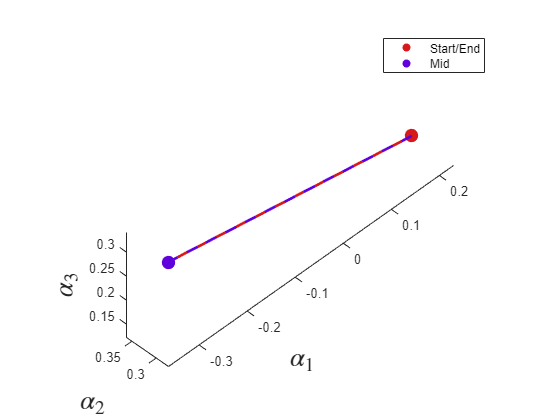

% Let's redefine the ankle limits for the three legged system:
ank = pi/4;

% Number of legs:
numL = 3;

% Define the colors for each contact mode:
circ1 = [215,25,28]*(1/255); 
circ3 = [44,123,182]*(1/255);
circ2 = [96,0,220]*(1/255);

% Leg angle offset from each other:
off = mean(diff(linspace(0,2*pi,numL+1)));

% Define each vector field for the three contact case -- the vector fields
% are irrotational and hence only translations are considered
syms r alpha_1 alpha_2 alpha_3 real

A_1 = r*[-sin(alpha_1 + off*0), 0, 0;
        cos(alpha_1 + off*0), 0, 0;
        0, 0, 0]; % added alpha_2 and alpha_3 to get the matlabFunction to work properly

A_2 = r*[0, -sin(alpha_2 + off*1), 0;
        0, cos(alpha_2 + off*1), 0;
        0, 0, 0];

A_3 = r*[0, 0, -sin(alpha_3 + off*2);
        0, 0, cos(alpha_3 + off*2);
        0, 0, 0];

% Let's create a matlab function for connection vector field:
A1f = matlabFunction(A_1,'Vars',[r alpha_1 alpha_2 alpha_3]);
A2f = matlabFunction(A_2,'Vars',[r alpha_1 alpha_2 alpha_3]);
A3f = matlabFunction(A_3,'Vars',[r alpha_1 alpha_2 alpha_3]);

% Get the analytical form of the switching flux
dz_12_x = matlabFunction(2*(A_2(1,2) - A_1(1,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);
dz_12_y = matlabFunction(2*(A_2(2,2) - A_1(2,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);

dz_23_x = matlabFunction(2*(A_3(1,3) - A_2(1,2)),'Vars',[r alpha_1 alpha_2 alpha_3]);
dz_23_y = matlabFunction(2*(A_3(2,3) - A_2(2,2)),'Vars',[r alpha_1 alpha_2 alpha_3]);

dz_13_x = matlabFunction(2*(A_3(1,3) - A_1(1,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);
dz_13_y = matlabFunction(2*(A_3(2,3) - A_1(2,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);

% Create a 3D grid of the shape space
[am,ap,a3] = meshgrid(linspace(-ank,ank),linspace(-ank,ank),linspace(-ank,ank));

% Evaluate the sf12

% Now, we can construct arbitrary gaits and run the approximation -- just
% panel 12
temp = [0.2295,   -0.3647;
        0.3609,    0.2742;
        0.1223,    0.3409]; % randomized -- (rand(3,2) - 0.5)*ank
phi_0 = temp(:,1); phi_m = temp(:,2);

% Plot the gait in the shape-space of the system
azi = -45; elv = 45;
figure()
p1 = plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','-','Color',circ1,'LineWidth',2);
set(get(get(p1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
hold on;
p2 = plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','--','Color',circ2,'LineWidth',2);
set(get(get(p2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
scatter3(phi_0(1),phi_0(2),phi_0(3),100,circ1,'filled','DisplayName','Start/End'); % color matches the first half of the gait
scatter3(phi_m(1),phi_m(2),phi_m(3),100,circ2,'filled','DisplayName','Mid'); % midway point for second half
axis equal tight; view(azi,elv); legend('location','best');
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$\alpha_3$','Interpreter','latex',FontSize=20);

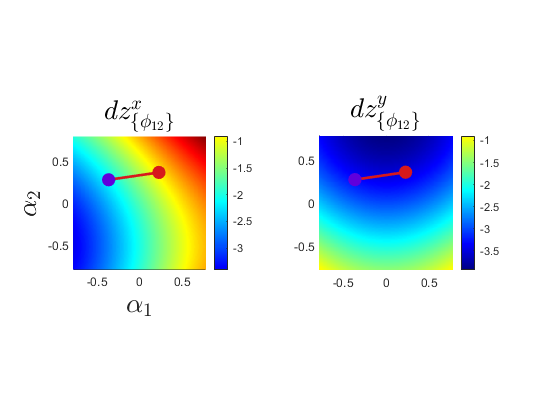

% Plot the same system in the switching flux for 12
idx12 = (a3 == ank);
maxL_12 = max([max(dz_12_x(1,am(idx12),ap(idx12),a3(idx12)),[],'all'),...
    max(dz_12_y(1,am(idx12),ap(idx12),a3(idx12)),[],'all')]);
minL_12 = min([min(dz_12_x(1,am(idx12),ap(idx12),a3(idx12)),[],'all'),...
    min(dz_12_y(1,am(idx12),ap(idx12),a3(idx12)),[],'all')]);

decB = 2;

figure()

subplot(1,2,1)
surf(reshape(am(idx12),100,100),reshape(ap(idx12),100,100),...
    reshape(dz_12_x(1,am(idx12),ap(idx12),a3(idx12)),100,100),'EdgeColor','none');
axis equal tight; hold on; view(2);
plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','-','Color',circ1,'LineWidth',2);
scatter3(phi_0(1),phi_0(2),phi_0(3),100,circ1,'filled');
scatter3(phi_m(1),phi_m(2),phi_m(3),100,circ2,'filled');
colormap(jet); caxis([minL_12 maxL_12]);
colorbar('ylim',[round(min(dz_12_x(1,am(idx12),ap(idx12),a3(idx12)),[],'all'),decB),...
    round(max(dz_12_y(1,am(idx12),ap(idx12),a3(idx12)),[],'all'),decB)]);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$dz_{\{\phi_{12}\}}^{x}$','Interpreter','latex',FontSize=20);

subplot(1,2,2)
surf(reshape(am(idx12),100,100),reshape(ap(idx12),100,100),...
    reshape(dz_12_y(1,am(idx12),ap(idx12),a3(idx12)),100,100),'EdgeColor','none');
axis equal tight; hold on; view(2);
plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','-','Color',circ1,'LineWidth',2);
scatter3(phi_0(1),phi_0(2),phi_0(3),100,circ1,'filled');
scatter3(phi_m(1),phi_m(2),phi_m(3),100,circ2,'filled');
colormap(jet); caxis([minL_12 maxL_12]);
colorbar('ylim',[round(min(dz_12_y(1,am(idx12),ap(idx12),a3(idx12)),[],'all'),decB),...
    round(max(dz_12_y(1,am(idx12),ap(idx12),a3(idx12)),[],'all'),decB)]);
title('$dz_{\{\phi_{12}\}}^{y}$','Interpreter','latex',FontSize=20);

%%%%%% TEXT: Let's now numerically compute the net displacement!
% wid = mean(diff(linspace(phi_0(1),phi_m(1))));
% dz_12_xN = dz_12_x(1,linspace(phi_0(1,1),phi_m(1,1)),linspace(phi_0(2,1),phi_m(2,1)),linspace(phi_0(3,1),phi_m(3,1)));
% dz_12_yN = dz_12_y(1,linspace(phi_0(1,1),phi_m(1,1)),linspace(phi_0(2,1),phi_m(2,1)),linspace(phi_0(3,1),phi_m(3,1)));
% zx_12num = sum(dz_12_xN.*(wid*[ones(size(dz_12_xN))])) - wid*dz_12_xN(end)
% zy_12num = sum(dz_12_yN.*(wid*[ones(size(dz_12_yN))])) - wid*dz_12_yN(end)
% z_12num = [zx_12num; zy_12num] % Just stack the translations in each direction

Let's now do the symbolic integration to obtain the displacement!

sdz_12 = 2*(A_2(:,2) - A_1(:,1))

$$sdz\_12 = \left(\begin{array}{c} 2\,r\,\sin\left(\alpha_{1}\right)-2\,r\,\sin\left(\alpha_{2}+\frac{2\,\pi }{3}\right)\\ 2\,r\,\cos\left(\alpha_{2}+\frac{2\,\pi }{3}\right)-2\,r\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

syms alpha real
if (abs(mod(atan2(phi_m(2)-phi_0(2),phi_m(1)-phi_0(1)),pi)) > (pi/2 + eps)) || (abs(mod(atan2(phi_m(2)-phi_0(2),phi_m(1)-phi_0(1)),pi)) < (pi/2 - eps))
    % use y = mx+c
    linePhi = [temp(1,:)', ones(2,1)]^-1 * temp(2,:)'
    % compute the displacement
    sdz_12 = simplify(subs(sdz_12, [r, alpha_1, alpha_2], [1, alpha, linePhi(1)*alpha+linePhi(2)]),'Steps',10)
    sz_12 = double(int(sdz_12, [phi_0(1) phi_m(1)]))
else
    % use x = mx+c
    linePhi = [temp(2,:)', ones(2,1)]^-1 * temp(1,:)'
    sdz_12 = simplify(subs(sdz_12, [r, alpha_1, alpha_2], [1, linePhi(1)*alpha+linePhi(2), alpha]),'Steps',10)
    sz_12 = double(int(sdz_12, [phi_0(2) phi_m(2)]))
end

linePhi =     0.1459
    0.3274


$$sdz\_12 = \left(\begin{array}{c} 2\,\sin\left(\alpha \right)-2\,\sin\left(\frac{867\,\alpha }{5942}+\frac{2\,\pi }{3}+\frac{1474539531089287}{4503599627370496}\right)\\ -2\,\cos\left(\frac{867\,\alpha }{5942}-\frac{\pi }{3}+\frac{1474539531089287}{4503599627370496}\right)-2\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

sz_12 =     0.8710
    2.0539
         0


Let's try the symbolic boundary integral!

sz_12_bound = double(int(subs(A_1(:,1), r, 1), [phi_0(1) phi_m(1)]) - int(subs(A_2(:,2), r, 1), [phi_0(2) phi_m(2)]))

sz_12_bound =    -0.0973
   -0.6488
         0


## Test section

Run random stuff here and check. To just run this section, type in your code and click on **"Run Section" in the Live Editor tab** at the top or press **"Ctrl" + "Enter"**.

matlabFunction(A_1,'Vars',[r alpha_1 alpha_2 alpha_3])

ans = function_handle with value:
    @(r,alpha_1,alpha_2,alpha_3)reshape([-r.*sin(alpha_1),r.*cos(alpha_1),0.0,0.0,0.0,0.0,0.0,0.0,0.0],[3,3])


atan2(phi_m(2)-phi_0(2),phi_m(1)-phi_0(1))

ans = -2.9967

# Multi-disk systems

## 2-contact case

In this section, we shall analyze systems that have legs as a part of different disks for the two legged case. The leg disks are separated by a cyclic 4-bar body that has one internal degree-of-freedom. For this analysis, we restrict ourselves to the top half system as shown in the figure below.

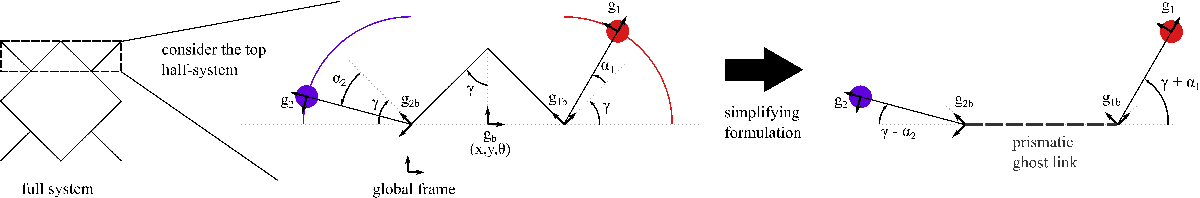

We approach this problem as follows,

1) First we fix the left leg as the base frame and constrain the right-leg translational velocities to zero. Note that the middle link is prismatic with positive expansion rate $\dot{\;l\;}$, and correspondingly have the end frames on the left and right (consider the figure on the right) move apart from each other at $-\frac{\dot{\;l} }{2}$ and $\frac{\dot{\;l} }{2}$ respectively. 

2) Then we find that map that takes the two leg angle shapes and middle link prismatic shape to the body velocity.

Finally, as Capprin recommended, we can look at the lie-bracket over the two leg-angles to compute if there is a net change in length of the center link. In some cases, we many cases we might need the center link to change length!

% define your variables
syms alpha_1 alpha_2 alpha_dot_1 alpha_dot_2 l gamma gamma_dot g_dot_1__theta real

% define vector that help choosing columns in our jacobians
x_dot = [1,0,0]'; y_dot = [0,1,0]'; theta_dot = [0,0,1]';

% Let's define the phantom prismatic link length
mid = 2*l*sin(gamma);

% Inline function to define the SE2 vector:
v_SE2 = @(arm,arm_angle,rota) [arm*cos(arm_angle), arm*sin(arm_angle), rota]';

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% define the transforms for various joints (all transforms needed):
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
H_2__2b = simplify(v2M_SE2(v_SE2(-l, 0, -alpha_2)))

$$H\_2\_\_2b = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & -l\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_2b__2 = simplify(v2M_SE2(v_SE2(l, alpha_2, alpha_2)))

$$H\_2b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & l\,\cos\left(\alpha_{2}\right)\\ \sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & l\,\sin\left(\alpha_{2}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_2b__b = simplify(v2M_SE2(v_SE2(0.5*mid, gamma - pi, gamma - pi)))

$$H\_2b\_\_b = \left(\begin{array}{ccc} -\cos\left(\gamma \right) & \sin\left(\gamma \right) & -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ -\sin\left(\gamma \right) & -\cos\left(\gamma \right) & -l\,{\sin\left(\gamma \right)}^{2}\\ 0 & 0 & 1 \end{array}\right)$$

H_b__2b = simplify(v2M_SE2(v_SE2(-0.5*mid, 0, pi - gamma)))

$$H\_b\_\_2b = \left(\begin{array}{ccc} -\cos\left(\gamma \right) & -\sin\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ \sin\left(\gamma \right) & -\cos\left(\gamma \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_b__1b = simplify(v2M_SE2(v_SE2(0.5*mid, 0, gamma)))

$$H\_b\_\_1b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & l\,\sin\left(\gamma \right)\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_1b__b = simplify(v2M_SE2(v_SE2(0.5*mid, pi - gamma, -gamma)))

$$H\_1b\_\_b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & \sin\left(\gamma \right) & -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ -\sin\left(\gamma \right) & \cos\left(\gamma \right) & l\,{\sin\left(\gamma \right)}^{2}\\ 0 & 0 & 1 \end{array}\right)$$

H_1b__1 = simplify(v2M_SE2(v_SE2(l, alpha_1, alpha_1)))

$$H\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right) & l\,\cos\left(\alpha_{1}\right)\\ \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\sin\left(\alpha_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_1__1b = simplify(v2M_SE2(v_SE2(-l, 0, -alpha_1)))

$$H\_1\_\_1b = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -l\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% Now, we do the first process -- get the translational velocities of g_1
% in terms of g_2's rotational velocity and limb velocities
H_2__1 = simplify(H_2__2b*H_2b__b*H_b__1b*H_1b__1,'Steps',10)

$$H\_2\_\_1 = \begin{array}{l} \left(\begin{array}{ccc} -\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) & \sigma_{1} & -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+1\right)\\ -\sigma_{1} & -\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) & -l\,\left(\sigma_{1}+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)\right)\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) \end{array}$$

h_2__1 = M2v_SE2(H_2__1)

$$h\_2\_\_1 = \left(\begin{array}{c} -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+1\right)\\ -l\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)\right)\\ \alpha_{1}-\alpha_{2}+2\,\gamma \end{array}\right)$$

% Now, we get the end frames on the phantom prismatic link g1b and g2b's
% transform to the end effector g1
H_2b__1 = simplify(H_2b__b*H_b__1b*H_1b__1,'Steps',10)

$$H\_2b\_\_1 = \left(\begin{array}{ccc} -\cos\left(\alpha_{1}+2\,\gamma \right) & \sin\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(\sin\left(2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -\sin\left(\alpha_{1}+2\,\gamma \right) & -\cos\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(2\,{\sin\left(\gamma \right)}^{2}+\sin\left(\alpha_{1}+2\,\gamma \right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

h_2b__1 = M2v_SE2(H_2b__1)

$$h\_2b\_\_1 = \left(\begin{array}{c} -l\,\left(\sin\left(2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -l\,\left(2\,{\sin\left(\gamma \right)}^{2}+\sin\left(\alpha_{1}+2\,\gamma \right)\right)\\ \alpha_{1}+2\,\gamma \end{array}\right)$$

h_1b__1 = M2v_SE2(H_1b__1)

$$h\_1b\_\_1 = \left(\begin{array}{c} l\,\cos\left(\alpha_{1}\right)\\ l\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

% Now, we find the jacobians that will transfer velocities to the end
% effector -- for all of these terms we only need the rotational velocities
J_2__1 = AdjInvMap(h_2__1)

$$J\_2\_\_1 = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & \sigma_{1} & -l\,\left(\sigma_{1}+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -\sigma_{1} & \sigma_{2} & -l\,\left(\sigma_{2}-\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+1\right)\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\\ \sigma_{2}=\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) \end{array}$$

J_2b__1 = AdjInvMap(h_2b__1)

$$J\_2b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}+2\,\gamma \right) & \sin\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -\sin\left(\alpha_{1}+2\,\gamma \right) & \cos\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+1\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_1b__1 = AdjInvMap(h_1b__1)

$$J\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\\ 0 & 0 & 1 \end{array}\right)$$

% Now, we define the velocities generated at each point:
% 1) rotational velocity at the first frame that's fixed
J_2rot = J_2__1*theta_dot

$$J\_2rot = \left(\begin{array}{c} -l\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+1\right)\\ 1 \end{array}\right)$$

% 2) gamma_dot velocity at g_1b and g_2b frames
J_prismatic = J_2b__1*[l, 0, -1]' + J_1b__1*[l, 0, 1]'

$$J\_prismatic = \left(\begin{array}{c} l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)+l\,\cos\left(\alpha_{1}\right)+l\,\cos\left(\alpha_{1}+2\,\gamma \right)\\ l+l\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+1\right)-l\,\sin\left(\alpha_{1}\right)-l\,\sin\left(\alpha_{1}+2\,\gamma \right)\\ 0 \end{array}\right)$$

% 3) limb rotation velocities
J_alpha_1 = J_1b__1*theta_dot

$$J\_alpha\_1 = \left(\begin{array}{c} 0\\ l\\ 1 \end{array}\right)$$

J_alpha_2 = J_2b__1*theta_dot

$$J\_alpha\_2 = \left(\begin{array}{c} -l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -l\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+1\right)\\ 1 \end{array}\right)$$

% Now, we assemble the full jacobian and equate it to zero as shown below


$$\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
J_{\frac{1}{2}}^{\theta \;}  & J_p  & J_{\alpha_1 }  & J_{\alpha_2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{g} }_2^{\theta } \\
\dot{\gamma \;} \\
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{c}
{\dot{g} }_2^{\theta } \\
\dot{\gamma \;} 
\end{array}\right\rbrack =-{\left\lbrack \begin{array}{cc}
J_{\frac{1}{2}}^{\theta \;}  & J_p 
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{cc}
J_{\alpha_1 }  & J_{\alpha_2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack$$


% Now, lets get this full transform to foot rotational velocities and body
% shape change rate from the limb rotation rates.
omega = simplify([eye(2),zeros(2,1)]*[J_2rot, J_prismatic,J_alpha_1, J_alpha_2],'Steps',10)

$$omega = \begin{array}{l} \left(\begin{array}{cccc} -l\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\sigma_{2}\right) & 2\,l\,\cos\left(\alpha_{1}\right) & 0 & -l\,\left(\cos\left(\alpha_{1}\right)-\sigma_{2}\right)\\ -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+\sigma_{1}+1\right) & -2\,l\,\left(\sin\left(\alpha_{1}\right)-1\right) & l & -l\,\left(\sigma_{1}-\sin\left(\alpha_{1}\right)+1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}+2\,\gamma \right)\\ \sigma_{2}=\cos\left(\alpha_{1}+2\,\gamma \right) \end{array}$$

omega_1p = simplify(-omega(:,1:2)^-1 * omega(:,3:4),'Steps',10)

$$omega\_1p = \begin{array}{l} \left(\begin{array}{cc} \frac{\cos\left(\alpha_{1}\right)}{\sigma_{1}} & -\frac{\sin\left(2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)}{\sigma_{1}}\\ \frac{\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)}{2\,\sigma_{1}} & -\frac{\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)}{2\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\gamma \right)-\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)+\cos\left(\alpha_{2}-2\,\gamma \right) \end{array}$$

Let's see what this matrix looks like at the system's mean position,

omega_1p_mean = subs(omega_1p, [alpha_1, alpha_2, gamma], [0, 0, pi/2])

$$omega\_1p\_mean = \left(\begin{array}{cc} -\frac{1}{2} & -\frac{1}{2}\\ -\frac{1}{2} & \frac{1}{2} \end{array}\right)$$

Doesn't look singular at the mean position -- let's complete the formulation to get a sense for what this looks like.

% Find the contribution of 2b and 1b on the body
h_2b__b = M2v_SE2(H_2b__b)

$$h\_2b\_\_b = \left(\begin{array}{c} -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ -l\,{\sin\left(\gamma \right)}^{2}\\ \gamma \end{array}\right)$$

h_1b__b = M2v_SE2(H_1b__b)

$$h\_1b\_\_b = \left(\begin{array}{c} -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ l\,{\sin\left(\gamma \right)}^{2}\\ -\gamma \end{array}\right)$$

J_2b__b = AdjInvMap(h_2b__b)

$$J\_2b\_\_b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & \sin\left(\gamma \right) & 0\\ -\sin\left(\gamma \right) & \cos\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

J_1b__b = AdjInvMap(h_1b__b)

$$J\_1b\_\_b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & 0\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

J_g__b = J_2b__b*[l, 0, -1]' + J_1b__b*[l, 0, 1]'

$$J\_g\_\_b = \left(\begin{array}{c} 2\,l\,\cos\left(\gamma \right)\\ 0\\ 0 \end{array}\right)$$

J_alpha2__b = J_2b__b*theta_dot

$$J\_alpha2\_\_b = \left(\begin{array}{c} 0\\ -l\,\sin\left(\gamma \right)\\ 1 \end{array}\right)$$

J_alpha1__b = J_1b__b*theta_dot

$$J\_alpha1\_\_b = \left(\begin{array}{c} 0\\ -l\,\sin\left(\gamma \right)\\ 1 \end{array}\right)$$

The final jacobian from limb velocities to body velocity is given by,

J_full = simplify([J_alpha1__b, J_alpha2__b, J_g__b]*[1,0,0,0;
                                            0,1,0,0;
                                            0,0,0,1]*[eye(2);omega_1p],'Steps',10)

$$J\_full = \begin{array}{l} \left(\begin{array}{cc} \frac{l\,\cos\left(\gamma \right)\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)}{\sigma_{1}} & -\frac{l\,\cos\left(\gamma \right)\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)\right)}{\sigma_{1}}\\ -l\,\sin\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\gamma \right)-\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)+\cos\left(\alpha_{2}-2\,\gamma \right) \end{array}$$

Let's evaluate this jacobian at mean robot position

J_full_mean = subs(J_full,[alpha_1,alpha_2,gamma],[0, 0, pi/2])

$$J\_full\_mean = \left(\begin{array}{cc} 0 & 0\\ -l & -l\\ 1 & 1 \end{array}\right)$$

This is an invalid position since if I try a 'breast-stroke'-kinda gait with ${\dot{\alpha} }_1 ={\dot{-\alpha } }_2 =-k,\;\;k\in Z^+$, we get no motion since it is a bifurcation point.

**Metric: **Let's use the same rate-limit of 1 rad/s for both legs -- hence an identity metric.

Also, let's assume for the $\gamma$-controlled case (or all shapes are controlled), the **A** matrix is given by,

A_fullC = simplify([J_alpha1__b, J_alpha2__b,J_g__b],'Steps',10)

$$A\_fullC = \left(\begin{array}{ccc} 0 & 0 & 2\,l\,\cos\left(\gamma \right)\\ -l\,\sin\left(\gamma \right) & -l\,\sin\left(\gamma \right) & 0\\ 1 & 1 & 0 \end{array}\right)$$

## Important Takeaways

Where you start the gait is important -- below you find a plots the inter-leg distance as a function of $\alpha_1$, $\alpha_2$, and $\gamma$.

 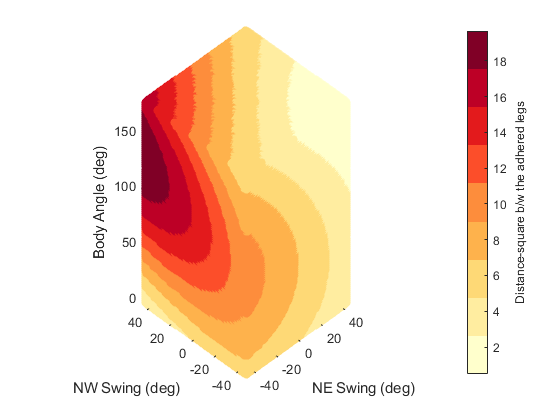

NE and NW swing refer to $\alpha_1$ and $\alpha_2$ respectively!

## Kinematic Solver and Geometric Local Connection based on inter-leg constraints

We start by writing transforms to each leg tip,

syms x y theta alpha_1 alpha_2 gamma l a real
vec_SE2 = @(x_arm,y_arm,rota) [x_arm, y_arm, rota]';
h_e__0 = vec_SE2(x, y, theta)

$$h\_e\_\_0 = \left(\begin{array}{c} x\\ y\\ \theta \end{array}\right)$$

H_e__0 = v2M_SE2(h_e__0)

$$H\_e\_\_0 = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & x\\ \sin\left(\theta \right) & \cos\left(\theta \right) & y\\ 0 & 0 & 1 \end{array}\right)$$

% define the leg position for the top two legs (base and leg tip)
h_0__1b = v_SE2(l, gamma, gamma);
H_0__1b = v2M_SE2(h_0__1b)

$$H\_0\_\_1b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & l\,\cos\left(\gamma \right)\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

h_1b__1 = v_SE2(a*l, alpha_1, alpha_1);
H_1b__1 = v2M_SE2(h_1b__1)

$$H\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right) & a\,l\,\cos\left(\alpha_{1}\right)\\ \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & a\,l\,\sin\left(\alpha_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_e__1 = simplify(H_e__0*H_0__1b*H_1b__1,'Steps',10)

$$H\_e\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}+\gamma +\theta \right) & -\sin\left(\alpha_{1}+\gamma +\theta \right) & x+l\,\cos\left(\gamma +\theta \right)+a\,l\,\cos\left(\alpha_{1}+\gamma +\theta \right)\\ \sin\left(\alpha_{1}+\gamma +\theta \right) & \cos\left(\alpha_{1}+\gamma +\theta \right) & y+l\,\sin\left(\gamma +\theta \right)+a\,l\,\sin\left(\alpha_{1}+\gamma +\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

h_0__2b = v_SE2(l, pi-gamma, pi-gamma);
H_0__2b = v2M_SE2(h_0__2b)

$$H\_0\_\_2b = \left(\begin{array}{ccc} -\cos\left(\gamma \right) & -\sin\left(\gamma \right) & -l\,\cos\left(\gamma \right)\\ \sin\left(\gamma \right) & -\cos\left(\gamma \right) & l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

h_2b__2 = v_SE2(a*l, alpha_2, alpha_2);
H_2b__2 = v2M_SE2(h_2b__2)

$$H\_2b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & a\,l\,\cos\left(\alpha_{2}\right)\\ \sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & a\,l\,\sin\left(\alpha_{2}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_e__2 = simplify(H_e__0*H_0__2b*H_2b__2,'Steps',10)

$$H\_e\_\_2 = \left(\begin{array}{ccc} -\cos\left(\alpha_{2}-\gamma +\theta \right) & \sin\left(\alpha_{2}-\gamma +\theta \right) & x-l\,\cos\left(\gamma -\theta \right)-a\,l\,\cos\left(\alpha_{2}-\gamma +\theta \right)\\ -\sin\left(\alpha_{2}-\gamma +\theta \right) & -\cos\left(\alpha_{2}-\gamma +\theta \right) & y+l\,\sin\left(\gamma -\theta \right)-a\,l\,\sin\left(\alpha_{2}-\gamma +\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

Notice that this is a nonlinear function of $\theta \;$as well and hence breaks the standard symmetry in Geometric Mechanics. Let's explore this a little further,

h_e__1 = M2v_SE2(H_e__1); h_e__2 = M2v_SE2(H_e__2);
% Consider only the first two elements of the three element SE(2) vector:
choose_12 = [eye(2), zeros(2,1);
            zeros(1,3)];
% Get the distance vector:
kvec = choose_12*(h_e__1-h_e__2)

$$kvec = \left(\begin{array}{c} l\,\cos\left(\gamma +\theta \right)+l\,\cos\left(\gamma -\theta \right)+a\,l\,\cos\left(\alpha_{1}+\gamma +\theta \right)+a\,l\,\cos\left(\alpha_{2}-\gamma +\theta \right)\\ l\,\sin\left(\gamma +\theta \right)-l\,\sin\left(\gamma -\theta \right)+a\,l\,\sin\left(\alpha_{1}+\gamma +\theta \right)+a\,l\,\sin\left(\alpha_{2}-\gamma +\theta \right)\\ 0 \end{array}\right)$$

**Taking analytical derivatives, and simplifying we have the following two expressions (ignoring the third row),**

$e_{31} \;\dot{\gamma} +e_{31a} \;{\dot{\;\alpha } }_1 +e_{32a} \;{\dot{\;\alpha } }_2 =e_{32} \;\dot{\theta}$**, **

$e_{41} \;\dot{\gamma} +e_{41a} \;{\dot{\;\alpha } }_1 +e_{42a} \;{\dot{\;\alpha } }_2 =e_{42} \;\dot{\theta}$.

expr32 = sin(gamma+theta) - sin(gamma-theta) + a*sin(alpha_1+gamma+theta) + a*sin(alpha_2-gamma+theta)

$$expr32 = \sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)$$

expr31 = -sin(gamma+theta) - sin(gamma-theta) - a*sin(alpha_1+gamma+theta) + a*sin(alpha_2-gamma+theta)

$$expr31 = a\,\sin\left(\alpha_{2}-\gamma +\theta \right)-\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)-a\,\sin\left(\alpha_{1}+\gamma +\theta \right)$$

expr31a =  -a*sin(alpha_1+gamma+theta); expr32a = -a*sin(alpha_2-gamma+theta); % no simplification needed
expr41 = cos(gamma+theta) - cos(gamma-theta) + a*cos(alpha_1+gamma+theta) - a*cos(alpha_2-gamma+theta)

$$expr41 = \cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)$$

expr42 = -cos(gamma+theta) - cos(gamma-theta) - a*cos(alpha_1+gamma+theta) - a*cos(alpha_2-gamma+theta)

$$expr42 = -\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)-a\,\cos\left(\alpha_{1}+\gamma +\theta \right)$$

expr41a =  a*cos(alpha_1+gamma+theta); expr42a = a*cos(alpha_2-gamma+theta); % no simplification needed

Now, we can work out the simplifications.

gamma_hat = simplify(expr31/expr32 - expr41/expr42, 'Steps', 50)

$$gamma\_hat = -\frac{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\left(\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)\right)\,\left(\cos\left(\gamma +\theta \right)+\cos\left(\gamma -\theta \right)+a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)\right)}$$

alpha_hat_1 = expr41a/expr42 - expr31a/expr32 % we don't have to simplify this expression and the one below

$$alpha\_hat\_1 = \frac{a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}{\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)+\cos\left(\gamma -\theta \right)+a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

alpha_hat_2 = expr42a/expr42 - expr32a/expr32

$$alpha\_hat\_2 = \frac{a\,\sin\left(\alpha_{2}-\gamma +\theta \right)}{\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{2}-\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)+\cos\left(\gamma -\theta \right)+a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

Compute the final coefficients of the map from the leg-swing velocities ($\dot{\alpha}$) to sprawl velocity ($\dot{\gamma}$),

alpha_coeff_1_gamma = simplify((gamma_hat^-1)*alpha_hat_1, 'Steps', 50)

$$alpha\_coeff\_1\_gamma = -\frac{a\,\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

alpha_coeff_2_gamma = simplify((gamma_hat^-1)*alpha_hat_2, 'Steps', 50)

$$alpha\_coeff\_2\_gamma = -\frac{a\,\left(\sin\left(\alpha_{2}\right)+\sin\left(\alpha_{2}-2\,\gamma \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

% gamma_map
gamma_map = [alpha_coeff_1_gamma alpha_coeff_2_gamma]

$$gamma\_map = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)+\sin\left(\alpha_{2}-2\,\gamma \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

As a next step, we now compute the system's rotational velocity ($\dot{\theta}$) as a function of the leg-swing velocities ($\dot{\alpha}$),

$e_{32} \;\dot{\theta} -e_{31a} \;{\dot{\;\alpha } }_1 -e_{32a} \;{\dot{\;\alpha } }_2 =e_{31} \;\dot{\gamma}$**, **

$e_{42} \;\dot{\theta} -e_{41a} \;{\dot{\;\alpha } }_1 -e_{42a} \;{\dot{\;\alpha } }_2 =e_{41} \;\dot{\gamma}$.

Let's use the same approach as above to the obtain the coefficients,

theta_hat = simplify(expr32/expr31 - expr42/expr41, 'Steps', 50)

$$theta\_hat = \frac{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\left(\sin\left(\gamma -\theta \right)+\sin\left(\gamma +\theta \right)-a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)\right)\,\left(\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)\right)}$$

alpha_hat_1 = -expr41a/expr41 + expr31a/expr31

$$alpha\_hat\_1 = \frac{a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}{\sin\left(\gamma -\theta \right)+\sin\left(\gamma +\theta \right)-a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

alpha_hat_2 = -expr42a/expr41 + expr32a/expr31

$$alpha\_hat\_2 = \frac{a\,\sin\left(\alpha_{2}-\gamma +\theta \right)}{\sin\left(\gamma -\theta \right)+\sin\left(\gamma +\theta \right)-a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{2}-\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

alpha_coeff_1_theta = simplify((theta_hat^-1)*alpha_hat_1, 'Steps', 50)

$$alpha\_coeff\_1\_theta = -\frac{a\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

alpha_coeff_2_theta = simplify((theta_hat^-1)*alpha_hat_2, 'Steps', 50)

$$alpha\_coeff\_2\_theta = -\frac{a\,\left(\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

% theta_map
theta_map = [alpha_coeff_1_theta alpha_coeff_2_theta]

$$theta\_map = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

Note that the denominator of the coefficients are the same for both sprawl and orientation maps, and this needs to be non-singular. Also, we can scale down the expression by a factor of two, and then plot the values as a heat map.

[~, cond_shape] = numden(alpha_coeff_1_theta)

$$cond\_shape = 2\,\sin\left(2\,\gamma \right)+2\,a\,\sin\left(\alpha_{1}+2\,\gamma \right)-2\,a\,\sin\left(\alpha_{2}-2\,\gamma \right)+2\,a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)$$

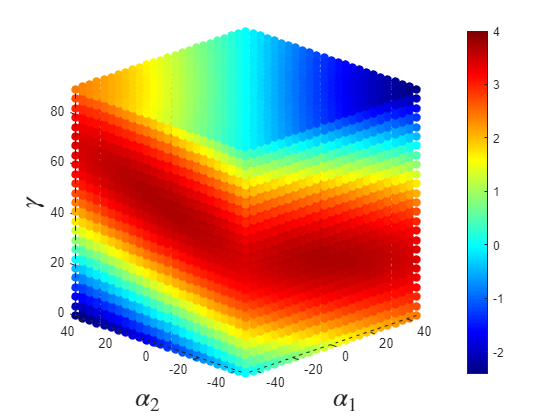

% Convert this into a function as well
cond_shape = cond_shape/2; cond_shape = matlabFunction(cond_shape);
% Number of points in each direction
num = 25;
% Initialize leg swing limits:
ank = pi/4;
% Initialize a domain for the shapes and mesh grid:
[A1,A2,G] = meshgrid(linspace(-ank,ank,num),linspace(-ank,ank,num),linspace(0,pi/2,num));
% Set the leg length fraction as 1:
A = 1; % try 'ones(size(A1))' if just '1' doesn't work
% Evaluate the function at these points:
c_shape = cond_shape(A,A1,A2,G);
% Make all the arrays linear:
am = reshape(A1,1,numel(A1)); ap = reshape(A2,1,numel(A2)); g = reshape(G,1,numel(G));
c_shape = reshape(c_shape,1,numel(c_shape));
% Let's plot this:
figure()
scatter3(rad2deg(am),rad2deg(ap),rad2deg(g),40,c_shape,'filled');
ax = gca;
view(-45,20)
xlabel('$\alpha_1$','Interpreter','latex','FontSize',20)
ylabel('$\alpha_2$','Interpreter','latex','FontSize',20)
zlabel('$\gamma$','Interpreter','latex','FontSize',20)
axis equal;
colormap(jet)
cb = colorbar;                        % create and label the colorbar

The singularity in our maps doesn't seem to be a function of the bifurcation, but rather indicates the inability to predict the change in sprawl or orientation of the system.

Here, we shall obtain the local connection for the augmented SE(2) locomotion of the system by incorporating the sprawl as the 4th position variable.

Analytical derivatives on the foot position (x and y components) are needed to obtain this map.

$\dot{x} =-\frac{1}{2}l\left\lbrack \begin{array}{cc}
\textrm{e31}\;{\hat{\alpha} }_1^{\theta \;} -\textrm{e32}\;{\hat{\alpha} }_1^{\gamma \;} +\textrm{e31a} & \textrm{e31}\;{\hat{\alpha} }_2^{\theta \;} -\textrm{e32}\;{\hat{\alpha} }_2^{\gamma \;} -\textrm{e32a}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack$,

$\dot{y} =-\frac{1}{2}l\left\lbrack \begin{array}{cc}
\textrm{e41}\;{\hat{\alpha} }_1^{\theta \;} -\textrm{e42}\;{\hat{\alpha} }_1^{\gamma \;} +\textrm{e41a} & \textrm{e41}\;{\hat{\alpha} }_2^{\theta \;} -\textrm{e42}\;{\hat{\alpha} }_2^{\gamma \;} -\textrm{e42a}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack$.

% x_map:
x_map = -0.5*l*[expr31*alpha_coeff_1_theta - expr32*alpha_coeff_1_gamma + expr31a, expr31*alpha_coeff_2_theta - expr32*alpha_coeff_2_gamma - expr32a];
x_map = simplify(x_map, 'Steps', 50)

$$x\_map = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,l\,\left(\cos\left(\alpha_{1}+\gamma -\theta \right)-\cos\left(\alpha_{1}-\gamma +\theta \right)-a\,\cos\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\cos\left(\alpha_{2}+\gamma +\theta \right)-\cos\left(\gamma -\alpha_{2}+\theta \right)+a\,\cos\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

% y_map
y_map = -0.5*l*[expr41*alpha_coeff_1_theta - expr42*alpha_coeff_1_gamma + expr41a, expr41*alpha_coeff_2_theta - expr42*alpha_coeff_2_gamma - expr42a];
y_map = simplify(y_map, 'Steps', 50)

$$y\_map = \begin{array}{l} \left(\begin{array}{cc} \frac{a\,l\,\left(\sin\left(\alpha_{1}+\gamma -\theta \right)+\sin\left(\alpha_{1}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\sin\left(\alpha_{2}+\gamma +\theta \right)-\sin\left(\gamma -\alpha_{2}+\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

***The local connection is hence given by,***

local_conn = simplify([x_map;
                y_map;
                theta_map;
                gamma_map], "Steps", 50)

$$local\_conn = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,l\,\left(\cos\left(\alpha_{1}+\gamma -\theta \right)-\cos\left(\alpha_{1}-\gamma +\theta \right)-a\,\cos\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\cos\left(\alpha_{2}+\gamma +\theta \right)-\cos\left(\gamma -\alpha_{2}+\theta \right)+a\,\cos\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}}\\ \frac{a\,l\,\left(\sin\left(\alpha_{1}+\gamma -\theta \right)+\sin\left(\alpha_{1}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\sin\left(\alpha_{2}+\gamma +\theta \right)-\sin\left(\gamma -\alpha_{2}+\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}}\\ -\frac{a\,\left(\sigma_{3}-\sin\left(\alpha_{1}\right)+a\,\sigma_{4}\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)-\sigma_{2}+a\,\sigma_{4}\right)}{\sigma_{1}}\\ -\frac{a\,\left(\sin\left(\alpha_{1}\right)+\sigma_{3}+a\,\sigma_{4}\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)+\sigma_{2}-a\,\sigma_{4}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sigma_{3}-a\,\sigma_{2}+a^{2}\,\sigma_{4}\right)\\ \sigma_{2}=\sin\left(\alpha_{2}-2\,\gamma \right)\\ \sigma_{3}=\sin\left(\alpha_{1}+2\,\gamma \right)\\ \sigma_{4}=\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) \end{array}$$

## From Capprin's notes -- leg velocities zeroed out separately through a selection labrix

THERE ARE SOME ERRORS HERE; IT WILL BE FIXED IN THE NEXT SECTION -- LOOK FOR "*CORRECTION*"; issues stem from incorrect frame descriptions. Also, the left multiplication convention was violated.

Before we start, let's define some functions that will be used later to help run this section without dependencies from the previous section.

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

Here, we shall obtain the leg velocities for the top-half of the CLARI system and zero them out manually through a connection matrix. 

We shall consider two cases for the connection where the body frame g_0 or g_b as being at the center and at the tip of the nose.

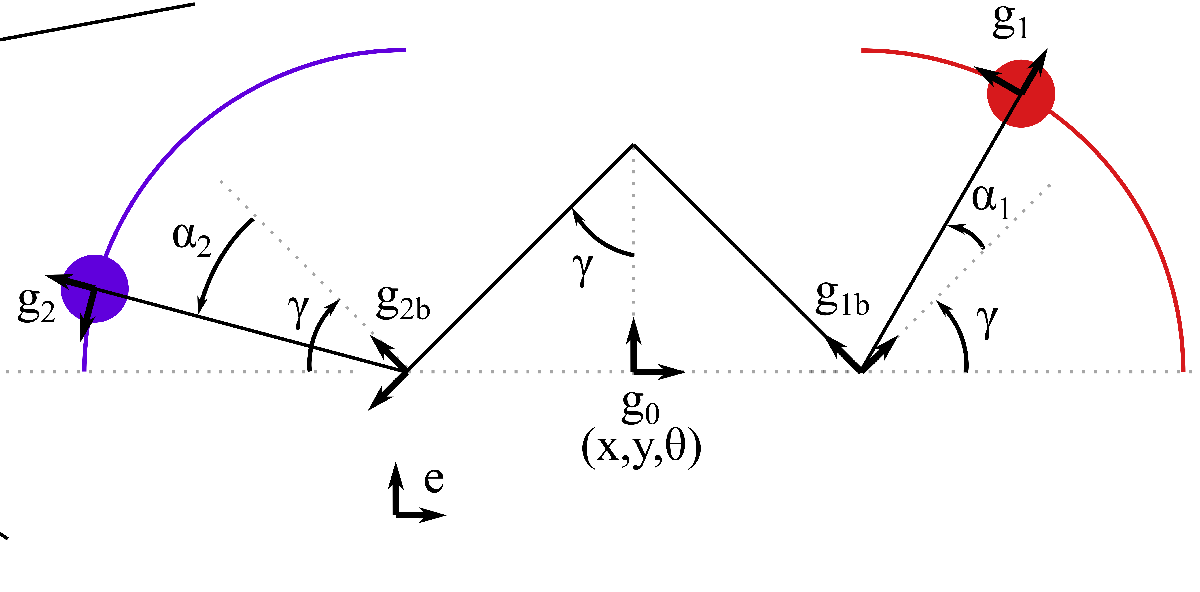

Each $i^{\textrm{th}}$ leg is controlled only by the corresponding leg's hip joint angle, $\alpha_i$. This makes the other jacobian columns zero as the other legs angles don't control the considered leg. 

% Get vector that propagate the joint velocities -- choose the third column:
theta_circ = [0,0,1]';
% Obtain the Jacobian to base of each leg:
syms l gamma real
h_b__1b = [l*[sin(gamma); -cos(gamma)]; gamma]

$$h\_b\_\_1b = \left(\begin{array}{c} l\,\sin\left(\gamma \right)\\ -l\,\cos\left(\gamma \right)\\ \gamma \end{array}\right)$$

h_b__2b = [-l*[sin(gamma); cos(gamma)]; pi-gamma]

$$h\_b\_\_2b = \left(\begin{array}{c} -l\,\sin\left(\gamma \right)\\ -l\,\cos\left(\gamma \right)\\ \pi -\gamma \end{array}\right)$$

% Obtaining the Jacobian for each leg in terms of its hip joint angle
syms a real positive
syms alpha_i alpha_1 alpha_2 real
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i]

$$h\_ib\_\_i = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{i}\right)\\ a\,l\,\sin\left(\alpha_{i}\right)\\ \alpha_{i} \end{array}\right)$$

h_1b__1 = subs(h_ib__i, alpha_i, alpha_1)

$$h\_1b\_\_1 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{1}\right)\\ a\,l\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

h_2b__2 = subs(h_ib__i, alpha_i, alpha_2)

$$h\_2b\_\_2 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{2}\right)\\ a\,l\,\sin\left(\alpha_{2}\right)\\ \alpha_{2} \end{array}\right)$$

J_ib__i = AdjInvMap(h_ib__i)

$$J\_ib\_\_i = \left(\begin{array}{ccc} \cos\left(\alpha_{i}\right) & \sin\left(\alpha_{i}\right) & 0\\ -\sin\left(\alpha_{i}\right) & \cos\left(\alpha_{i}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a,l,alpha_i]);
% Now, obtain the specfic forms for each leg - Jacobians from foot to
% leg-base
J_1b__1 = J_ib__i_func(a,l,alpha_1)

$$J\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_2b__2 = J_ib__i_func(a,l,alpha_2)

$$J\_2b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

% Create empty vectors for joints that don't control the corresponding legs
J_1b__2 = zeros(3,3); J_2b__1 = zeros(3,3);
% Jacobians from foot to base-frame
J_b__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_1b__1)*v2M_SE2(h_b__1b)))

$$J\_b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & l\,\left(a\,\sin\left(\gamma \right)+1\right)\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & a\,l\,\cos\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

J_b__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_2b__2)*v2M_SE2(h_b__2b)))

$$J\_b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & -l\,\left(a\,\sin\left(\gamma \right)-1\right)\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & a\,l\,\cos\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

Now, we are ready to form the full Jacobian for each leg if the velocity vector is of the following form $\left\lbrack \begin{array}{c}
\dot{g} \\
\dot{\alpha} \\
\dot{\gamma} 
\end{array}\right\rbrack$,

J_1_full = [J_b__1, J_b__1*theta_circ, J_1b__1*theta_circ, J_2b__1*theta_circ]

$$J\_1\_full = \left(\begin{array}{cccccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & l\,\left(a\,\sin\left(\gamma \right)+1\right) & l\,\left(a\,\sin\left(\gamma \right)+1\right) & 0 & 0\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & a\,l\,\cos\left(\gamma \right) & a\,l\,\cos\left(\gamma \right) & a\,l & 0\\ 0 & 0 & 1 & 1 & 1 & 0 \end{array}\right)$$

J_2_full = [J_b__2, J_b__2*theta_circ, J_1b__2*theta_circ, J_2b__2*theta_circ]

$$J\_2\_full = \left(\begin{array}{cccccc} \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & -l\,\left(a\,\sin\left(\gamma \right)-1\right) & -l\,\left(a\,\sin\left(\gamma \right)-1\right) & 0 & 0\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & a\,l\,\cos\left(\gamma \right) & a\,l\,\cos\left(\gamma \right) & 0 & a\,l\\ 0 & 0 & 1 & 1 & 0 & 1 \end{array}\right)$$

Next, we can choose the first two rows with a selection matrix 'C' and then concatenate them along rows to obtain our pfaffian constraint matrix 'pfaff'.

C = [eye(2,2),zeros(2,1)];
pfaff = [C*J_1_full;
        C*J_2_full]

$$pfaff = \begin{array}{l} \left(\begin{array}{cccccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & \sigma_{3} & \sigma_{3} & 0 & 0\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & \sigma_{1} & \sigma_{1} & a\,l & 0\\ \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & \sigma_{2} & \sigma_{2} & 0 & 0\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & \sigma_{1} & \sigma_{1} & 0 & a\,l \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a\,l\,\cos\left(\gamma \right)\\ \sigma_{2}=-l\,\left(a\,\sin\left(\gamma \right)-1\right)\\ \sigma_{3}=l\,\left(a\,\sin\left(\gamma \right)+1\right) \end{array}$$

% Make sure a negative sign is added when evaluating the connection since
% it is defined in a traditional sense. The extended connection stands for
% SE(2) velocities contactenated with sprawl velocity map
A_ext = pfaff(:,1:4)\pfaff(:,5:end)

$$A\_ext = \left(\begin{array}{cc} \infty & \infty \\ \infty & \infty \\ \infty & \infty \\ \infty & \infty \end{array}\right)$$

Solution doesn't exist since the system is inconsistent; meaning, there is no single map given our sprawl setup. Let's not try to have the sprawl as a controlled shape and see what happens.

pfaff(:,1:3)\pfaff(:,4:end)

$$ans = \left(\begin{array}{ccc} \infty & \infty & \infty \\ \infty & \infty & \infty \\ \infty & \infty & \infty \end{array}\right)$$

Let's try the same for a body frame at the COM; most outputs should be suppresed except at the connection computation. Things shouldn't change too much.

h_b__1b_CM = [l*[sin(gamma); 0]; gamma];
h_b__2b_CM = [-l*[sin(gamma); 0]; pi-gamma];
J_b__1_CM = AdjInvMap(M2v_SE2(v2M_SE2(h_1b__1)*v2M_SE2(h_b__1b_CM)));
J_b__2_CM = AdjInvMap(M2v_SE2(v2M_SE2(h_2b__2)*v2M_SE2(h_b__2b_CM)));
J_1_full_CM = [J_b__1_CM, J_b__1_CM*theta_circ, J_1b__1*theta_circ, J_2b__1*theta_circ];
J_2_full_CM = [J_b__2_CM, J_b__2_CM*theta_circ, J_1b__2*theta_circ, J_2b__2*theta_circ];
pfaff_CM = [C*J_1_full_CM;
        C*J_2_full_CM];
A_ext_CM = pfaff_CM(:,1:4)\pfaff_CM(:,5:end)

pfaff_CM(:,1:3)\pfaff_CM(:,4:end)

$$ans = \left(\begin{array}{ccc} \infty & \infty & \infty \\ \infty & \infty & \infty \\ \infty & \infty & \infty \end{array}\right)$$

Irrespective of our coordinate choice for the body frame, the result seems to be the fact that the sprawl doesn't have a unique solution as a surface that folds on itself for the simultaneous leg contact locomotion. Let's look at the determinant, rank, everything needed to tease out the nature of this non-invertibility to obtain the local connection.

omega_gbg = pfaff_CM(:,1:4)

$$omega\_gbg = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & \sigma_{4} & \sigma_{4}\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & \sigma_{2} & \sigma_{2}\\ \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & \sigma_{3} & \sigma_{3}\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{l\,\left(\sin\left(2\,\gamma \right)-2\,a\,\cos\left(\gamma \right)\right)}{2}\\ \sigma_{2}=\frac{l\,\left(\sin\left(2\,\gamma \right)+2\,a\,\cos\left(\gamma \right)\right)}{2}\\ \sigma_{3}=-l\,\sin\left(\gamma \right)\,\left(a-\sin\left(\gamma \right)\right)\\ \sigma_{4}=l\,\sin\left(\gamma \right)\,\left(a+\sin\left(\gamma \right)\right) \end{array}$$

% det_omega_gbgamma = det(omega_gbg)
% % simplify(eig(omega_gbg))
% eig(omega_gbg)

There seems to be a zero eigenvalue and the rest are complicated; now we would like to explore connection numerically as a parametric sweep through the shape-space of the system. **The key idea would be to find limit-cycles in sprawl for pure translational/rotational gaits; **a great place to start and we can focus on just the SE(2) locomotion and tease out some properties.

Let's save these pfaffian constraint matrix for later use.

save('pfaffian_constraint_CLARI.mat','a','l','gamma','alpha_1','alpha_2','pfaff_CM');

### Corrections from previous section--------------------------------------------------------------------------------------------------------------------------------------------------

Here, I will redefine the frames to avoid confusion and then, attempt to construct two connections for two different body frames; $g_{ b}$ and $g_{bg}$ as shown in the figure below.

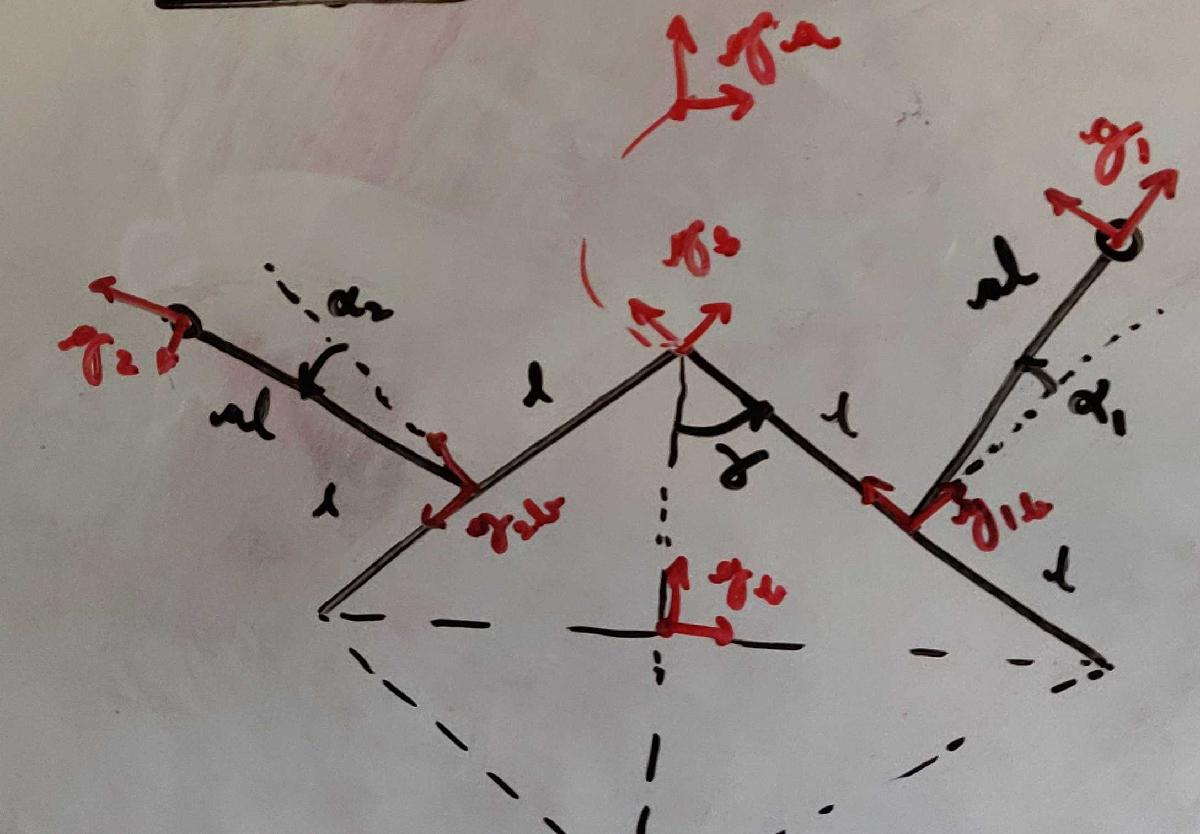

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';

syms l gamma real
h_b__1b = [l*[sin(gamma); cos(gamma)]; gamma]

$$h\_b\_\_1b = \left(\begin{array}{c} l\,\sin\left(\gamma \right)\\ l\,\cos\left(\gamma \right)\\ \gamma \end{array}\right)$$

h_b__2b = [l*[-sin(gamma); cos(gamma)]; pi-gamma]

$$h\_b\_\_2b = \left(\begin{array}{c} -l\,\sin\left(\gamma \right)\\ l\,\cos\left(\gamma \right)\\ \pi -\gamma \end{array}\right)$$

h_a__1b = [l*[sin(gamma); -cos(gamma)]; gamma]

$$h\_a\_\_1b = \left(\begin{array}{c} l\,\sin\left(\gamma \right)\\ -l\,\cos\left(\gamma \right)\\ \gamma \end{array}\right)$$

h_a__2b = [-l*[sin(gamma); cos(gamma)]; pi-gamma]

$$h\_a\_\_2b = \left(\begin{array}{c} -l\,\sin\left(\gamma \right)\\ -l\,\cos\left(\gamma \right)\\ \pi -\gamma \end{array}\right)$$

syms a real positive
syms alpha_i alpha_1 alpha_2 real
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i]

$$h\_ib\_\_i = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{i}\right)\\ a\,l\,\sin\left(\alpha_{i}\right)\\ \alpha_{i} \end{array}\right)$$

h_1b__1 = subs(h_ib__i, alpha_i, alpha_1)

$$h\_1b\_\_1 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{1}\right)\\ a\,l\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

h_2b__2 = subs(h_ib__i, alpha_i, alpha_2)

$$h\_2b\_\_2 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{2}\right)\\ a\,l\,\sin\left(\alpha_{2}\right)\\ \alpha_{2} \end{array}\right)$$

J_ib__i = AdjInvMap(h_ib__i)

$$J\_ib\_\_i = \left(\begin{array}{ccc} \cos\left(\alpha_{i}\right) & \sin\left(\alpha_{i}\right) & 0\\ -\sin\left(\alpha_{i}\right) & \cos\left(\alpha_{i}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a,l,alpha_i]);

J_1b__1 = J_ib__i_func(a,l,alpha_1)

$$J\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_2b__2 = J_ib__i_func(a,l,alpha_2)

$$J\_2b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_1b__2 = zeros(3,3); % just a bunch of zeroes to control the wrong leg
J_2b__1 = zeros(3,3);

h_s__1b = [0, -l, 0]' % was +l and the connections were clean

$$h\_s\_\_1b = \left(\begin{array}{c} 0\\ -l\\ 0 \end{array}\right)$$

h_s__2b = [-l*[sin(2*gamma); cos(2*gamma)]; pi-2*gamma]'

$$h\_s\_\_2b = \left(\begin{array}{ccc} -l\,\sin\left(2\,\gamma \right) & -l\,\cos\left(2\,\gamma \right) & \pi -2\,\gamma \end{array}\right)$$

Once you have these transforms, it is always good to plot some robot positions to make sure the transforms you get make sense.

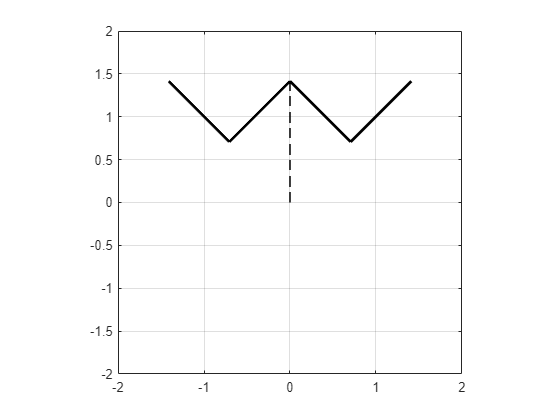

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % TRANSFORM VALIDAITON COMPLETE
% We need these transforms to plot the system as a sanity check
h_b__a = M2v_SE2(v2M_SE2(h_b__1b)*v2M_SE2([0,l,-gamma]'));
h_b__1 = M2v_SE2(v2M_SE2(h_b__1b)*v2M_SE2(h_1b__1));
h_b__2 = M2v_SE2(v2M_SE2(h_b__2b)*v2M_SE2(h_2b__2));

sprawljoint_x = [0 h_b__a(1)]; sprawljoint_y = [0 h_b__a(2)];
sprawl_legbase1_x = [h_b__a(1) h_b__1b(1)]; sprawl_legbase1_y = [h_b__a(2) h_b__1b(2)];
sprawl_legbase2_x = [h_b__a(1) h_b__2b(1)]; sprawl_legbase2_y = [h_b__a(2) h_b__2b(2)];
legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];

sprawljoint_x = double(subs(sprawljoint_x,[gamma, l],[pi/4, 1])); % equilibrium position of the robot
sprawljoint_y = double(subs(sprawljoint_y,[gamma, l],[pi/4, 1]));

sprawl_legbase1_x = double(subs(sprawl_legbase1_x,[gamma, l],[pi/4, 1]));
sprawl_legbase1_y = double(subs(sprawl_legbase1_y,[gamma, l],[pi/4, 1]));
sprawl_legbase2_x = double(subs(sprawl_legbase2_x,[gamma, l],[pi/4, 1]));
sprawl_legbase2_y = double(subs(sprawl_legbase2_y,[gamma, l],[pi/4, 1]));

legbase1_leg1_x =  double(subs(legbase1_leg1_x,[gamma, a, l, alpha_1],[pi/4, 1, 1, 0]));
legbase1_leg1_y =  double(subs(legbase1_leg1_y,[gamma, a, l, alpha_1],[pi/4, 1, 1, 0]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[gamma, a, l, alpha_2],[pi/4, 1, 1, 0]));
legbase2_leg2_y =  double(subs(legbase2_leg2_y,[gamma, a, l, alpha_2],[pi/4, 1, 1, 0]));

figure()
plot(sprawljoint_x,sprawljoint_y,'k--','LineWidth',1.2);
hold on; grid on;
% Plot the sprawl to each leg base
plot(sprawl_legbase1_x,sprawl_legbase1_y,'k','LineWidth',2);
plot(sprawl_legbase2_x,sprawl_legbase2_y,'k','LineWidth',2);
plot(legbase1_leg1_x,legbase1_leg1_y,'k','LineWidth',2);
axis equal square; ylim([-2, 2]); xlim([-2, 2]); 
plot(legbase2_leg2_x,legbase2_leg2_y,'k','LineWidth',2);

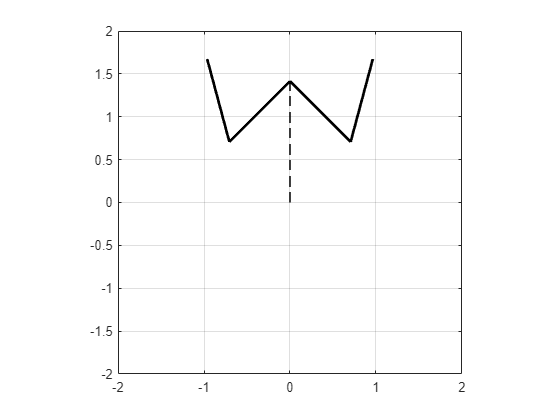


sprawljoint_x = [0 h_b__a(1)]; sprawljoint_y = [0 h_b__a(2)];
sprawl_legbase1_x = [h_b__a(1) h_b__1b(1)]; sprawl_legbase1_y = [h_b__a(2) h_b__1b(2)];
sprawl_legbase2_x = [h_b__a(1) h_b__2b(1)]; sprawl_legbase2_y = [h_b__a(2) h_b__2b(2)];
legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
sprawljoint_x = double(subs(sprawljoint_x,[gamma, l],[pi/4, 1]));
sprawljoint_y = double(subs(sprawljoint_y,[gamma, l],[pi/4, 1]));
sprawl_legbase1_x = double(subs(sprawl_legbase1_x,[gamma, l],[pi/4, 1]));
sprawl_legbase1_y = double(subs(sprawl_legbase1_y,[gamma, l],[pi/4, 1]));
sprawl_legbase2_x = double(subs(sprawl_legbase2_x,[gamma, l],[pi/4, 1]));
sprawl_legbase2_y = double(subs(sprawl_legbase2_y,[gamma, l],[pi/4, 1]));
legbase1_leg1_x =  double(subs(legbase1_leg1_x,[gamma, a, l, alpha_1],[pi/4, 1, 1, pi/6]));
legbase1_leg1_y =  double(subs(legbase1_leg1_y,[gamma, a, l, alpha_1],[pi/4, 1, 1, pi/6]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[gamma, a, l, alpha_2],[pi/4, 1, 1, -pi/6]));
legbase2_leg2_y =  double(subs(legbase2_leg2_y,[gamma, a, l, alpha_2],[pi/4, 1, 1, -pi/6]));

figure()
plot(sprawljoint_x,sprawljoint_y,'k--','LineWidth',1.2);
hold on; grid on;
plot(sprawl_legbase1_x,sprawl_legbase1_y,'k','LineWidth',2);
plot(sprawl_legbase2_x,sprawl_legbase2_y,'k','LineWidth',2);
plot(legbase1_leg1_x,legbase1_leg1_y,'k','LineWidth',2);
axis equal square; ylim([-2, 2]); xlim([-2, 2]);
plot(legbase2_leg2_x,legbase2_leg2_y,'k','LineWidth',2);

That robot position looks great!! We are ready to proceed now!

J_s__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_s__1b)*v2M_SE2(h_1b__1)))

$$J\_s\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & l\,\cos\left(\alpha_{1}\right)\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a-\sin\left(\alpha_{1}\right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_s__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_s__2b)*v2M_SE2(h_2b__2)))

$$J\_s\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}-2\,\gamma \right) & \sin\left(\alpha_{2}-2\,\gamma \right) & l\,\cos\left(\alpha_{2}\right)\\ -\sin\left(\alpha_{2}-2\,\gamma \right) & \cos\left(\alpha_{2}-2\,\gamma \right) & -l\,\left(a+\sin\left(\alpha_{2}\right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_b__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__1b)*v2M_SE2(h_1b__1)))

$$J\_b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & -l\,\cos\left(\alpha_{1}+2\,\gamma \right)\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & l\,\left(a+\sin\left(\alpha_{1}+2\,\gamma \right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_b__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__2b)*v2M_SE2(h_2b__2)))

$$J\_b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & -l\,\cos\left(\alpha_{2}-2\,\gamma \right)\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & -l\,\left(a-\sin\left(\alpha_{2}-2\,\gamma \right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_a__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_a__1b)*v2M_SE2(h_1b__1)))

$$J\_a\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & l\,\cos\left(\alpha_{1}\right)\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & l\,\left(a-\sin\left(\alpha_{1}\right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_a__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_a__2b)*v2M_SE2(h_2b__2)))

$$J\_a\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & l\,\cos\left(\alpha_{2}\right)\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & -l\,\left(a+\sin\left(\alpha_{2}\right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_1_full_b = [J_b__1, 0.5*J_s__1*theta_circ, J_1b__1*theta_circ, J_2b__1*theta_circ]

$$J\_1\_full\_b = \left(\begin{array}{cccccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & -l\,\cos\left(\alpha_{1}+2\,\gamma \right) & \frac{l\,\cos\left(\alpha_{1}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & l\,\left(a+\sin\left(\alpha_{1}+2\,\gamma \right)\right) & \frac{l\,\left(a-\sin\left(\alpha_{1}\right)\right)}{2} & a\,l & 0\\ 0 & 0 & 1 & \frac{1}{2} & 1 & 0 \end{array}\right)$$

J_2_full_b = [J_b__2, 0.5*J_s__2*theta_circ, J_1b__2*theta_circ, J_2b__2*theta_circ]

$$J\_2\_full\_b = \left(\begin{array}{cccccc} \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & -l\,\cos\left(\alpha_{2}-2\,\gamma \right) & \frac{l\,\cos\left(\alpha_{2}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & -l\,\left(a-\sin\left(\alpha_{2}-2\,\gamma \right)\right) & -\frac{l\,\left(a+\sin\left(\alpha_{2}\right)\right)}{2} & 0 & a\,l\\ 0 & 0 & 1 & \frac{1}{2} & 0 & 1 \end{array}\right)$$

J_1_full_a = [J_a__1, 0.5*J_s__1*theta_circ, J_1b__1*theta_circ, J_2b__1*theta_circ]

$$J\_1\_full\_a = \left(\begin{array}{cccccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & l\,\cos\left(\alpha_{1}\right) & \frac{l\,\cos\left(\alpha_{1}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & l\,\left(a-\sin\left(\alpha_{1}\right)\right) & \frac{l\,\left(a-\sin\left(\alpha_{1}\right)\right)}{2} & a\,l & 0\\ 0 & 0 & 1 & \frac{1}{2} & 1 & 0 \end{array}\right)$$

J_2_full_a = [J_a__2, 0.5*J_s__2*theta_circ, J_1b__2*theta_circ, J_2b__2*theta_circ]

$$J\_2\_full\_a = \left(\begin{array}{cccccc} \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & l\,\cos\left(\alpha_{2}\right) & \frac{l\,\cos\left(\alpha_{2}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & -l\,\left(a+\sin\left(\alpha_{2}\right)\right) & -\frac{l\,\left(a+\sin\left(\alpha_{2}\right)\right)}{2} & 0 & a\,l\\ 0 & 0 & 1 & \frac{1}{2} & 0 & 1 \end{array}\right)$$

C = [eye(2,2),zeros(2,1)];
pfaff_b = [C*J_1_full_b; % pfaffian constraint matrix since 
          C*J_2_full_b]

$$pfaff\_b = \left(\begin{array}{cccccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & -l\,\cos\left(\alpha_{1}+2\,\gamma \right) & \frac{l\,\cos\left(\alpha_{1}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & l\,\left(a+\sin\left(\alpha_{1}+2\,\gamma \right)\right) & \frac{l\,\left(a-\sin\left(\alpha_{1}\right)\right)}{2} & a\,l & 0\\ \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & -l\,\cos\left(\alpha_{2}-2\,\gamma \right) & \frac{l\,\cos\left(\alpha_{2}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & -l\,\left(a-\sin\left(\alpha_{2}-2\,\gamma \right)\right) & -\frac{l\,\left(a+\sin\left(\alpha_{2}\right)\right)}{2} & 0 & a\,l \end{array}\right)$$

pfaff_a = [C*J_1_full_a;
          C*J_2_full_a]

$$pfaff\_a = \begin{array}{l} \left(\begin{array}{cccccc} \cos\left(\alpha_{1}+\gamma \right) & \sin\left(\alpha_{1}+\gamma \right) & l\,\cos\left(\alpha_{1}\right) & \frac{l\,\cos\left(\alpha_{1}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{1}+\gamma \right) & \cos\left(\alpha_{1}+\gamma \right) & \sigma_{2} & \frac{\sigma_{2}}{2} & a\,l & 0\\ \cos\left(\alpha_{2}-\gamma \right) & \sin\left(\alpha_{2}-\gamma \right) & l\,\cos\left(\alpha_{2}\right) & \frac{l\,\cos\left(\alpha_{2}\right)}{2} & 0 & 0\\ -\sin\left(\alpha_{2}-\gamma \right) & \cos\left(\alpha_{2}-\gamma \right) & -\sigma_{1} & -\frac{\sigma_{1}}{2} & 0 & a\,l \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l\,\left(a+\sin\left(\alpha_{2}\right)\right)\\ \sigma_{2}=l\,\left(a-\sin\left(\alpha_{1}\right)\right) \end{array}$$

% A_b = simplify(pfaff_b(:,1:4)\pfaff_b(:,5:end),'Steps',10)
% A_b_func = matlabFunction(A_b, 'Vars', [a,l,alpha_1,alpha_2,gamma]);
% A_a = simplify(pfaff_a(:,1:4)\pfaff_a(:,5:end),'Steps',10)
% A_a_func = matlabFunction(A_a, 'Vars', [a,l,alpha_1,alpha_2,gamma]);

This is great! We now have local connections for each of our body frame choices. The next step is to validate this with our kinematic solver results for a system with $a = 1$.

**EDIT: There are some issues here with the sign being flipped. This has to be probed further!**

### Validation section: Take the connection and compare with solver results.

Let's start by plotting the vector field associated with sprawl velocity and compare that with our inter-leg distance sweep. To accomplish this, let us first obtain a formulation for the squared, inter-leg distance.

% % % % Inverse transforms from the foot to the body frames, they will be chained
% % % % together to construct the transform from one foot tip to another:
% % % h_i__ib = @(a,l,alpha_i) [-a*l, 0, -alpha_i]';
% % % h_1__1b = h_i__ib(a,l,alpha_1) 
% % % h_2__2b = h_i__ib(a,l,alpha_2)
% % % h_1b__b = [-l*[sin(2*gamma); cos(2*gamma)]; -gamma]
% % % h_2b__b = [l*[-sin(2*gamma); cos(2*gamma)]; pi+gamma]
% % % h_1b__a = [l*[0; 1]; -gamma]
% % % h_2b__a = [l*[0; -1]; pi+gamma]
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Let's construct the kvector -  basically get the transforms and then
% ignore the change in orientation using a selection matrix. Subtract the
% terms to get the kvector.
slct = [eye(2), zeros(2,1);
        zeros(1,3)];
k1 = M2v_SE2(v2M_SE2(h_b__1b)*v2M_SE2(h_1b__1))

$$k1 = \left(\begin{array}{c} l\,\left(\sin\left(\gamma \right)+a\,\cos\left(\alpha_{1}+\gamma \right)\right)\\ l\,\left(\cos\left(\gamma \right)+a\,\sin\left(\alpha_{1}+\gamma \right)\right)\\ \alpha_{1}+\gamma \end{array}\right)$$

k2 = M2v_SE2(v2M_SE2(h_b__2b)*v2M_SE2(h_2b__2))

$$k2 = \left(\begin{array}{c} -l\,\left(\sin\left(\gamma \right)+a\,\cos\left(\alpha_{2}-\gamma \right)\right)\\ l\,\left(\cos\left(\gamma \right)-a\,\sin\left(\alpha_{2}-\gamma \right)\right)\\ \alpha_{2}-\gamma \end{array}\right)$$

kvec = slct*(k2 - k1)

$$kvec = \left(\begin{array}{c} -l\,\left(\sin\left(\gamma \right)+a\,\cos\left(\alpha_{1}+\gamma \right)\right)-l\,\left(\sin\left(\gamma \right)+a\,\cos\left(\alpha_{2}-\gamma \right)\right)\\ l\,\left(\cos\left(\gamma \right)-a\,\sin\left(\alpha_{2}-\gamma \right)\right)-l\,\left(\cos\left(\gamma \right)+a\,\sin\left(\alpha_{1}+\gamma \right)\right)\\ 0 \end{array}\right)$$

% Construct the squared distance between the foot-tips --  taking the inner
% product
ksq_12 = simplify(kvec'*kvec, 'Steps', 10)

$$ksq = l^{2}\,{\left(2\,\sin\left(\gamma \right)+a\,\cos\left(\alpha_{1}+\gamma \right)+a\,\cos\left(\alpha_{2}-\gamma \right)\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{1}+\gamma \right)+\sin\left(\alpha_{2}-\gamma \right)\right)}^{2}$$

% Also, create a function from this symbol
ksq_12_func = matlabFunction(ksq_12,'Vars',[a,l,alpha_1,alpha_2,gamma]);

Now, that we have an inter-leg distance formulation, let's evaluate it the function and the connection vector field through the system's shape space for $a = 1
$.

With the inter-leg distance and local connection, we can start our validation steps.

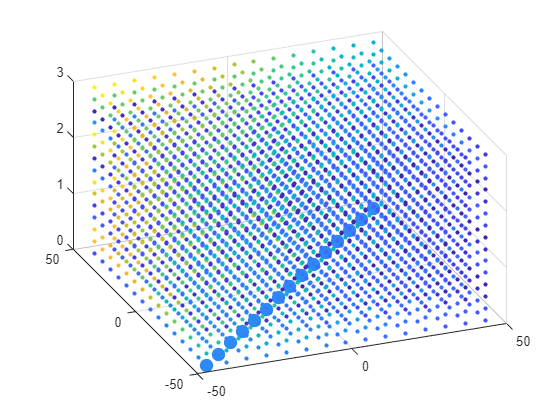

% Initialize parameters and other stuff you need
dnum = 15; %10 %25 %50 %75 %100 % some example values (use lowest value 
                                 % for testing

% Define the range for each shape mode and other system parameters:
aa = 1;                                 % leg to half link length ratio
ll = 1;                                 % half link length

ank = pi/4;                            % symmetric leg ankle limit
sank = [rad2deg(0),rad2deg(90)];                       % sprawl limits (ordered; make sure
                                            % they are realistic)
% the standard limits for the system to go from a vertical line to a
% horizontal line would be 0degs to 90 degs -- but this scales the vector
% field poorly.

am = linspace(-ank,ank,dnum);          % right leg angle
ap = am;                               % left leg angle
g = linspace(sank(1),sank(2),dnum);    % sprawl angle

[am,ap,g] = meshgrid(am,ap,g);         % create a 3D grid of values in each 
                                       % shape

% Initialize containers:
A_b_sweep = nan(dnum,dnum,dnum,size(A_b,1),size(A_b,2));
A_a_sweep = A_b_sweep;
% ksq_sweep = nan(dnum,dnum,dnum);

% Compute the ksq_sweep outside the loop:
ksq_sweep = ksq_12_func(aa,ll,am,ap,g);

% Perform the sweep:
for i = 1:dnum
    for j = 1:dnum
        parfor k = 1:dnum
            
%             ksq_sweep(i,j,k) = ksq_12_func(aa,ll,a1(i,j,k),a2(i,j,k),g(i,j,k));
            % We store the inf and nans we get, and store that information
            % for later use.
            A_b_sweep(i,j,k,:,:) = A_b_func(aa,ll,am(i,j,k),ap(i,j,k),g(i,j,k));
            A_a_sweep(i,j,k,:,:) = A_a_func(aa,ll,am(i,j,k),ap(i,j,k),g(i,j,k));

        end
    end
end

% Let's isolate the sprawl velocity corresponding to each shape mode direction:
s1_b = reshape(A_b_sweep(:,:,:,4,1),[dnum,dnum,dnum]); 
s2_b = reshape(A_b_sweep(:,:,:,4,2),[dnum,dnum,dnum]); s3_b = zeros(size(s2_b));
s1_a = reshape(A_a_sweep(:,:,:,4,1),[dnum,dnum,dnum]); 
s2_a = reshape(A_a_sweep(:,:,:,4,2),[dnum,dnum,dnum]); s3_a = zeros(size(s2_a));
x1_b = reshape(A_b_sweep(:,:,:,1,1),[dnum,dnum,dnum]);

% Vector field line thickness:
qW = 2;
% Define any colors if you have any

% Get the indices for the vector field that aren't inf~~~~~~~~~~~~~~~~~~~~~~
idx = ~isinf(s1_b)&~isinf(s2_b); % this is forcing me to set some realistic 
                                 % limits on gamma
% idx = ~isinf(s1_b)&~isinf(s2_b)&g==deg2rad(45); % we can see more arrows

% Get the indices at which we have infinite value to get a sense for
% bifurcation zone -- has to align with the surface "folding" zone
idx_bif = s1_b==0 | s2_b==0 | isinf(s1_b) | isinf(s2_b);

% % % Time to plot some results -- plot the sprawl change rate as a
% function of shape-space and also the 
% % figure() % the first vector field
% % quiver3(rad2deg(a1(idx)),rad2deg(a2(idx)),rad2deg(g(idx)),...
% %     s1_b(idx),s2_b(idx),s3_b(idx),'LineWidth',qW);
% % view(-45,20);

a11 = reshape(rad2deg(am(idx)),1,numel(rad2deg(am(idx))));
a22 = reshape(rad2deg(ap(idx)),1,numel(rad2deg(ap(idx))));
gg = reshape(rad2deg(g(idx)),1,numel(rad2deg(g(idx))));
kk = reshape(ksq_sweep,1,numel(ksq_sweep));

a11_bif = reshape(rad2deg(am(idx_bif)),1,numel(rad2deg(am(idx_bif))));
a22_bif = reshape(rad2deg(ap(idx_bif)),1,numel(rad2deg(ap(idx_bif))));
gg_bif = reshape(rad2deg(g(idx_bif)),1,numel(rad2deg(g(idx_bif))));
kk_bif = reshape(ksq_sweep(idx_bif),1,numel(ksq_sweep(idx_bif)));

figure()
scatter3(a11,a22,gg,10,kk,'filled');
view(-45,20); hold on;
scatter3(a11_bif,a22_bif,gg_bif,100,kk_bif,'filled');

It is hard to visualize the effects of the sprawl solution folding on itself; hence, I take this as an opportunity to step back and reframe this problem of expanding the configuration space of the robot and introducing sprawl through a story-driven narrative.

# Exploring contact-switching system designs compatible with level-2, pin-contact submanifolds

## Case 1: mult-disk, level-2,

As shown in the previous paper, single disk-centered contact switching systems come with this inherent issue of inability to access the level-2, contact submanifolds where more than one feet is in contact and this is achieved by moving the legs to separate disks. We shall now consider one such system; a three-link system with the first and third link as pin-contacting legs, and the middle link is the body of the system. Consider the figure before for SE(2) frames and system description.

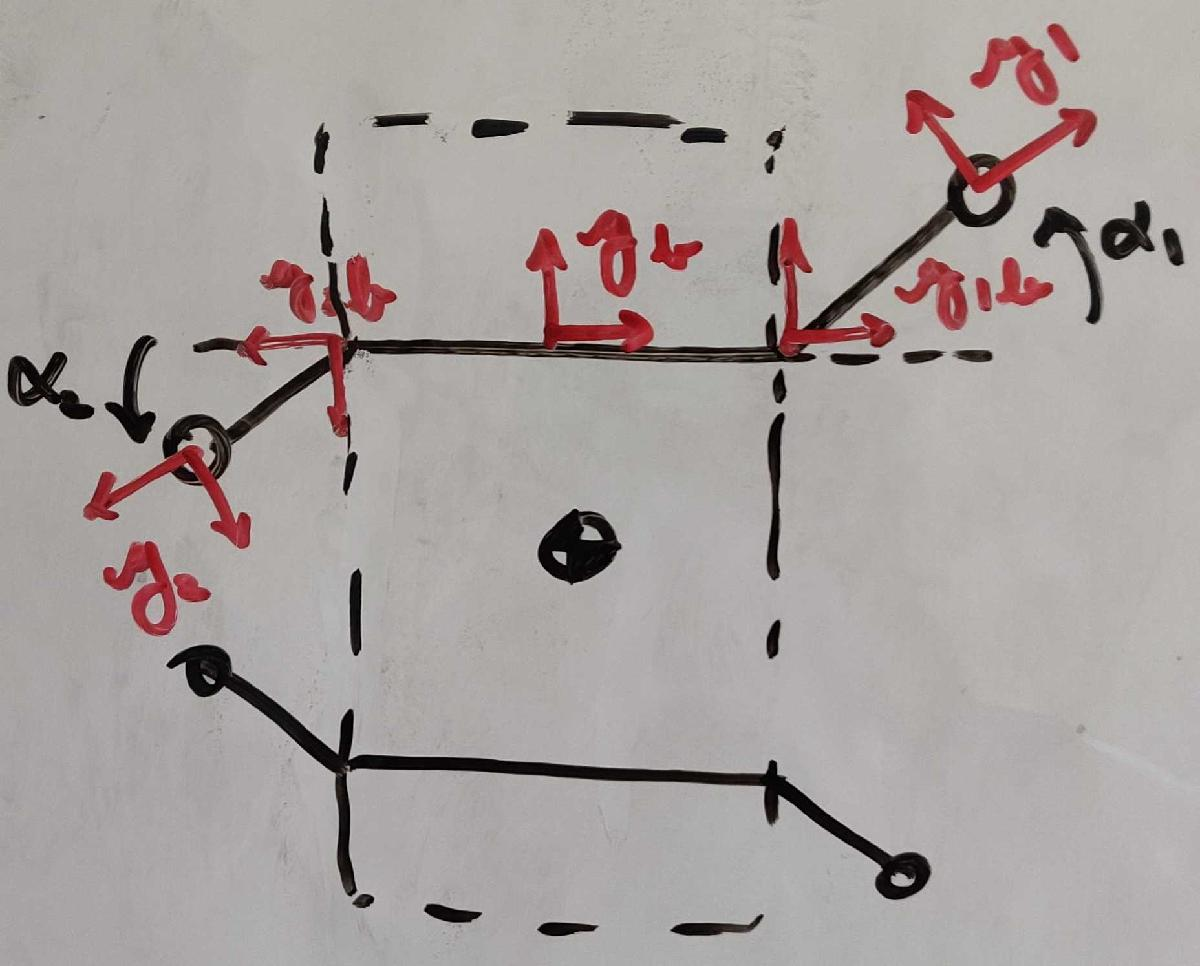

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';

Now, let's make sure that the workspaces of the legs don't intersect each other. Make the lateral distance between the legs '2l', and the vertical distance between leg pairs 12 and 34 as also 2l; making the legs on the same side of the body not have intersecting workspaces and makes the body a square with the leg bases at each corner; note that the legs on the contra-lateral sides of the body have their workspaces mirrored like in any robotic system, **prioritizing forward motion**.

syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

% 12b is the base frame at the center of the link connecting legs 1 and 2.
% Similarly, for 34b as well.

h_b__12b = [0, l, 0]';
h_b__34b = [0, -l, 0]';


h_12b__1b = [l, 0, 0]';
h_12b__2b = [-l, 0, pi]';
h_34b__3b = [-l, 0, pi]';
h_34b__4b = [l, 0, 0]';

syms alpha_i
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__i = AdjInvMap(h_ib__i);
J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__j_func = matlabFunction(zeros(3,3), 'Vars', [a, l, alpha_i]);
% Jacobian to a leg from a different leg base will always be zero.

% Need to find a better, less repetitive way of doing this; the first
% thought would be to define loop iteration based strings and convert them
% to a variable name -- CHECK OUT "genvarname"
h_1b__1 = h_ib__i_func(a,l,alpha_1);
h_2b__2 = h_ib__i_func(a,l,alpha_2);
h_3b__3 = h_ib__i_func(a,l,alpha_3);
h_4b__4 = h_ib__i_func(a,l,alpha_4);

J_1b__1 = AdjInvMap(h_1b__1);
J_2b__2 = AdjInvMap(h_2b__2);
J_3b__3 = AdjInvMap(h_3b__3);
J_4b__4 = AdjInvMap(h_4b__4);

J_1b__2 = J_ib__j_func(a,l,alpha_1);
J_1b__3 = J_ib__j_func(a,l,alpha_1);
J_1b__4 = J_ib__j_func(a,l,alpha_1);

J_2b__1 = J_ib__j_func(a,l,alpha_2);
J_2b__3 = J_ib__j_func(a,l,alpha_2);
J_2b__4 = J_ib__j_func(a,l,alpha_2);

J_3b__1 = J_ib__j_func(a,l,alpha_3);
J_3b__2 = J_ib__j_func(a,l,alpha_3);
J_3b__4 = J_ib__j_func(a,l,alpha_3);

J_4b__1 = J_ib__j_func(a,l,alpha_4);
J_4b__2 = J_ib__j_func(a,l,alpha_4);
J_4b__3 = J_ib__j_func(a,l,alpha_4);

h_b__1b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b));
h_b__2b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b));
h_b__3b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b));
h_b__4b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b));

h_b__1 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1));
h_b__2 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2));
h_b__3 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3));
h_b__4 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4));

J_b__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1)));
J_b__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2)));
J_b__3 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3)));
J_b__4 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4)));

% Get the full Jacobian:
J_1_full = [J_b__1,...
    J_1b__1*theta_circ, J_2b__1*theta_circ, J_3b__1*theta_circ, J_4b__1*theta_circ];
J_2_full = [J_b__2,...
    J_1b__2*theta_circ, J_2b__2*theta_circ, J_3b__2*theta_circ, J_4b__2*theta_circ];
J_3_full = [J_b__3,...
    J_1b__3*theta_circ, J_2b__3*theta_circ, J_3b__3*theta_circ, J_4b__3*theta_circ];
J_4_full = [J_b__4,...
    J_1b__4*theta_circ, J_2b__4*theta_circ, J_3b__4*theta_circ, J_4b__4*theta_circ];

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % TRANSFORM VALIDAITON COMPLETE
% % Let's plot the robot and convince ourselves that the transforms are
% % right.
% base_topbase_x = [0 h_b__12b(1)]; base_topbase_y = [0 h_b__12b(2)];
% base_botbase_x = [0 h_b__34b(1)]; base_botbase_y = [0 h_b__34b(2)];
% 
% topbase_leg1base_x = [h_b__12b(1) h_b__1b(1)]; topbase_leg1base_y = [h_b__12b(2) h_b__1b(2)];
% topbase_leg2base_x = [h_b__12b(1) h_b__2b(1)]; topbase_leg2base_y = [h_b__12b(2) h_b__2b(2)];
% 
% botbase_leg3base_x = [h_b__34b(1) h_b__3b(1)]; botbase_leg3base_y = [h_b__34b(2) h_b__3b(2)];
% botbase_leg4base_x = [h_b__34b(1) h_b__4b(1)]; botbase_leg4base_y = [h_b__34b(2) h_b__4b(2)];
% 
% legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
% legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
% legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
% legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];
% 
% base_topbase_x = double(subs(base_topbase_x,l,1)); base_topbase_y = double(subs(base_topbase_y,l,1));
% base_botbase_x = double(subs(base_botbase_x,l,1)); base_botbase_y = double(subs(base_botbase_y,l,1));
% 
% topbase_leg1base_x = double(subs(topbase_leg1base_x,l,1)); topbase_leg1base_y = double(subs(topbase_leg1base_y,l,1));
% topbase_leg2base_x = double(subs(topbase_leg2base_x,l,1)); topbase_leg2base_y = double(subs(topbase_leg2base_y,l,1));
% 
% botbase_leg3base_x = double(subs(botbase_leg3base_x,l,1)); botbase_leg3base_y = double(subs(botbase_leg3base_y,l,1));
% botbase_leg4base_x = double(subs(botbase_leg4base_x,l,1)); botbase_leg4base_y = double(subs(botbase_leg4base_y,l,1));
% 
% legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,alpha_1],[1,1,0])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,alpha_1],[1,1,0]));
% legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,alpha_2],[1,1,0])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,alpha_2],[1,1,0]));
% legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,alpha_3],[1,1,0])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,alpha_3],[1,1,0]));
% legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,alpha_4],[1,1,0])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,alpha_4],[1,1,0]));
% 
% figure()
% 
% plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
% hold on; grid on;
% plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
% plot(topbase_leg1base_x,topbase_leg1base_y,'k','LineWidth',2.0);
% plot(topbase_leg2base_x,topbase_leg2base_y,'k','LineWidth',2.0);
% plot(botbase_leg3base_x,botbase_leg3base_y,'k','LineWidth',2.0);
% plot(botbase_leg4base_x,botbase_leg4base_y,'k','LineWidth',2.0);
% 
% plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
% plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
% plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
% plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);
% legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
% legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
% legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
% legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];
% legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,alpha_1],[1,1,pi/3])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,alpha_1],[1,1,pi/3]));
% legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,alpha_2],[1,1,pi/3])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,alpha_2],[1,1,pi/3]));
% legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,alpha_3],[1,1,pi/3])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,alpha_3],[1,1,pi/3]));
% legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,alpha_4],[1,1,pi/3])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,alpha_4],[1,1,pi/3]));
% figure()
% plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
% hold on; grid on;
% plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
% plot(topbase_leg1base_x,topbase_leg1base_y,'k','LineWidth',2.0);
% plot(topbase_leg2base_x,topbase_leg2base_y,'k','LineWidth',2.0);
% plot(botbase_leg3base_x,botbase_leg3base_y,'k','LineWidth',2.0);
% plot(botbase_leg4base_x,botbase_leg4base_y,'k','LineWidth',2.0);
% plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
% plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
% plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
% plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);

C = [eye(2,2),zeros(2,1)];

pfaff_12 = [C*J_1_full;
            C*J_2_full];
pfaff_23 = [C*J_2_full;
            C*J_3_full];
pfaff_34 = [C*J_3_full;
            C*J_4_full];
pfaff_41 = [C*J_4_full;
            C*J_1_full];
pfaff_13 = [C*J_1_full;
            C*J_3_full];
pfaff_24 = [C*J_2_full;
            C*J_4_full];
% Compute the local connection for the 12 submanifold -- justy gives inf
% % simplify(pfaff_12(:,1:3)\pfaff_12(:,4:end),'Steps',10)
% % simplify(pfaff_23(:,1:3)\pfaff_23(:,4:end),'Steps',10)
% % simplify(pfaff_34(:,1:3)\pfaff_34(:,4:end),'Steps',10)
% % simplify(pfaff_41(:,1:3)\pfaff_41(:,4:end),'Steps',10)
% % simplify(pfaff_13(:,1:3)\pfaff_13(:,4:end),'Steps',10)
% % simplify(pfaff_24(:,1:3)\pfaff_24(:,4:end),'Steps',10)

Since, no connection exists, let us look at the formulation for squared inter-leg distance to glean some insight into why this is the case.

ksq_12 = simplify((C*(h_b__2 - h_b__1))'*C*(h_b__2 - h_b__1),'Steps',10)

$$ksq\_12 = l^{2}\,{\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{2}\right)\right)}^{2}$$

ksq_23 = simplify((C*(h_b__3 - h_b__2))'*C*(h_b__3 - h_b__2),'Steps',10)

$$ksq\_23 = l^{2}\,{\left(a\,\sin\left(\alpha_{3}\right)-a\,\sin\left(\alpha_{2}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{3}\right)\right)}^{2}$$

ksq_34 = simplify((C*(h_b__4 - h_b__3))'*C*(h_b__4 - h_b__3),'Steps',10)

$$ksq\_34 = l^{2}\,{\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{3}\right)+\sin\left(\alpha_{4}\right)\right)}^{2}$$

ksq_41 = simplify((C*(h_b__1 - h_b__4))'*C*(h_b__1 - h_b__4),'Steps',10)

$$ksq\_41 = l^{2}\,{\left(a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{4}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{4}\right)\right)}^{2}$$

ksq_13 = simplify((C*(h_b__3 - h_b__1))'*C*(h_b__3 - h_b__1),'Steps',10)

$$ksq\_13 = {\left(l\,\left(a\,\cos\left(\alpha_{1}\right)+1\right)+l\,\left(a\,\cos\left(\alpha_{3}\right)+1\right)\right)}^{2}+{\left(l\,\left(a\,\sin\left(\alpha_{1}\right)+1\right)+l\,\left(a\,\sin\left(\alpha_{3}\right)+1\right)\right)}^{2}$$

ksq_24 = simplify((C*(h_b__4 - h_b__2))'*C*(h_b__4 - h_b__2),'Steps',10)

$$ksq\_24 = {\left(l\,\left(a\,\cos\left(\alpha_{2}\right)+1\right)+l\,\left(a\,\cos\left(\alpha_{4}\right)+1\right)\right)}^{2}+{\left(l\,\left(a\,\sin\left(\alpha_{2}\right)-1\right)+l\,\left(a\,\sin\left(\alpha_{4}\right)-1\right)\right)}^{2}$$

ksq_12_func = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2]);

Let's just plot this as a function of the shape space in the form of a heat-map to see if there are tractable connection regions.

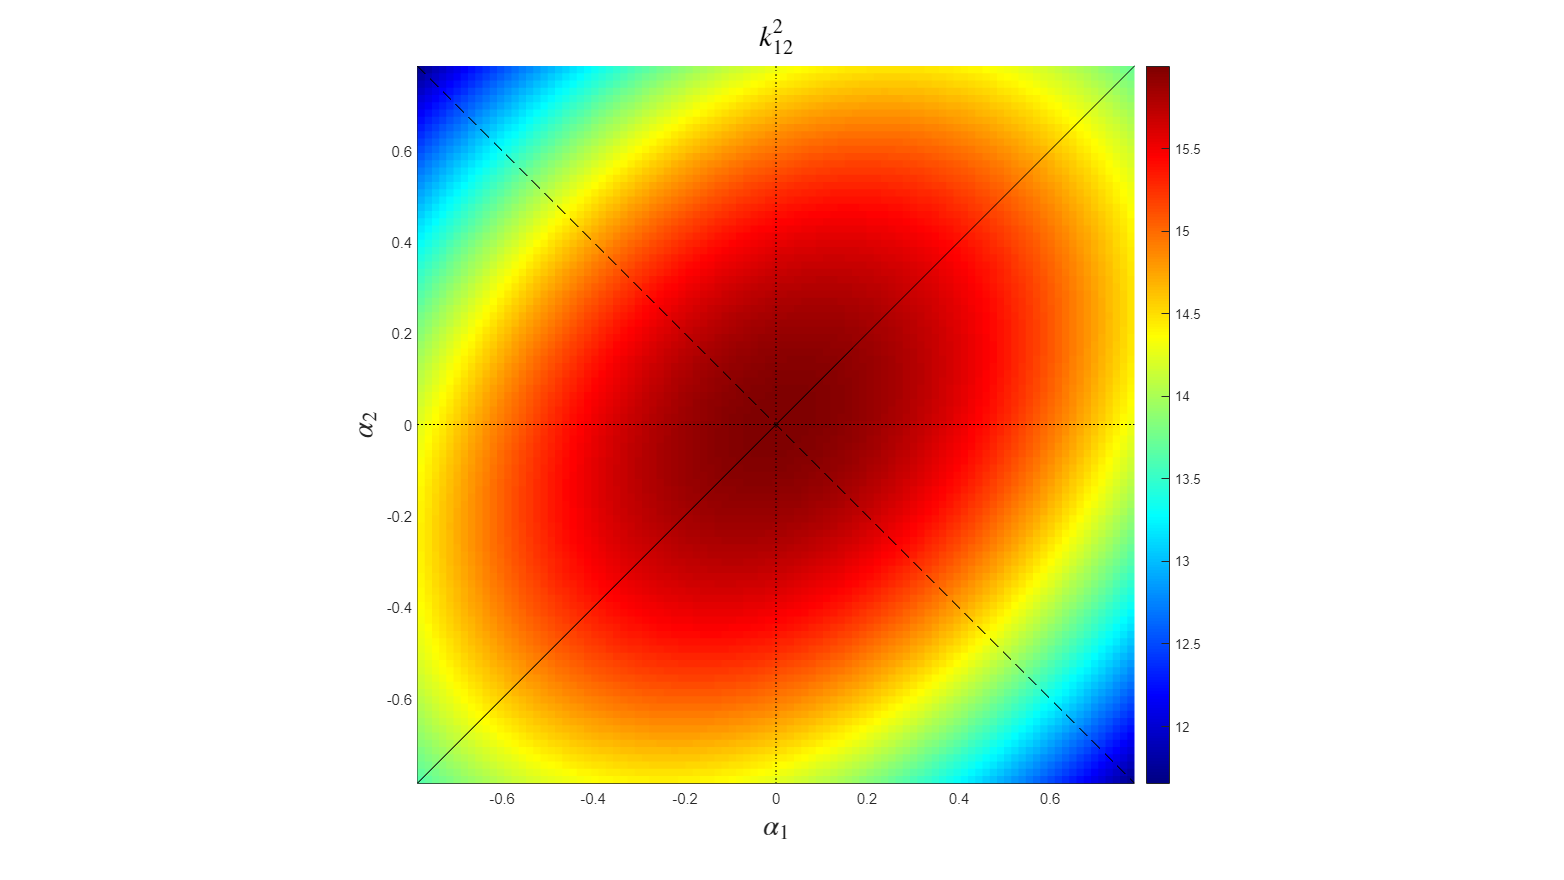

dnum = 100;

aa = 1;                                 
ll = 1;                                 

ank = pi/4;                    

xx = linspace(-ank,ank,dnum);          
yy = xx;

[am,ap] = meshgrid(xx,yy);

ksq_sweep = ksq_12_func(aa, ll, am, ap);
ksq_M = ksq_12_func(aa, ll, xx, yy);
ksq_m = ksq_12_func(aa, ll, xx, -yy);
ksq_x = ksq_12_func(aa, ll, xx, 0*yy);
ksq_y = ksq_12_func(aa, ll, 0*xx, yy);

% Plot the inter-leg distance landscape
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
surf(am,ap,ksq_sweep,'EdgeColor','none'); % ,'EdgeColor','none'
axis equal tight; hold on; view(2);
colormap(jet); % use this colormap
colorbar(); % show the colorbar
line(xx,yy,ksq_M,'Color','k','LineStyle','-'); % major axis % ,'LineWidth',1.2
line(xx,-yy,ksq_m,'Color','k','LineStyle','--');% minor axis % ,'LineWidth',1.2
line(0*xx,yy,ksq_y,'Color','k','LineStyle',':');% alpha_j axis % ,'LineWidth',1.2
line(xx,0*yy,ksq_x,'Color','k','LineStyle',':');% alpha_i-axis % ,'LineWidth',1.2
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

Seems like the inter-leg distance is definitely changing as we move along any direction, but there are level-set contours that from a loop in the shape space. This should be the same for all leg pairs. Hence, to expand our shape-space, let's try adding compliance through a contra-laterally symmetric, closed kinematic chain -- half a sarrus linkage! **Disclaimer: **You also need to add an out of plane chain to constrain the robot shape...

Also, the pseudo-inverse should work, let's do some additional digging.

### Overconstrained, inconsistent 4x3 subblock

Adding some analysis on the pseudoinverse of the overconstrained 4x3 sub-block (from the left) which happens to be inconsistent.

s_12 = pfaff_12(:,1:3); s_23 = pfaff_23(:,1:3); s_34 = pfaff_34(:,1:3); s_41 = pfaff_41(:,1:3); % adjacent legs
s_13 = pfaff_13(:,1:3); s_24 = pfaff_24(:,1:3); % diagonally opposite legs

As checked in the previous section, both '\' and pinv has failed us due to some symbolic engine issues; hence, we shall check if the sub-blocks are full column rank (needed to implement the inverse) and then implement a pseudoinverse (Moore-Penrose Inverse) manually.

% Let's check the column rank with rank command and also check the row
% reduced echelon form as proof:
rank(s_12)

ans = 3

rref(s_12)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

% Uncomment the functions below to obtain the approximated, least squares
% minimum local connection for this system.

The rank and echelon form reveal that the sub-block is full rank, but still the pinv and backlash command are causing issues for us. Let's make sure this is the case for all other contact submanifolds as well!

% rank(s_23)
% rref(s_23)
% rank(s_34)
% rref(s_34)
% rank(s_41)
% rref(s_41)
% rank(s_13)
% rref(s_13)
% rank(s_24)
% rref(s_24)
% % Uncomment above to verify the full column rank requirement to take the
% pseudoinverse.

They too work out! Now, we are good to take the pseudoinverse (and simplify the result)!

% s_12p = simplify(transpose(s_12)*s_12*transpose(s_12));
% s_23p = simplify(transpose(s_23)*s_23*transpose(s_23));
% s_34p = simplify(transpose(s_34)*s_34*transpose(s_34));
% s_41p = simplify(transpose(s_41)*s_41*transpose(s_41));
% s_13p = simplify(transpose(s_13)*s_13*transpose(s_13));
% s_24p = simplify(transpose(s_24)*s_24*transpose(s_24));

Get the approximate, least squares, local connection ${}^+\!\! A$ for each two-foot contact submanifold.

A_1_12 = simplify(transpose(s_12)*s_12*transpose(s_12)*pfaff_12(:,4:end), 'Steps', 10)

A_1_23 = simplify(transpose(s_23)*s_23*transpose(s_23)*pfaff_23(:,4:end), 'Steps', 10)

A_1_34 = simplify(transpose(s_34)*s_34*transpose(s_34)*pfaff_34(:,4:end), 'Steps', 10)

A_1_41 = simplify(transpose(s_41)*s_41*transpose(s_41)*pfaff_41(:,4:end), 'Steps', 10)

A_1_13 = simplify(transpose(s_13)*s_13*transpose(s_13)*pfaff_13(:,4:end), 'Steps', 10)

A_1_24 = simplify(transpose(s_24)*s_24*transpose(s_24)*pfaff_24(:,4:end), 'Steps', 10)

% UNCOMMENT BELOW IF YOU"VE MADE CHANGES to the the squared inter-leg
% distance or anything else.
% Save the data needed for the next section
save('case_1_kinematics','ksq_12','ksq_23','ksq_34','ksq_41','ksq_13','ksq_24',...
                        'pfaff_12','pfaff_23','pfaff_34','pfaff_41','pfaff_13','pfaff_24',...
                        'A_1_12','A_1_23','A_1_34','A_1_41','A_1_13','A_1_24')

### Motion Planning

#### Designing gaits based on the inter-leg distance constraints (for legs 1 and 2)

Recall that two legs are pinned and hence, the distance between them is conserved (doesn't change with time) - check the $k^2$ plot above. In order to remain in the level-sets of $k^2$, we need to obtain this relationship between the two legs pinned to the ground. On a quick look, the major and minor axis of the ellipsoidal gait that satisfies the $k^2$ level set conditions are $\alpha_i =\alpha_j$ and $\alpha_i =-\alpha_j$. Let's obtain the exact relationship below by taking the gradient of $k^2$.


$$\frac{d k^2 (\alpha_i, \alpha_j)}{dt} = \frac{\partial k^2}{\partial \alpha_i} \dot{\alpha_i} + \frac{\partial k^2}{\partial \alpha_j} \dot{\alpha_j} = 0, \\
\dot{\alpha_j} = -  \frac{\partial k^2}{\partial \alpha_i}  \biggl( \frac{\partial k^2}{\partial \alpha_j} \biggr)^{-1} \dot{\alpha_i}$$


We can simplify this further by removing the time-dependence,


$$\frac{\partial{\alpha_j}}{\partial{\alpha_i}} = -  \frac{\partial k^2}{\partial \alpha_i}  \biggl( \frac{\partial k^2}{\partial \alpha_j} \biggr)^{-1}$$


But, since we have ellipsoidal level-sets (need to find a way to prove this later!), we can rotate the gradient by $\pm90^{\circ}$ to get a CCW or CW gait. This is the gradient for $k^2$ surface,


$$$\nabla k^2 = \left(\begin{array}{c}
\frac{\partial k^2}{\partial \alpha_i} \\
\frac{\partial k^2}{\partial \alpha_j}
\end{array}\right)$$$


The derivative in the shape-space for the iso-$k^2$ surface with a CCW gait is given by,


$$d\hat{\phi}_{ij} = R{\left(\frac{\pi}{2}\right)} . \nabla k^2 \,\,\, \\
\Rightarrow d\hat{\phi}_{ij} = \left(\begin{array}{c c}
0 & 1 \\
-1 & 0
\end{array}\right) 
\left(\begin{array}{c}
\frac{\partial k^2}{\partial \alpha_i} \\
\frac{\partial k^2}{\partial \alpha_j}
\end{array}\right)$$


Let's compute these CCW +ve and CW -ve gait derivates, and plot some on the iso-$k^2$ surface for $S_{12}$,

% Load the data from the previous section:
load('case_1_kinematics');

% Reinitialize some symbols
syms a l real positive
assume(a<=1);
syms tau real
syms alpha_1 alpha_2 theta real % alpha_3 alpha_4

% Define a rotation matrix for the two dimensional shape-space slice
% rotations
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);
% MAKE SURE TO ROUND THE RESULTS

% Gradient for 12 contact state Ksq
dphi_12 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10)

$$dphi\_12 = \left(\begin{array}{c} 2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\\ -2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right) \end{array}\right)$$

Next, we need to know if we are coming back to the starting position in our gait, and this can be defined based on the phase between our starting point and the origin. Hence, based on this phase, we can define our gait constraints.

% Let's consider the S12 contact state and obtain the gait constraints for
% the same----------------------------------------------------------------
% Squared inter-leg distance function
ksq_12_func = matlabFunction(ksq_12,'Vars',[tau, a, l, alpha_1, alpha_2]);
% 2-element shape slice derivatives for the iso-k^2 level-sets
dphi_12_func = matlabFunction(dphi_12,'Vars',[tau, a, l, alpha_1, alpha_2]);

% Initialize standard parameters
aa = 1;                                 
ll = 1;                                 
ank = pi/4;

% Define the initial conditions for the gait, since we are using atan2, we
% should start from -pi to pi. Hence, the initial condition for the ode
% integration is chosen such that the phase is 0 at the beginning => a1
% is positive and a2 = 0.
a1_0 = 0.1*2*ank; % 20% of the allowble swing range of leg 1
a2_0 = 0; % to make the phase -pi

% ode45 options
options = odeset('Events',@PhaseSijTrigger);
% Let's compute this constrained gait using ode45 -------------------------
% the time span is set between 0 and 5 since we don't know when it is going
% to end.
[t,y,te,ye,ie] = ode45( @(t,y) dphi_12_func(t, aa, ll, y(1), y(2)), [0 5], [a1_0; a2_0], options );

Alright! Now, that we have computed this, let's plot this to see who it looks.

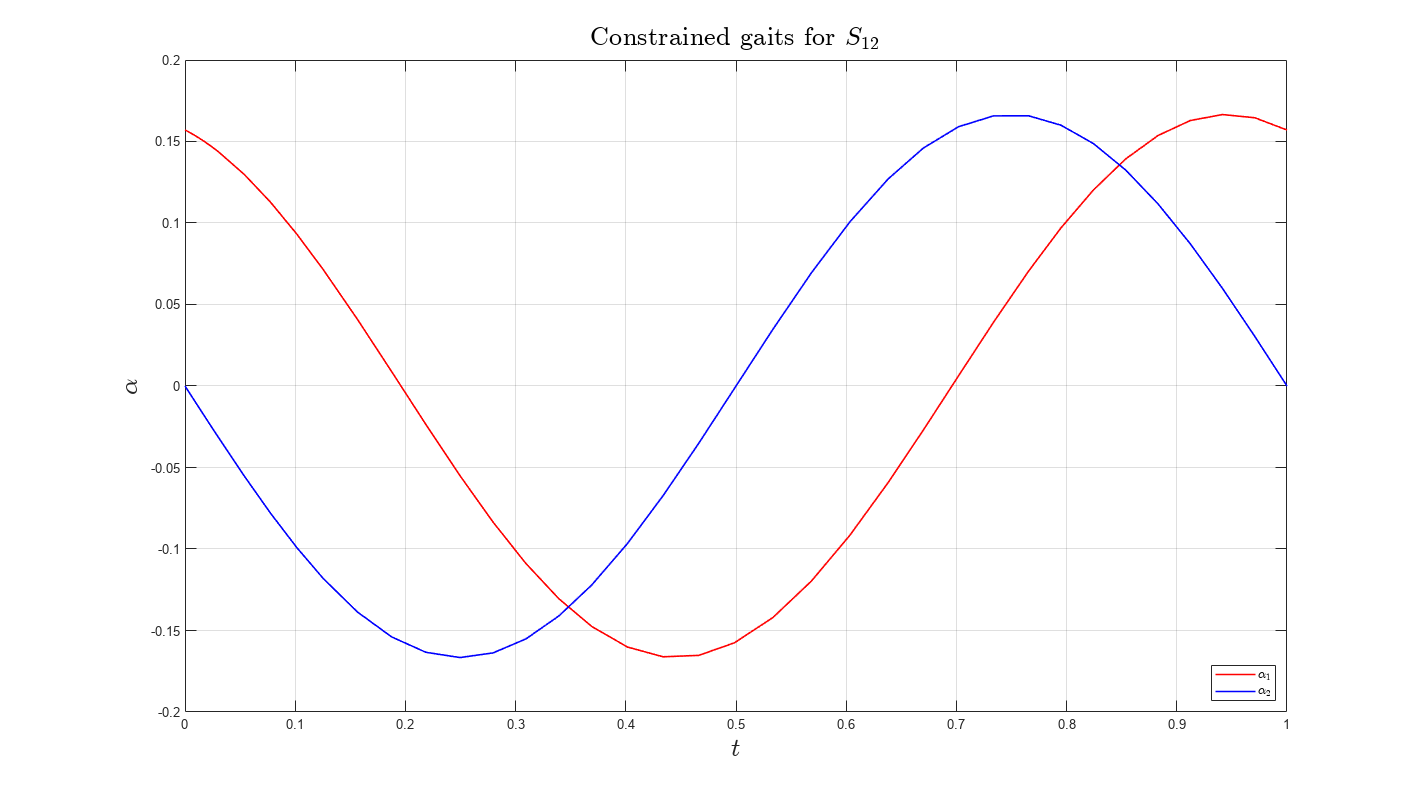

% Rescale the time vectors to end at 1 for the cycle
t = t/t(end); te = te/t(end);
% Plot the computed leg swings
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
plot(t, y(:,1), 'r', 'linewidth', 1.2,'DisplayName','$\alpha_1$'); % alpha_1
hold on; grid on;
plot(t, y(:,2), 'b', 'linewidth', 1.2,'DisplayName','$\alpha_2$'); % alpha_2
% plot(te,ye,'ko','DisplayName','event trigger'); % plot the event trigger point
xlabel('$t$','Interpreter','latex',FontSize=20);
ylabel('$\alpha$','Interpreter','latex',FontSize=20);
title('Constrained gaits for $S_{12}$','Interpreter','latex',FontSize=20);
legend('location','southeast','Interpreter','latex',FontSize=10);

This is great! But, note that this is a numerical approximation and in order to find the **fixed phase between the shape elements**, let's do a sinusoidal fit as shown below,


$$s_1\sin{\left(2 \pi \left(t + \frac{1}{s_2} \right) \right)} + s_3 \\
s_1: \text{amplitude} \\
\frac{2 \pi}{s_2}: \text{phase offset} \\
s_3: \text{DC offset}$$


Each of the parameters above will be estimated for each shape-slice. Note, $s_3$ should be close to 0 in the estimation process (at least for the $S_{12}$ case).

s1 = sinefit(t,y(:,1))

s1 =     0.1666
   -1.4368
    0.0000


s2 = sinefit(t,y(:,2))

s2 =    -0.1666
   -1.0000
   -0.0000


Before we move on to the next, step; let's overlay the fits and see how the compare,

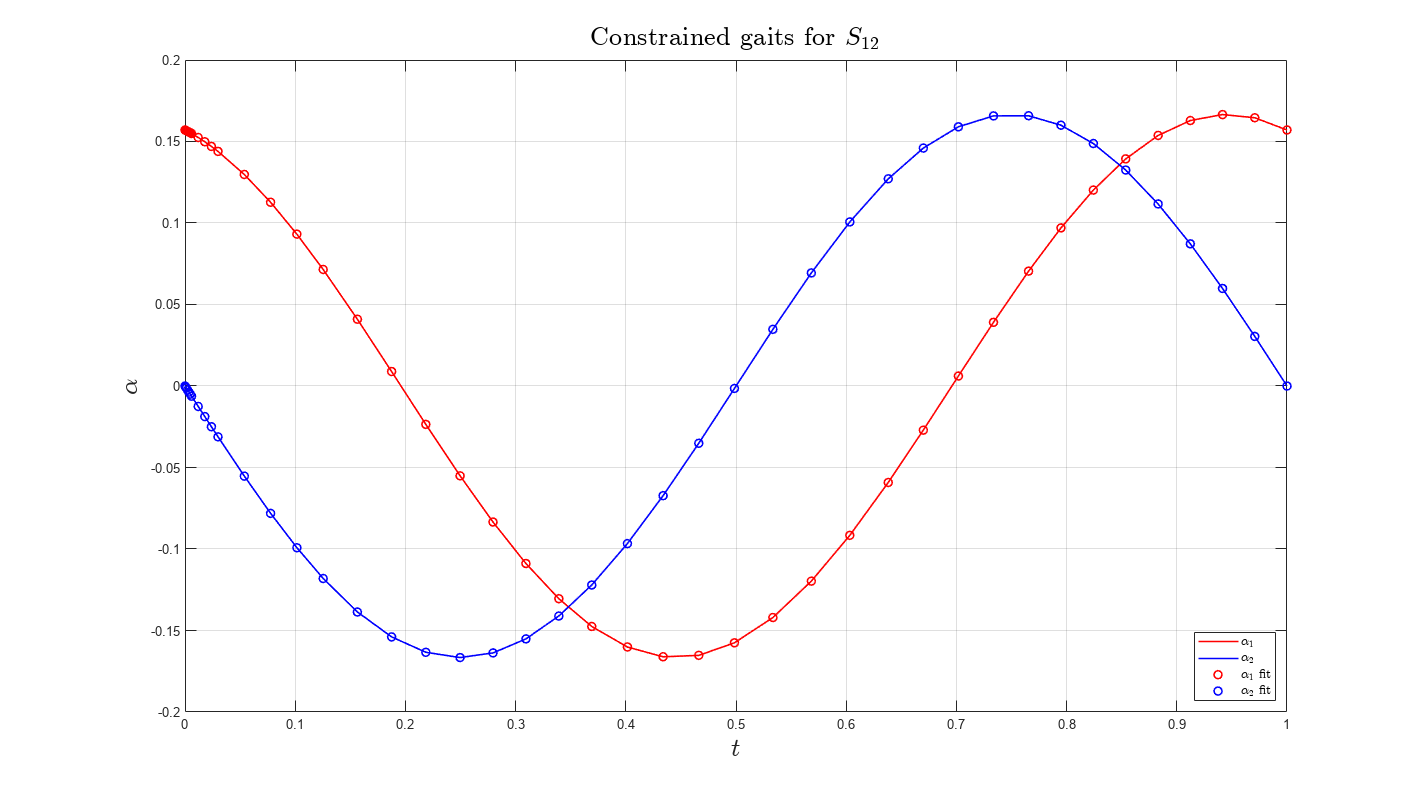

% Let's recreate the fit function
sfit = @(b,x)  b(1).*(sin(2*pi*x + 2*pi/b(2))) + b(3);
% Compute the fit with the time vector
y1 = sfit(s1,t); y2 = sfit(s2,t);
% Recreate the plot
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
plot(t, y(:,1), 'r', 'linewidth', 1.2,'DisplayName','$\alpha_1$'); % alpha_1
hold on; grid on;
plot(t, y(:,2), 'b', 'linewidth', 1.2,'DisplayName','$\alpha_2$'); % alpha_2
plot(t, y1, 'ro', 'linewidth', 1.2,'DisplayName','$\alpha_1$ fit'); % alpha_1
plot(t, y2, 'bo', 'linewidth', 1.2,'DisplayName','$\alpha_2$ fit'); % alpha_2
xlabel('$t$','Interpreter','latex',FontSize=20);
ylabel('$\alpha$','Interpreter','latex',FontSize=20);
title('Constrained gaits for $S_{12}$','Interpreter','latex',FontSize=20);
legend('location','southeast','Interpreter','latex',FontSize=10);

The fit is perfect! Now, we just have to remove the time-dependence and plot it in the corresponding 2-element shape slice. Let's overlay this on top of the iso-$k^2$ surface plot that we did in the last section.

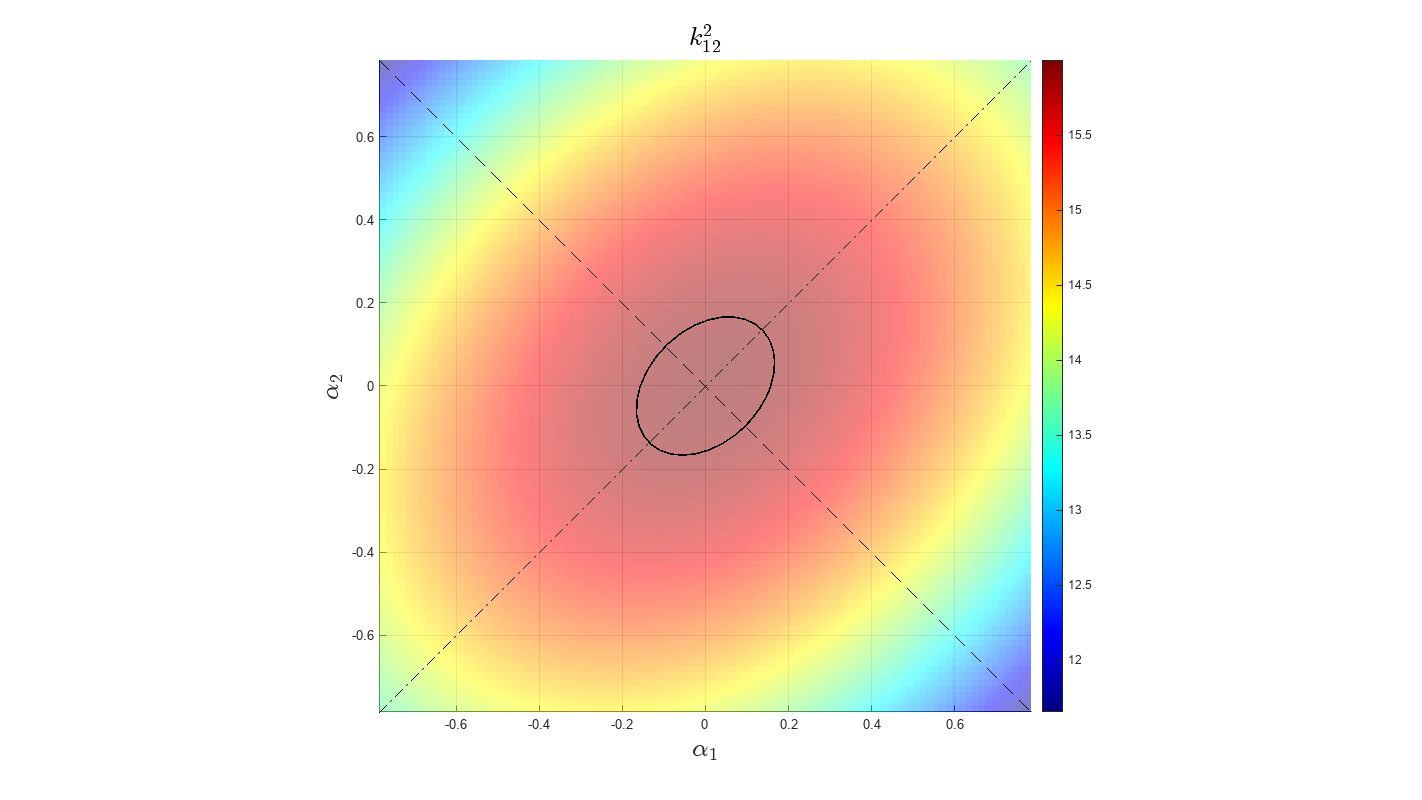

dnum = 100;                
xx = linspace(-ank,ank,dnum);          
yy = xx;
[am,ap] = meshgrid(xx,yy);
ksq_sweep = ksq_12_func(0, aa, ll, am, ap);
ksq_M = ksq_12_func(0, aa, ll, xx, yy);
ksq_m = ksq_12_func(0, aa, ll, xx, -yy);
% ksq_x = ksq_12_func(0, aa, ll, xx, 0*yy);
% ksq_y = ksq_12_func(0, aa, ll, 0*xx, yy);
ksq_phi = ksq_12_func(0, aa, ll, y1, y2);
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
surf(am,ap,ksq_sweep,'EdgeColor','none','FaceAlpha',0.5); % 50% transparency
axis equal tight; hold on; view(2);
colormap(jet);
colorbar();
line(xx,yy,ksq_M,'Color','k','LineStyle','-.');
line(xx,-yy,ksq_m,'Color','k','LineStyle','--');
% line(0*xx,yy,ksq_y,'Color','k','LineStyle',':');
% line(xx,0*yy,ksq_x,'Color','k','LineStyle',':');
line(y1,y2,ksq_phi,'Color', 'k','LineStyle','-', 'LineWidth', 1.2); % constrained gait trajectory
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

Note that this works for all the level-2 submanifolds irrespective of whether the level-sets are self-connected within the shape-space bounds. But, for the submanifolds unconnected level-sets, we need additional machinery to interpret the valid and invalid zones that will help us construct gaits.

#### Automating gait constraint generation for level-2 submanifolds

Let's automate the previous process of obtaining the curve, fitting, and then plotting the ***smallest and largest allowed gaits***. These gait bounds are placed to prevent the system from exceeding the maximum allowable shape-space of the system. This works well for 

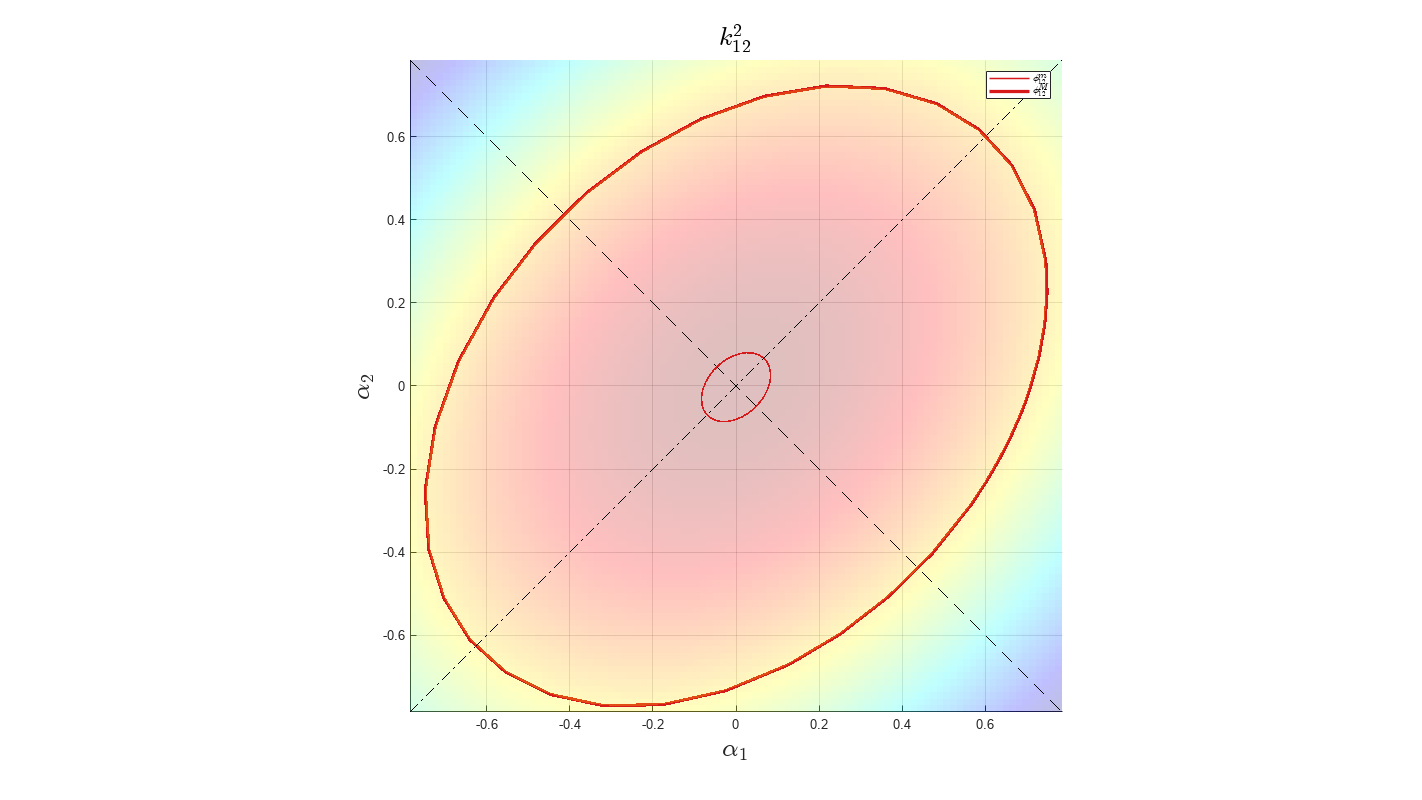

% Repeat some steps from the previous section------------------------------
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms tau real
syms alpha_1 alpha_2 theta alpha_3 alpha_4 real
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);

% NOTE: we should automate the robot kinematics generation and this
% function generation at a later point for an arbitrary n-legged robot.
% Compute the inter-leg distance and gradient for each contact state-------
ksq_12_func = matlabFunction(ksq_12,'Vars',[tau, a, l, alpha_1, alpha_2]);
ksq_23_func = matlabFunction(ksq_23,'Vars',[tau, a, l, alpha_2, alpha_3]);
ksq_34_func = matlabFunction(ksq_34,'Vars',[tau, a, l, alpha_3, alpha_4]);
ksq_41_func = matlabFunction(ksq_41,'Vars',[tau, a, l, alpha_4, alpha_1]);
ksq_13_func = matlabFunction(ksq_13,'Vars',[tau, a, l, alpha_1, alpha_3]);
ksq_24_func = matlabFunction(ksq_24,'Vars',[tau, a, l, alpha_2, alpha_4]);

dphi_12 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10);
dphi_23 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_23,alpha_2) diff(ksq_23,alpha_3)]','Steps',10);
dphi_34 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_34,alpha_3) diff(ksq_34,alpha_4)]','Steps',10);
dphi_41 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_41,alpha_4) diff(ksq_41,alpha_1)]','Steps',10);
dphi_13 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_13,alpha_1) diff(ksq_13,alpha_3)]','Steps',10);
dphi_24 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_24,alpha_2) diff(ksq_24,alpha_4)]','Steps',10);
dphi_12_func = matlabFunction(dphi_12,'Vars',[tau, a, l, alpha_1, alpha_2]);
dphi_23_func = matlabFunction(dphi_23,'Vars',[tau, a, l, alpha_2, alpha_3]);
dphi_34_func = matlabFunction(dphi_34,'Vars',[tau, a, l, alpha_3, alpha_4]);
dphi_41_func = matlabFunction(dphi_41,'Vars',[tau, a, l, alpha_4, alpha_1]);
dphi_13_func = matlabFunction(dphi_13,'Vars',[tau, a, l, alpha_1, alpha_3]);
dphi_24_func = matlabFunction(dphi_24,'Vars',[tau, a, l, alpha_2, alpha_4]);

% Let's package the function requirements----------------------------------
kin = []; % struct

kin.lvl2_cs = [1, 2; % arrange the level-2 contact states
           2, 3;
           3, 4;
           4, 1;
           1, 3;
           2, 4];

kin.ksq_ij{1} = ksq_12_func; % store the functions in a cell array
kin.ksq_ij{2} = ksq_23_func;
kin.ksq_ij{3} = ksq_34_func;
kin.ksq_ij{4} = ksq_41_func;
kin.ksq_ij{5} = ksq_13_func;
kin.ksq_ij{6} = ksq_24_func;

kin.dphi_ij{1} = dphi_12_func;
kin.dphi_ij{2} = dphi_23_func;
kin.dphi_ij{3} = dphi_34_func;
kin.dphi_ij{4} = dphi_41_func;
kin.dphi_ij{5} = dphi_13_func;
kin.dphi_ij{6} = dphi_24_func;

kin.ank = pi/4; % symmetric hip-angle limit of the leg; hence the leg can
                % swing between [-ank, ank]
kin.aa = 1; kin.ll = 1; % body leg-length parameters

kin.circ{1} = (1/255)*[215, 25, 28]; % enter the colors for each contact state
kin.circ{2} = (1/255)*[96, 0, 220];
kin.circ{3} = (1/255)*[44, 123, 182];
kin.circ{4} = (1/255)*[77, 175, 74];
kin.circ{5} = (1/255)*[255, 127, 0];
kin.circ{6} = (1/255)*[231, 41, 138];
% when a state is inactive, let's use back

% Plot the maxmimum and minimum allowed gait for the S_12 submanifold
plotSijwKsq(kin,1,2);

Now, $S_{23}$-- an example of a partially valid submanifold.

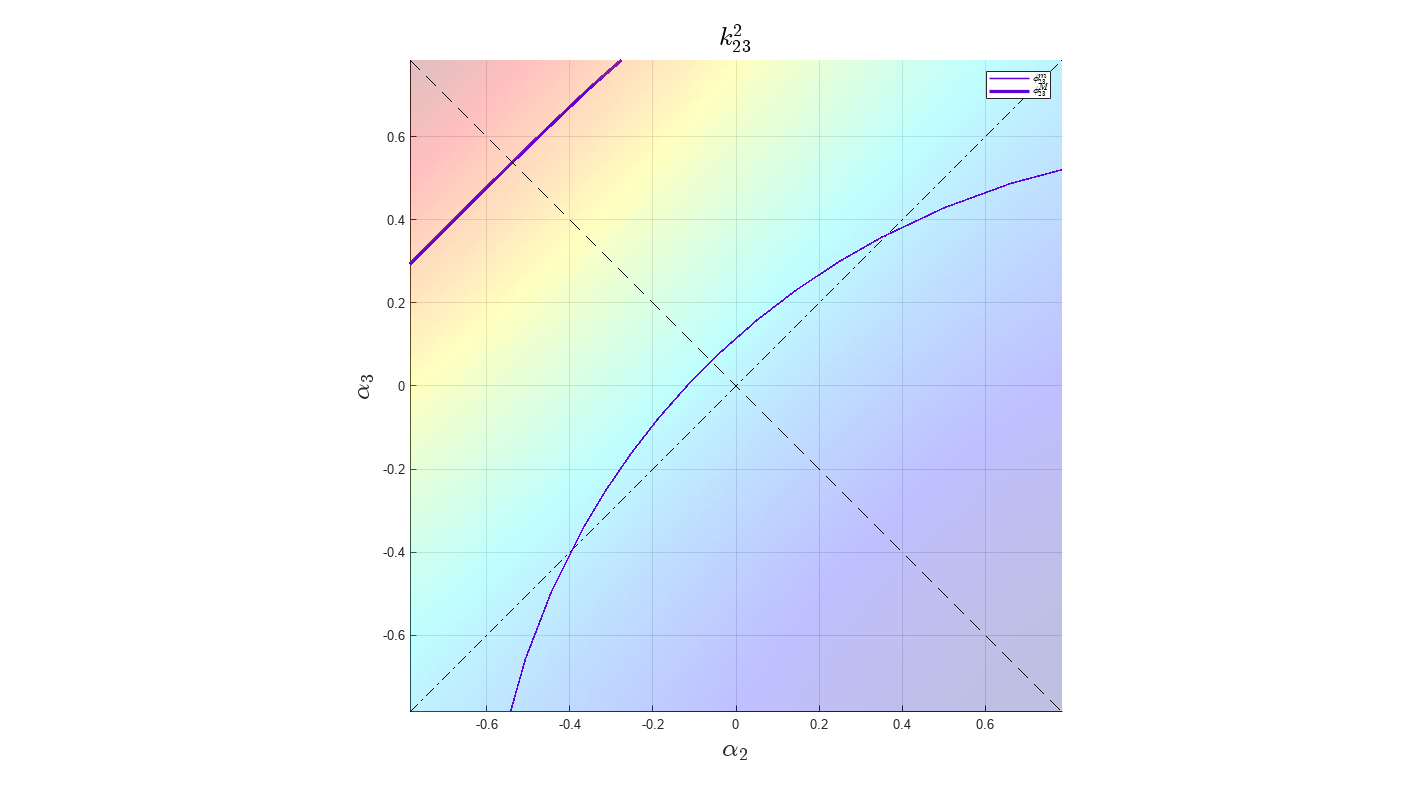

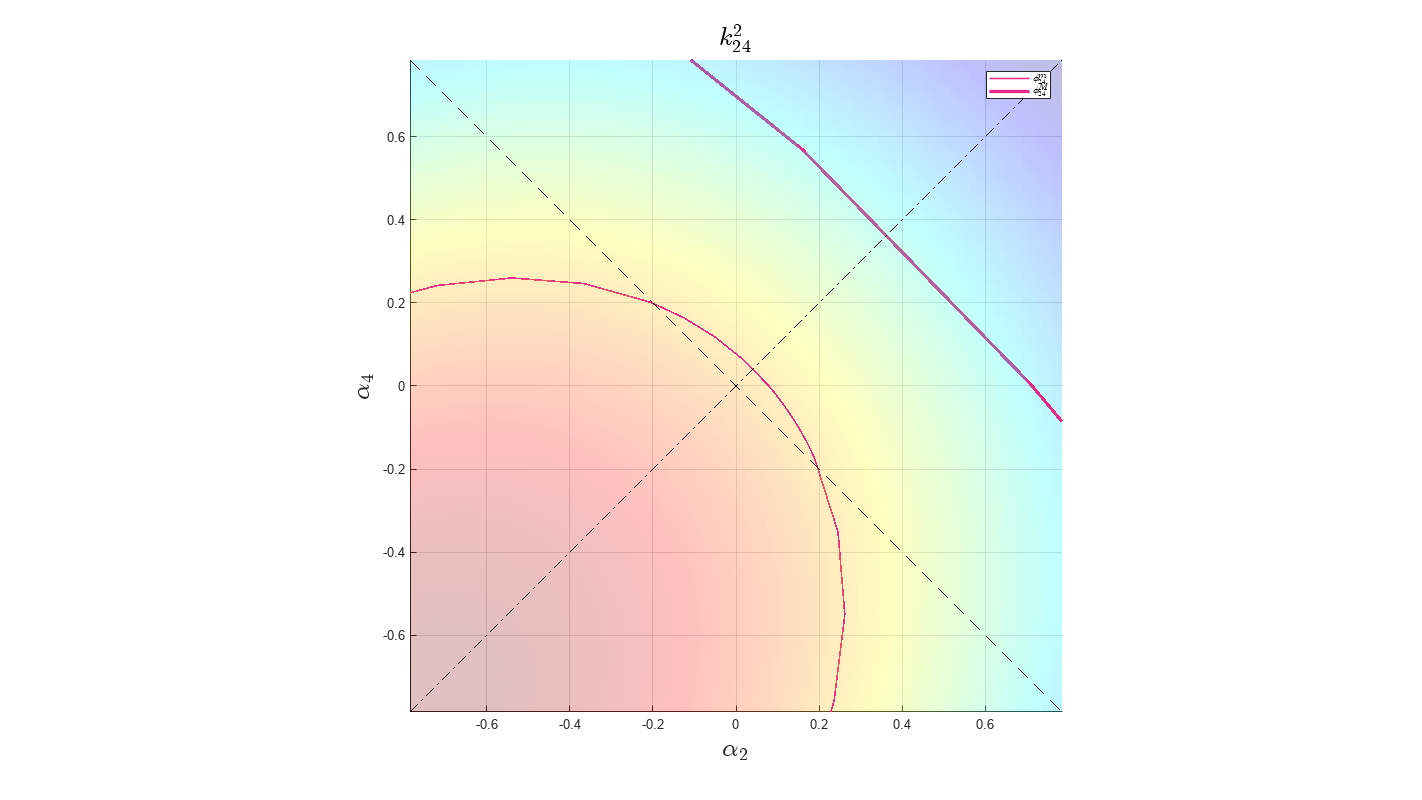

plotSijwKsq(kin,2,3);

plotSijwKsq(kin,2,4);

Seems like, the current rectangular, forward-facing, typical quadruped, **can't handle alternating gaits without slipping (greater than certain leg limits) when outside the shape-space bounds**. Let's plot the $S_{34}$ gait constraints, and obtain the gait constraint values for them both (they should exactly be the same).

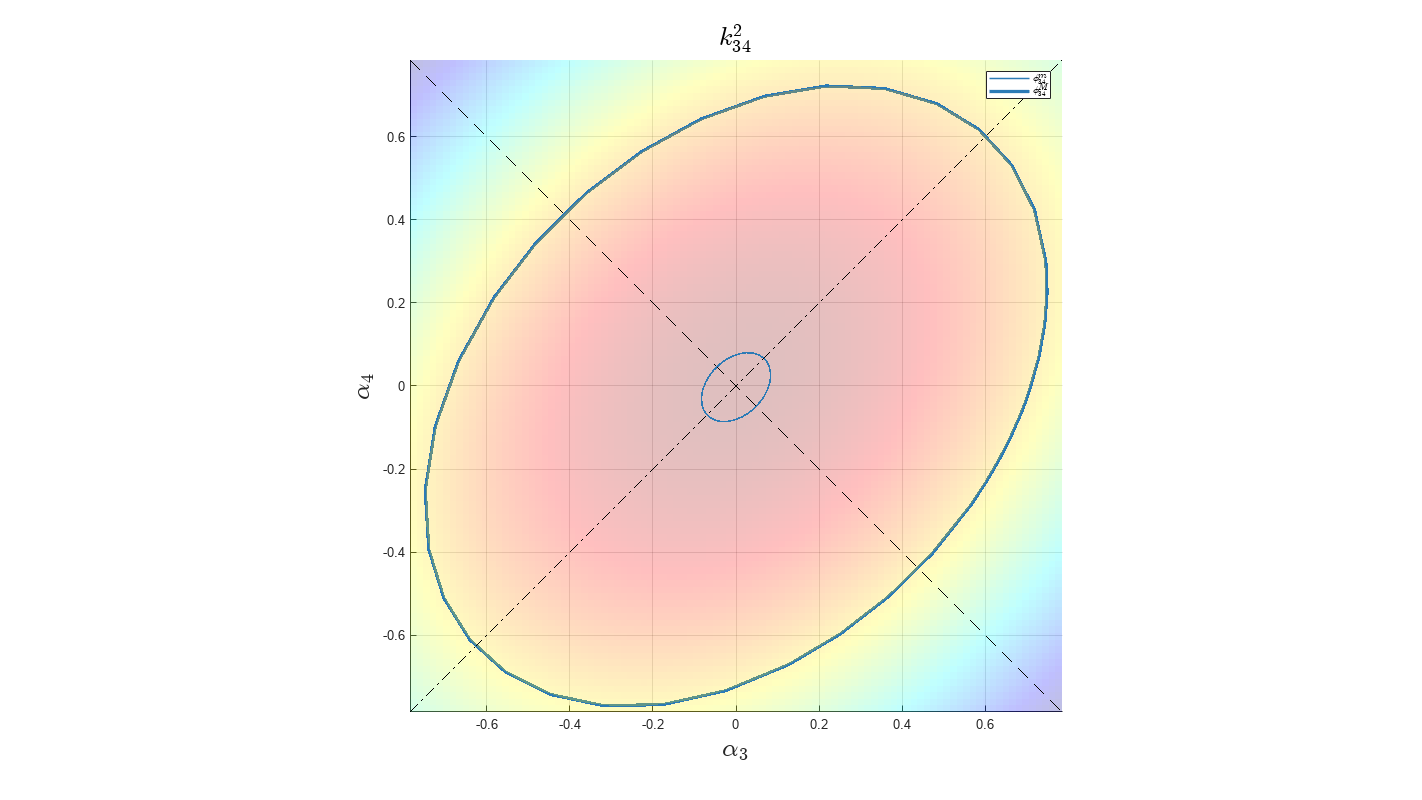

plotSijwKsq(kin,3,4);

Obtain the gait constraint values for these two viable contact states, and save all this information in the kinematics .mat file,

% Compute the gait constraints:
[kin,s1_12,s2_12,~] = gcSij(kin,1,2);
[kin,s3_34,s4_34,~] = gcSij(kin,3,4);
s1_12(1) = kin.mul{1}(2)*s1_12(1); s2_12(1) = kin.mul{1}(2)*s2_12(1); % save the largest gait
s3_34(1) = kin.mul{3}(2)*s3_34(1); s4_34(1) = kin.mul{3}(2)*s4_34(1);
% the amplitude is rescaled to 90% of the swing ankle limit

% Save the data:
save('case_1_kinematics.mat','kin','s1_12','s2_12','s3_34','s4_34','-append');

Now, we can compute the relative phasing between the two shape elements,

% Get the phase of alpha_1
if s1_12(1) < 0
    phase_1 = rad2deg(2*pi/s1_12(2) - pi);
else
    phase_1 = rad2deg(2*pi/s1_12(2));
end
% Get the phase of alpha_2
if s2_12(1) < 0
    phase_2 = rad2deg(2*pi/s2_12(2) - pi);
else
    phase_2 = rad2deg(2*pi/s2_12(2));
end
% Phase of 2 wrt to 1
phase_2w1 = phase_2 - phase_1;
% +-360 (one period offset) if abs value greater than 180 to improve
% readability
if phase_2w1 > 180
    phase_2w1 = phase_2w1 - 360
elseif phase_2w1 < -180
    phase_2w1 = phase_2w1 + 360
end

phase_2w1 = 69.5607

Hence, $\alpha_2$ leads $\alpha_1$ by close to ${70}^{\circ}$. It is the same case between $\alpha_3$ leads $\alpha_4$ in the $S_{34}$ submanifold.

Also, since we have more complicated level-sets action going on, we need to explore this further.

#### Iso-$k^2$ contours and flow

The goal here is to take a vector field based approach to modeling the $k^2$ level-sets and analyze the saddle and center behavior exhibited by our fitted curve.

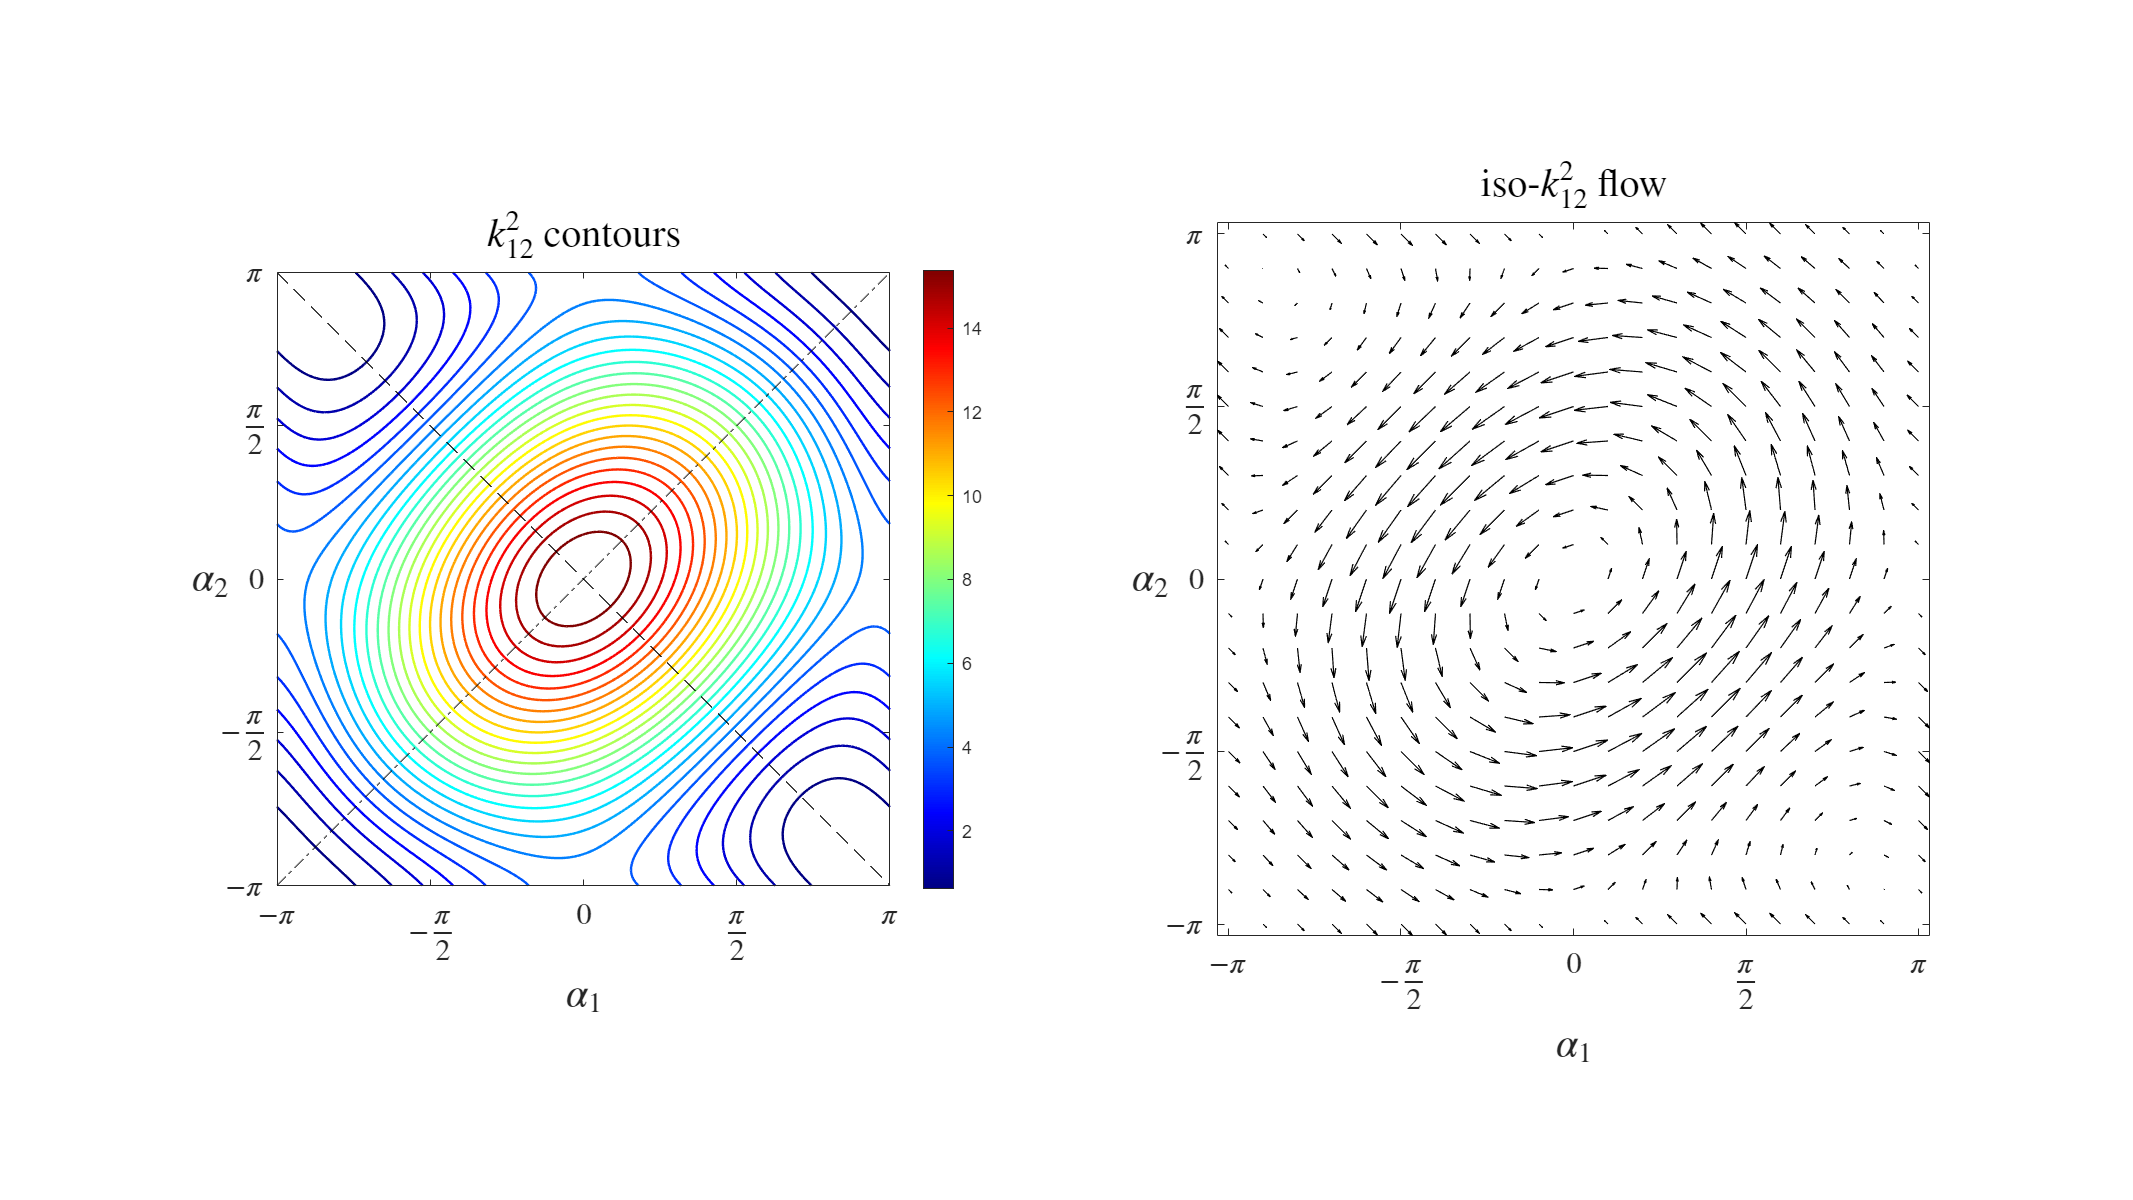

load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms tau real
syms alpha_1 alpha_2 theta real
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);

% Conside the S12 submanifold info    
ksq = kin.ksq_ij{1};
dphi_12 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10);
dphi_x_magscaled = [1,0]*dphi_12; dphi_y_magscaled = [0,1]*dphi_12;
dphi_x_magscaled = matlabFunction(dphi_x_magscaled,'Vars',[a, l, alpha_1, alpha_2]); 
dphi_y_magscaled = matlabFunction(dphi_y_magscaled,'Vars',[a, l, alpha_1, alpha_2]);


% Unlock the joint limits of the system.
ank = 1*pi; % symmetrically defined about 0.
aa = 1; ll = 1;

% Plot info
dnum = 1001; % set this arbitrarily
skipV = 50; % number of points to skip when plotting the vector field
cLvl = 25; % number of countour levels
lW_contour = (1.2*10)/cLvl; % contour linewidth scales with the number of countour lines
lW_Vector = (1.2/100)*skipV; % vector linewidth scales with the density of the vector field
idxQ = 1:skipV:dnum; % indices to plot the vector field at
xx = linspace(-ank,ank,dnum);         
yy = xx;
[ai,aj] = meshgrid(xx,yy);
ksq_sweep = ksq(0, aa, ll, ai, aj);
ksq_M = ksq(0, aa, ll, xx, yy);
ksq_m = ksq(0, aa, ll, xx, -yy);
u_sweep = dphi_x_magscaled(aa, ll, ai, aj);
v_sweep = dphi_y_magscaled(aa, ll, ai, aj);

% Set the default interpreter before plotting to latex
%%%% https://www.mathworks.com/matlabcentral/answers/346436-how-to-use-latex-interpreter-for-xticklabels
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% Plot the heat-map and then the level-sets
figure('units','pixels','position',[0 0 1920 1080],'Color','w')

subplot(1,2,1)
% surf(ai,aj,ksq_sweep,'EdgeColor','none','FaceAlpha',1); % 0.35
contour(ai,aj,ksq_sweep,cLvl,'LineWidth',1.2);
axis equal tight; hold on; view(2);
colormap(jet);
colorbar();
line(xx,yy,ksq_M,'Color','k','LineStyle','-.');
line(xx,-yy,ksq_m,'Color','k','LineStyle','--');
% https://www.mathworks.com/matlabcentral/answers/271912-rotate-ylabel-and-keep-centered
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$k^2_{12}$ contours',FontSize=20);
xticks(-pi:pi/2:pi);
xticklabels({'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'});
yticks(-pi:pi/2:pi);
yticklabels({'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'});
ax = gca;
ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;
xlabel('$\alpha_1$',FontSize=20);
ylabel('$\alpha_2$',FontSize=20);


subplot(1,2,2)
quiver(ai(idxQ,idxQ),aj(idxQ,idxQ),u_sweep(idxQ,idxQ),v_sweep(idxQ,idxQ),...
    'LineWidth',lW_Vector,'Color','k');
axis equal tight; hold on; view(2);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('iso-$k^2_{12}$ flow',FontSize=20);
xticks(-pi:pi/2:pi);
xticklabels({'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'});
yticks(-pi:pi/2:pi);
yticklabels({'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'});
ax = gca;
ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;
xlabel('$\alpha_1$',FontSize=20);
ylabel('$\alpha_2$',FontSize=20);

This is great! Let's abandon the gait constraint and switching line approaches. Instead we shall choose to remain on the level-sets using the local flow information and then define that an infinitesimal $\phi_{ij}$-slice is obtained by flowing along $-d\phi_{ij}$ in swing phase and $+d\phi_{ij}$ (showing in the iso-$k^2$ flow plot above) in the stance phase. But, there is one more change to make-- the flow vector fields seem to be scaled by the gradient magnitude, but we only need(/care about) the direction. Let's fix that in the code,

dphi_12_dirn = dphi_12/norm(dphi_12,2);
dphi_x = [1,0]*dphi_12_dirn; dphi_y = [0,1]*dphi_12_dirn; 
dphi_x = matlabFunction(dphi_x,'Vars',[a, l, alpha_1, alpha_2]); 
dphi_y = matlabFunction(dphi_y,'Vars',[a, l, alpha_1, alpha_2]);

Now, we have everything to proceed towards 

#### Connection vector fields of the level-2 submanifolds

Now, we comeback to familiar territory where we generate the connection vector fields. For the two submanifolds we are considering, in each we have two leg swing shapes and one discrete shape encoding the switch. Let's say $\beta_{ij} = 1$ if $S_{ij}$ is active and 0 if inactive. Since the continuous shapes in each contact state are different, the resulting geometric motion planning problem is decoupled; meaning, **I can plan in each submanifold separately**. Let's set this up manually for now,

% Let's extract the first two connections and implant a discrete shape
% variable------------------------------------------------------------
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms tau real
syms alpha_1 alpha_2 theta alpha_3 alpha_4 beta_12 beta_34 real
% Get the connection with a discrete contact variable
Ax_12 = A_1_12(1,1:2)*beta_12;
Ay_12 = A_1_12(2,1:2)*beta_12;
Atheta_12 = A_1_12(3,1:2)*beta_12;
Ax_34 = A_1_34(1,3:4)*beta_34;
Ay_34 = A_1_34(2,3:4)*beta_34;
Atheta_34 = A_1_34(3,3:4)*beta_34;
% Let's wrap them into functions:
Ax_12_func = matlabFunction(Ax_12,'Vars',[tau, a, l, alpha_1, alpha_2, beta_12]);
Ay_12_func = matlabFunction(Ay_12,'Vars',[tau, a, l, alpha_1, alpha_2, beta_12]);
Atheta_12_func = matlabFunction(Atheta_12,'Vars',[tau, a, l, alpha_1, alpha_2, beta_12]);
Ax_34_func = matlabFunction(Ax_34,'Vars',[tau, a, l, alpha_3, alpha_4, beta_34]);
Ay_34_func = matlabFunction(Ay_34,'Vars',[tau, a, l, alpha_3, alpha_4, beta_34]);
Atheta_34_func = matlabFunction(Atheta_34,'Vars',[tau, a, l, alpha_3, alpha_4, beta_34]);
% Add them to the kinematic structure
kin.Ax_ij_func{1} = Ax_12_func;
kin.Ax_ij_func{2} = Ax_34_func;
kin.Ay_ij_func{1} = Ay_12_func;
kin.Ay_ij_func{2} = Ay_34_func;
kin.Atheta_ij_func{1} = Atheta_12_func;
kin.Atheta_ij_func{2} = Atheta_34_func;

Alright, now that we have the connections, let's check the exterior derivatives, curl and lie-brackets of the connection vector fields.

## Case 2: Sprawl setup that changes the in-between rigid link length

Here, we shall use a kinematic chain to change the rigid link distance. We use a setup very similar to the one shown earlier for the eCLAIR system, except the leg bases will still form a square with side 2l. Note, **that the compliance is uncontrolled, or **$\gamma$** is uncontrolled.**

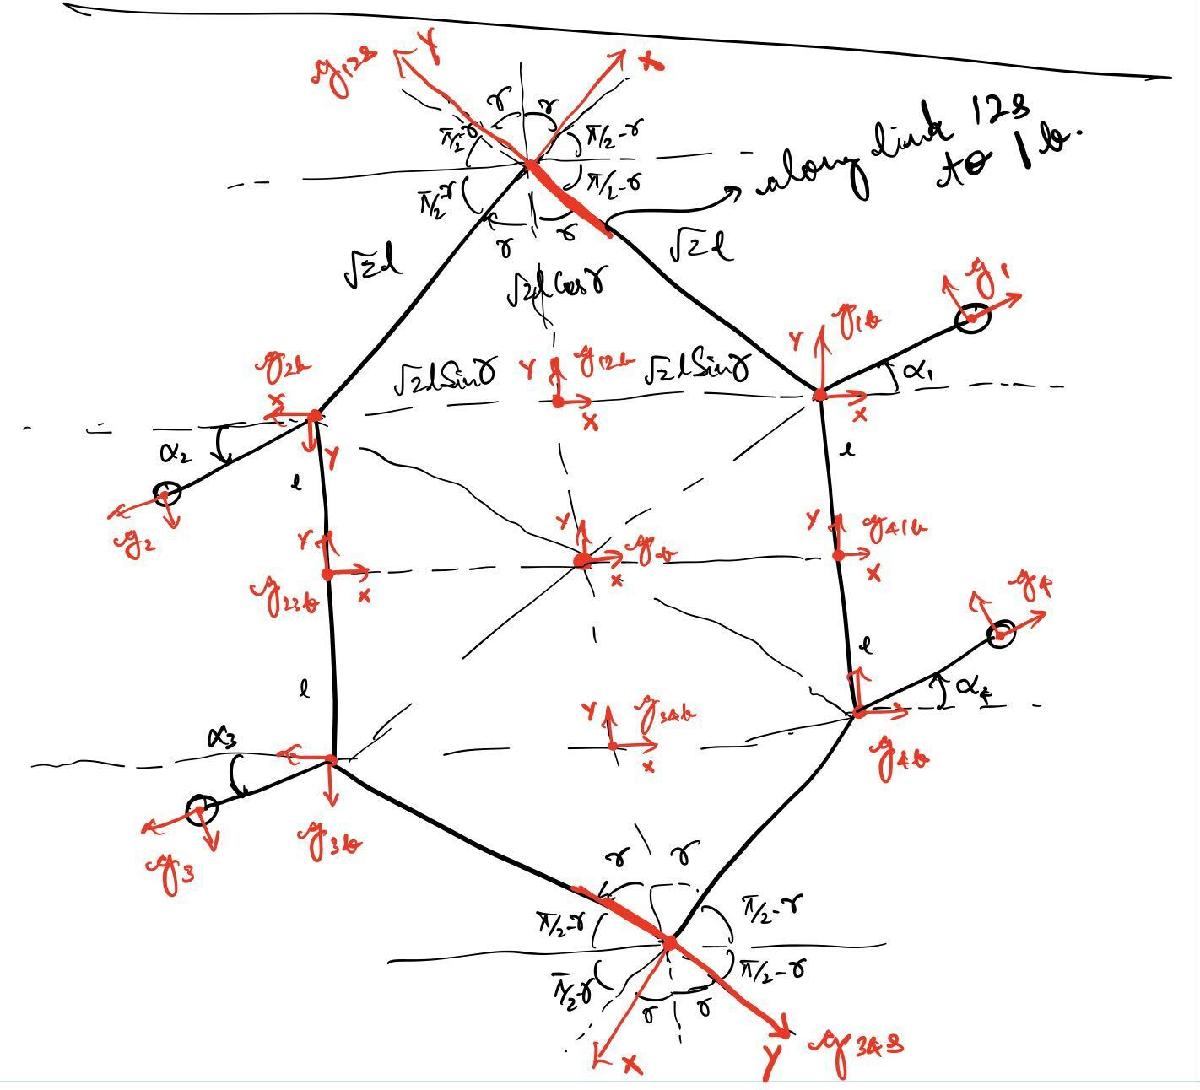

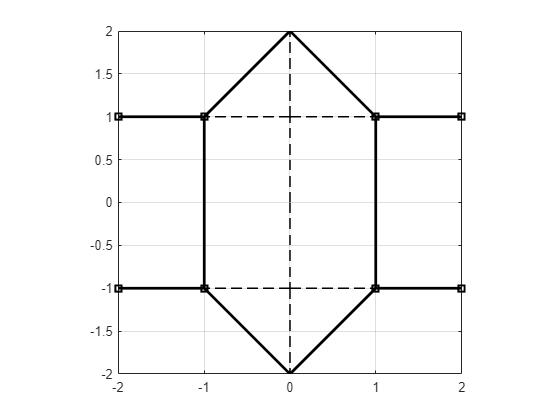

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';

syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real
syms gamma real
% assume(gamma < pi/2 && gamma >= 0); % nonnegative and range limited
% assumption

h_b__12b = [0, l, 0]';
h_b__34b = [0, -l, 0]';

h_12b__1b = [sqrt(2)*l*sin(gamma), 0, 0]';
h_12b__2b = [-sqrt(2)*l*sin(gamma), 0, pi]';
h_34b__3b = [-sqrt(2)*l*sin(gamma), 0, pi]';
h_34b__4b = [sqrt(2)*l*sin(gamma), 0, 0]';

% Transforms to top and bottom sprawl location:
h_12b__12s = [0,sqrt(2)*l*cos(gamma),gamma];
h_34b__34s = [0,-sqrt(2)*l*cos(gamma),pi+gamma];

% Transforms from sprawl to leg base:
h_12s__1b = [0,-sqrt(2)*l,-gamma];
h_12s__2b = [sqrt(2)*l*[cos(3*pi/2 - 2*gamma),sin(3*pi/2 - 2*gamma)],pi-gamma];
h_34s__3b = [0,-sqrt(2)*l,-gamma];
h_34s__4b = [sqrt(2)*l*[cos(3*pi/2 - 2*gamma),sin(3*pi/2 - 2*gamma)],pi-gamma];

syms alpha_i
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__i = AdjInvMap(h_ib__i);
J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__j_func = matlabFunction(zeros(3,3), 'Vars', [a, l, alpha_i]);

h_1b__1 = h_ib__i_func(a,l,alpha_1);
h_2b__2 = h_ib__i_func(a,l,alpha_2);
h_3b__3 = h_ib__i_func(a,l,alpha_3);
h_4b__4 = h_ib__i_func(a,l,alpha_4);

J_1b__1 = AdjInvMap(h_1b__1);
J_2b__2 = AdjInvMap(h_2b__2);
J_3b__3 = AdjInvMap(h_3b__3);
J_4b__4 = AdjInvMap(h_4b__4);

J_1b__2 = J_ib__j_func(a,l,alpha_1);
J_1b__3 = J_ib__j_func(a,l,alpha_1);
J_1b__4 = J_ib__j_func(a,l,alpha_1);

J_2b__1 = J_ib__j_func(a,l,alpha_2);
J_2b__3 = J_ib__j_func(a,l,alpha_2);
J_2b__4 = J_ib__j_func(a,l,alpha_2);

J_3b__1 = J_ib__j_func(a,l,alpha_3);
J_3b__2 = J_ib__j_func(a,l,alpha_3);
J_3b__4 = J_ib__j_func(a,l,alpha_3);

J_4b__1 = J_ib__j_func(a,l,alpha_4);
J_4b__2 = J_ib__j_func(a,l,alpha_4);
J_4b__3 = J_ib__j_func(a,l,alpha_4);

h_b__1b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b));
h_b__2b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b));
h_b__3b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b));
h_b__4b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b));

h_b__1 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1));
h_b__2 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2));
h_b__3 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3));
h_b__4 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4));

J_b__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1)));
J_b__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2)));
J_b__3 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3)));
J_b__4 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4)));

% Jacobians from sprawl joint to foot tips:
J_12s__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_12s__1b)*v2M_SE2(h_1b__1)));
J_12s__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_12s__2b)*v2M_SE2(h_2b__2)));
J_34s__3 = AdjInvMap(M2v_SE2(v2M_SE2(h_34s__3b)*v2M_SE2(h_3b__3)));
J_34s__4 = AdjInvMap(M2v_SE2(v2M_SE2(h_34s__4b)*v2M_SE2(h_4b__4)));

% Get the full Jacobian:
J_1_full = [J_b__1, 0.5*J_12s__1*theta_circ,...
    J_1b__1*theta_circ, J_2b__1*theta_circ, J_3b__1*theta_circ, J_4b__1*theta_circ];
J_2_full = [J_b__2, 0.5*J_12s__2*theta_circ,...
    J_1b__2*theta_circ, J_2b__2*theta_circ, J_3b__2*theta_circ, J_4b__2*theta_circ];
J_3_full = [J_b__3, 0.5*J_34s__3*theta_circ,...
    J_1b__3*theta_circ, J_2b__3*theta_circ, J_3b__3*theta_circ, J_4b__3*theta_circ];
J_4_full = [J_b__4, 0.5*J_34s__4*theta_circ,...
    J_1b__4*theta_circ, J_2b__4*theta_circ, J_3b__4*theta_circ, J_4b__4*theta_circ];

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % TRANSFORM VALIDAITON COMPLETE
% Before we obtain the connections, let's do a sanity check on the
% transforms we got to make sure it is the system/kinematics we intend to
% construct; get the remaining transforms we need:

h_b__12s = M2v_SE2(v2M_SE2(h_b__12b)*v2M_SE2(h_12b__12s));
h_b__34s = M2v_SE2(v2M_SE2(h_b__34b)*v2M_SE2(h_34b__34s));

% Now, get the lines we want to plot.
base_topbase_x = [0 h_b__12b(1)]; base_topbase_y = [0 h_b__12b(2)];
base_botbase_x = [0 h_b__34b(1)]; base_botbase_y = [0 h_b__34b(2)];

topbase_topsprawl_x = [h_b__12b(1) h_b__12s(1)]; topbase_topsprawl_y = [h_b__12b(2) h_b__12s(2)];
botbase_botsprawl_x = [h_b__34b(1) h_b__34s(1)]; botbase_botsprawl_y = [h_b__34b(2) h_b__34s(2)];

topbase_leg1base_x = [h_b__12b(1) h_b__1b(1)]; topbase_leg1base_y = [h_b__12b(2) h_b__1b(2)];
topbase_leg2base_x = [h_b__12b(1) h_b__2b(1)]; topbase_leg2base_y = [h_b__12b(2) h_b__2b(2)];

botbase_leg3base_x = [h_b__34b(1) h_b__3b(1)]; botbase_leg3base_y = [h_b__34b(2) h_b__3b(2)];
botbase_leg4base_x = [h_b__34b(1) h_b__4b(1)]; botbase_leg4base_y = [h_b__34b(2) h_b__4b(2)];

topsprawl_leg1base_x = [h_b__12s(1) h_b__1b(1)]; topsprawl_leg1base_y = [h_b__12s(2) h_b__1b(2)];
topsprawl_leg2base_x = [h_b__12s(1) h_b__2b(1)]; topsprawl_leg2base_y = [h_b__12s(2) h_b__2b(2)];

botsprawl_leg3base_x = [h_b__34s(1) h_b__3b(1)]; botsprawl_leg3base_y = [h_b__34s(2) h_b__3b(2)];
botsprawl_leg4base_x = [h_b__34s(1) h_b__4b(1)]; botsprawl_leg4base_y = [h_b__34s(2) h_b__4b(2)];

legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];

leg1base_leg4base_x = [h_b__1b(1) h_b__4b(1)]; leg1base_leg4base_y = [h_b__1b(2) h_b__4b(2)];
leg2base_leg3base_x = [h_b__2b(1) h_b__3b(1)]; leg2base_leg3base_y = [h_b__2b(2) h_b__3b(2)];

base_topbase_x = double(subs(base_topbase_x,l,1)); base_topbase_y = double(subs(base_topbase_y,l,1));
base_botbase_x = double(subs(base_botbase_x,l,1)); base_botbase_y = double(subs(base_botbase_y,l,1));

topbase_leg1base_x = double(subs(topbase_leg1base_x,[l,gamma],[1,pi/4])); topbase_leg1base_y = double(subs(topbase_leg1base_y,[l,gamma],[1,pi/4]));
topbase_leg2base_x = double(subs(topbase_leg2base_x,[l,gamma],[1,pi/4])); topbase_leg2base_y = double(subs(topbase_leg2base_y,[l,gamma],[1,pi/4]));

botbase_leg3base_x = double(subs(botbase_leg3base_x,[l,gamma],[1,pi/4])); botbase_leg3base_y = double(subs(botbase_leg3base_y,[l,gamma],[1,pi/4]));
botbase_leg4base_x = double(subs(botbase_leg4base_x,[l,gamma],[1,pi/4])); botbase_leg4base_y = double(subs(botbase_leg4base_y,[l,gamma],[1,pi/4]));

legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,gamma,alpha_1],[1,1,pi/4,0])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,gamma,alpha_1],[1,1,pi/4,0]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,gamma,alpha_2],[1,1,pi/4,0])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,gamma,alpha_2],[1,1,pi/4,0]));
legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,gamma,alpha_3],[1,1,pi/4,0])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,gamma,alpha_3],[1,1,pi/4,0]));
legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,gamma,alpha_4],[1,1,pi/4,0])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,gamma,alpha_4],[1,1,pi/4,0]));

topbase_topsprawl_x = double(subs(topbase_topsprawl_x,[l,gamma],[1,pi/4])); topbase_topsprawl_y = double(subs(topbase_topsprawl_y,[l,gamma],[1,pi/4]));
botbase_botsprawl_x = double(subs(botbase_botsprawl_x,[l,gamma],[1,pi/4])); botbase_botsprawl_y = double(subs(botbase_botsprawl_y,[l,gamma],[1,pi/4]));

topsprawl_leg1base_x = double(subs(topsprawl_leg1base_x,[l,gamma],[1,pi/4])); topsprawl_leg1base_y = double(subs(topsprawl_leg1base_y,[l,gamma],[1,pi/4]));
topsprawl_leg2base_x = double(subs(topsprawl_leg2base_x,[l,gamma],[1,pi/4])); topsprawl_leg2base_y = double(subs(topsprawl_leg2base_y,[l,gamma],[1,pi/4]));

botsprawl_leg3base_x = double(subs(botsprawl_leg3base_x,[l,gamma],[1,pi/4])); botsprawl_leg3base_y = double(subs(botsprawl_leg3base_y,[l,gamma],[1,pi/4]));
botsprawl_leg4base_x = double(subs(botsprawl_leg4base_x,[l,gamma],[1,pi/4])); botsprawl_leg4base_y = double(subs(botsprawl_leg4base_y,[l,gamma],[1,pi/4]));

leg1base_leg4base_x = double(subs(leg1base_leg4base_x,[l,gamma],[1,pi/4])); leg1base_leg4base_y = double(subs(leg1base_leg4base_y,[l,gamma],[1,pi/4]));
leg2base_leg3base_x = double(subs(leg2base_leg3base_x,[l,gamma],[1,pi/4])); leg2base_leg3base_y = double(subs(leg2base_leg3base_y,[l,gamma],[1,pi/4]));

figure()

plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
hold on; grid on;
plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
plot(topbase_leg1base_x,topbase_leg1base_y,'k--','LineWidth',1.2);
plot(topbase_leg2base_x,topbase_leg2base_y,'k--','LineWidth',1.2);
plot(botbase_leg3base_x,botbase_leg3base_y,'k--','LineWidth',1.2);
plot(botbase_leg4base_x,botbase_leg4base_y,'k--','LineWidth',1.2);
plot(topbase_topsprawl_x,topbase_topsprawl_y,'k--','LineWidth',1.2);
plot(botbase_botsprawl_x,botbase_botsprawl_y,'k--','LineWidth',1.2);

plot(topsprawl_leg1base_x,topsprawl_leg1base_y,'k','LineWidth',2.0);
plot(topsprawl_leg2base_x,topsprawl_leg2base_y,'k','LineWidth',2.0);
plot(botsprawl_leg3base_x,botsprawl_leg3base_y,'k','LineWidth',2.0);
plot(botsprawl_leg4base_x,botsprawl_leg4base_y,'k','LineWidth',2.0);

plot(leg1base_leg4base_x,leg1base_leg4base_y,'k','LineWidth',2.0);
plot(leg2base_leg3base_x,leg2base_leg3base_y,'k','LineWidth',2.0);

axis equal square;

plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);

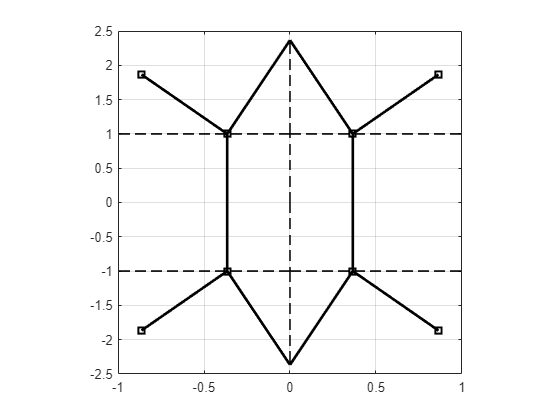

topbase_topsprawl_x = [h_b__12b(1) h_b__12s(1)]; topbase_topsprawl_y = [h_b__12b(2) h_b__12s(2)];
botbase_botsprawl_x = [h_b__34b(1) h_b__34s(1)]; botbase_botsprawl_y = [h_b__34b(2) h_b__34s(2)];
topsprawl_leg1base_x = [h_b__12s(1) h_b__1b(1)]; topsprawl_leg1base_y = [h_b__12s(2) h_b__1b(2)];
topsprawl_leg2base_x = [h_b__12s(1) h_b__2b(1)]; topsprawl_leg2base_y = [h_b__12s(2) h_b__2b(2)];
botsprawl_leg3base_x = [h_b__34s(1) h_b__3b(1)]; botsprawl_leg3base_y = [h_b__34s(2) h_b__3b(2)];
botsprawl_leg4base_x = [h_b__34s(1) h_b__4b(1)]; botsprawl_leg4base_y = [h_b__34s(2) h_b__4b(2)];
leg1base_leg4base_x = [h_b__1b(1) h_b__4b(1)]; leg1base_leg4base_y = [h_b__1b(2) h_b__4b(2)];
leg2base_leg3base_x = [h_b__2b(1) h_b__3b(1)]; leg2base_leg3base_y = [h_b__2b(2) h_b__3b(2)];
topbase_topsprawl_x = double(subs(topbase_topsprawl_x,[l,gamma],[1,pi/12])); topbase_topsprawl_y = double(subs(topbase_topsprawl_y,[l,gamma],[1,pi/12]));
botbase_botsprawl_x = double(subs(botbase_botsprawl_x,[l,gamma],[1,pi/12])); botbase_botsprawl_y = double(subs(botbase_botsprawl_y,[l,gamma],[1,pi/12]));
topsprawl_leg1base_x = double(subs(topsprawl_leg1base_x,[l,gamma],[1,pi/12])); topsprawl_leg1base_y = double(subs(topsprawl_leg1base_y,[l,gamma],[1,pi/12]));
topsprawl_leg2base_x = double(subs(topsprawl_leg2base_x,[l,gamma],[1,pi/12])); topsprawl_leg2base_y = double(subs(topsprawl_leg2base_y,[l,gamma],[1,pi/12]));
botsprawl_leg3base_x = double(subs(botsprawl_leg3base_x,[l,gamma],[1,pi/12])); botsprawl_leg3base_y = double(subs(botsprawl_leg3base_y,[l,gamma],[1,pi/12]));
botsprawl_leg4base_x = double(subs(botsprawl_leg4base_x,[l,gamma],[1,pi/12])); botsprawl_leg4base_y = double(subs(botsprawl_leg4base_y,[l,gamma],[1,pi/12]));
legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];
legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,gamma,alpha_1],[1,1,pi/12,pi/3])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,gamma,alpha_1],[1,1,pi/12,pi/3]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,gamma,alpha_2],[1,1,pi/12,-pi/3])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,gamma,alpha_2],[1,1,pi/12,-pi/3]));
legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,gamma,alpha_3],[1,1,pi/12,pi/3])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,gamma,alpha_3],[1,1,pi/12,pi/3]));
legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,gamma,alpha_4],[1,1,pi/12,-pi/3])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,gamma,alpha_4],[1,1,pi/12,-pi/3]));
leg1base_leg4base_x = double(subs(leg1base_leg4base_x,[l,gamma],[1,pi/12])); leg1base_leg4base_y = double(subs(leg1base_leg4base_y,[l,gamma],[1,pi/12]));
leg2base_leg3base_x = double(subs(leg2base_leg3base_x,[l,gamma],[1,pi/12])); leg2base_leg3base_y = double(subs(leg2base_leg3base_y,[l,gamma],[1,pi/12]));

figure()
plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
hold on; grid on;
plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
plot(topbase_leg1base_x,topbase_leg1base_y,'k--','LineWidth',1.2);
plot(topbase_leg2base_x,topbase_leg2base_y,'k--','LineWidth',1.2);
plot(botbase_leg3base_x,botbase_leg3base_y,'k--','LineWidth',1.2);
plot(botbase_leg4base_x,botbase_leg4base_y,'k--','LineWidth',1.2);
plot(topbase_topsprawl_x,topbase_topsprawl_y,'k--','LineWidth',1.2);
plot(botbase_botsprawl_x,botbase_botsprawl_y,'k--','LineWidth',1.2);
plot(topsprawl_leg1base_x,topsprawl_leg1base_y,'k','LineWidth',2.0);
plot(topsprawl_leg2base_x,topsprawl_leg2base_y,'k','LineWidth',2.0);
plot(botsprawl_leg3base_x,botsprawl_leg3base_y,'k','LineWidth',2.0);
plot(botsprawl_leg4base_x,botsprawl_leg4base_y,'k','LineWidth',2.0);
plot(leg1base_leg4base_x,leg1base_leg4base_y,'k','LineWidth',2.0);
plot(leg2base_leg3base_x,leg2base_leg3base_y,'k','LineWidth',2.0);
axis equal square;
plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);

The transforms looks great, and we are ready to check the structure of the squared inter-leg distance and based on the outcome we can decide to compute the local connection.

C = [eye(2,2),zeros(2,1)];
k_12 = simplify(C*(h_b__2 - h_b__1),'Steps',10)

$$k\_12 = \left(\begin{array}{c} -l\,\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)\\ -a\,l\,\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{2}\right)\right) \end{array}\right)$$

k_34 = simplify(C*(h_b__4 - h_b__3),'Steps',10)

$$k\_34 = \left(\begin{array}{c} l\,\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)\\ a\,l\,\left(\sin\left(\alpha_{3}\right)+\sin\left(\alpha_{4}\right)\right) \end{array}\right)$$

ksq_12 = simplify((C*(h_b__2 - h_b__1))'*C*(h_b__2 - h_b__1),'Steps',10)

$$ksq\_12 = l^{2}\,{\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{2}\right)\right)}^{2}$$

ksq_34 = simplify((C*(h_b__4 - h_b__3))'*C*(h_b__4 - h_b__3),'Steps',10)

$$ksq\_34 = l^{2}\,{\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{3}\right)+\sin\left(\alpha_{4}\right)\right)}^{2}$$

ksq_12_func = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2, gamma]);

% Now, let's discretize the space and scatter the points around to see if a
% connection will be possible.
dnum = 51;

% set a numerical threshold:
numT = 1e-5;

aa = 1;                                 
ll = 1;                                 

ank = pi/4; meanA = 0;                    
ankS = pi/4; threshS = deg2rad(10); %enter the thresholding angle to prevent sprawlangle from becoming hz or vert flat
ankS = ankS - threshS; meanS = pi/4;
% this has to neither be zero not 180 all the way due to bifurcation issues
% let's make sure the ankle for sprawl is always smaller that pi/4.

am = linspace(meanA-ank,meanA+ank,dnum);          
ap = am;
g = linspace(meanS-ankS,meanS+ankS,dnum);

[am,ap,g] = meshgrid(am,ap,g);
a3 = am; a4 = ap;

ksq_sweep = ksq_12_func(aa, ll, am, ap, g);

First, we plot the $k^2$ value at $\gamma = \frac{\pi}{4}$ (and some other values) to replicate what we got earlier as a pre-sanity-check. Make sure a uniform color scale and axis is used.

idx = (abs(g - pi/4) <= numT); % numerical equating
disp(['gamma = ',num2str(mean(g(idx),'all'))]);

gamma = 0.7854


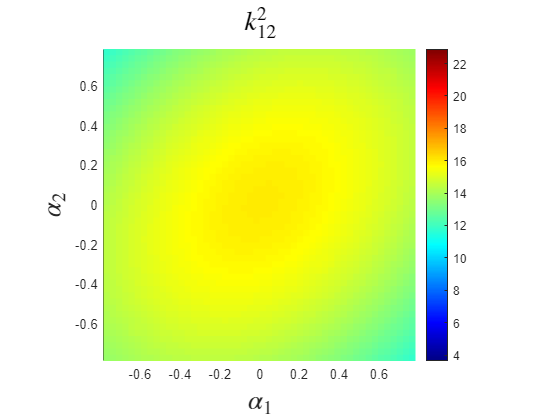

maxC = max(ksq_sweep,[],'all');
minC = min(ksq_sweep,[],'all');

figure()
surf(reshape(am(idx),dnum,dnum),...
    reshape(ap(idx),dnum,dnum),...
    reshape(ksq_sweep(idx),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet); caxis([minC maxC]);
colorbar('ylim',[minC maxC]);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

disp(['gamma = ',num2str(mean(g(:,:,5),'all'))]);

gamma = 0.27227


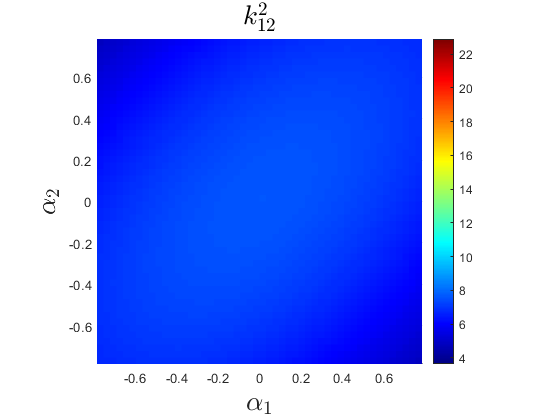

figure()
surf(reshape(am(:,:,5),dnum,dnum),...
    reshape(ap(:,:,5),dnum,dnum),...
    reshape(ksq_sweep(:,:,5),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet); caxis([minC maxC]);
colorbar('ylim',[minC maxC]);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

disp(['gamma = ',num2str(mean(g(:,:,46),'all'))]);

gamma = 1.2741


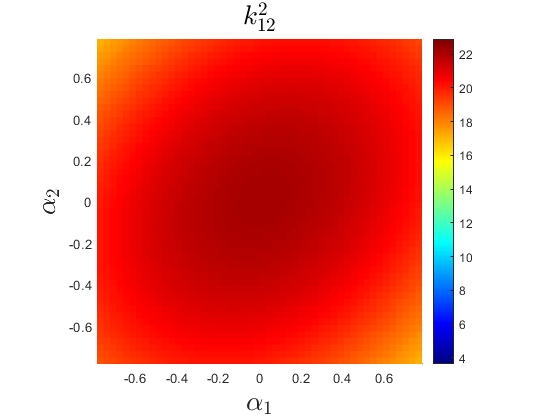

figure()
surf(reshape(am(:,:,46),dnum,dnum),...
    reshape(ap(:,:,46),dnum,dnum),...
    reshape(ksq_sweep(:,:,46),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet); caxis([minC maxC]);
colorbar('ylim',[minC maxC]);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

That looks about right! See that at all these different $\gamma$ the distance is roughly constant. Hence, we shall expect to see 

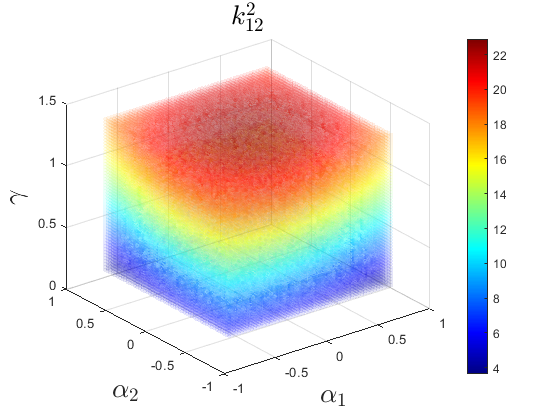

figure()
scatter3(am(:),ap(:),g(:),10,ksq_sweep(:),'filled','MarkerFaceAlpha',0.1,'MarkerEdgeColor','none','Marker','o');
colormap(jet);
colorbar();
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$\gamma$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

This looks great! The iso-$k^2$ surfaces seem to cover the entire controllable shape-space (just the leg swing directions). Now, we can obtain the pfaffian constraints and local connections for the systems considered!

% pfaff_12 = [C*J_1_full;
%             C*J_2_full]
% pfaff_23 = [C*J_2_full;
%             C*J_3_full]
% pfaff_34 = [C*J_3_full;
%             C*J_4_full]
% pfaff_41 = [C*J_4_full;
%             C*J_1_full]
% pfaff_13 = [C*J_1_full;
%             C*J_3_full]
% pfaff_24 = [C*J_2_full;
%             C*J_4_full]
% % Let's make some assumptions to simplify the next steps
% % assume(a<=1);
% assume(gamma>0 & gamma<pi/2);
% % assume(l>0);
% % assume(alpha_1>=-pi/4 & alpha_1<=pi/4);
% % assume(alpha_2>=-pi/4 & alpha_2<=pi/4);
% 
% % Solve for the local connections
% A_12 = pfaff_12(:,1:4)\pfaff_12(:,5:end) %,'Steps',10
% A_23 = pfaff_23(:,1:4)\pfaff_23(:,5:end)
% A_34 = pfaff_34(:,1:4)\pfaff_34(:,5:end)
% A_41 = pfaff_41(:,1:4)\pfaff_41(:,5:end)
% A_13 = pfaff_13(:,1:4)\pfaff_13(:,5:end)
% A_24 = pfaff_24(:,1:4)\pfaff_24(:,5:end)
% % Let's save the data as a final step:
% save('case2_pfaff_A_syms.mat','a','l','gamma','alpha_1','alpha_2',...
%     'pfaff_12','pfaff_23','pfaff_34','pfaff_41','pfaff_13','pfaff_24',...
%     'A_12','A_23','A_34','A_41','A_13','A_24',...
%     'a1','a2','g','ksq_sweep');

The sad part is these connections have issues in the sense that the matrices that are being inverted are close to being singular.

## Case 2: Analysis on the $k^2$ deternminant

In the earlier section we noticed that simplifications couldn't be made on the local connections due to a division by zero issue; we need to tease out the properties of $\omega^{\left(1:3\right)}$.

% % Let's load the data computed earlier:
% load('case2_pfaff_A_syms.mat');
% 
% % Let's take the determinant of the first 3 cols of the pfaffian matrices
% % we got and plot it as a function of the shape-space of the system
% det_12 = det(pfaff_12(:,1:4));
% det_12_func = matlabFunction(det_12,'Vars',[a,l,alpha_1,alpha_2,gamma]);
% det_12_sweep = det_12_func(0.1,1,a1,a2,g);

The values are close to singular and are in the order of machine precision. Hence, we move on to case 3 in the interest of time.

One last thing would be evaluate the connection vector field and see if we get anything other than inf.

% % Make a function out of the connection
% A_12_func = matlabFunction(subs(A_12,[a,l],[1,1]),'Vars',[alpha_1,alpha_2,gamma]);
% % Sweep over everything you got:
% A_12_sweep = A_12_func(a1,a2,g);

The values are huge as expected and doesn't give us a connection.

## Case 2: Connection through a conservation law

Here, the goal is to obtain a connection using our constant inter-leg distance conservation law.

gradksq_12_a1 = simplify(diff(ksq_12,alpha_1),'Steps',10)

$$gradksq\_12\_a1 = -2\,a\,l^{2}\,\left(\sqrt{2}\,\cos\left(\alpha_{1}-\gamma \right)-\sqrt{2}\,\cos\left(\alpha_{1}+\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)$$

gradksq_12_a2 = simplify(diff(ksq_12,alpha_2),'Steps',10)

$$gradksq\_12\_a2 = 2\,a\,l^{2}\,\left(\sqrt{2}\,\cos\left(\alpha_{2}+\gamma \right)-\sqrt{2}\,\cos\left(\alpha_{2}-\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)$$

gradksq_12_g = simplify(diff(ksq_12,gamma),'Steps',10)

$$gradksq\_12\_g = 4\,\sqrt{2}\,l^{2}\,\cos\left(\gamma \right)\,\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)$$

gradksq_34_a3 = simplify(diff(ksq_34,alpha_3),'Steps',10)

$$gradksq\_34\_a3 = -2\,a\,l^{2}\,\left(\sqrt{2}\,\cos\left(\alpha_{3}-\gamma \right)-\sqrt{2}\,\cos\left(\alpha_{3}+\gamma \right)+a\,\sin\left(\alpha_{3}-\alpha_{4}\right)\right)$$

gradksq_34_a4 = simplify(diff(ksq_34,alpha_4),'Steps',10)

$$gradksq\_34\_a4 = 2\,a\,l^{2}\,\left(\sqrt{2}\,\cos\left(\alpha_{4}+\gamma \right)-\sqrt{2}\,\cos\left(\alpha_{4}-\gamma \right)+a\,\sin\left(\alpha_{3}-\alpha_{4}\right)\right)$$

gradksq_34_g = simplify(diff(ksq_34,gamma),'Steps',10)

$$gradksq\_34\_g = 4\,\sqrt{2}\,l^{2}\,\cos\left(\gamma \right)\,\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)$$

% Seems like this should not be zero at any given point; let's check this
% as a function of our shape-space and make sure there are no zeros, and
% with that we should obtain our connection.
% gradksq_12_g_func = matlabFunction(gradksq_12_g,'Vars',[a,l,alpha_1,alpha_2,gamma]);
% gradksq_12_g_sweep = gradksq_12_g_func(aa,ll,a1,a2,g);
% sum(gradksq_12_g_sweep == 0,'all')

This coefficient of $\dot{\gamma}$ is non-zero for the entire shape-space and hence, there exists a non-singular map from the limb angular velocities to the sprawl change.

Now, we can construct the geometry surrounding sprawl.

coeff_a1_12 = simplify(-gradksq_12_a1/gradksq_12_g,'Steps',10)

$$coeff\_a1\_12 = \frac{a\,\left(2\,\cos\left(\alpha_{1}-\gamma \right)-2\,\cos\left(\alpha_{1}+\gamma \right)+\sqrt{2}\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}{4\,\cos\left(\gamma \right)\,\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)}$$

coeff_a3_34 = simplify(-gradksq_34_a3/gradksq_34_g,'Steps',10)

$$coeff\_a3\_34 = \frac{a\,\left(2\,\cos\left(\alpha_{3}-\gamma \right)-2\,\cos\left(\alpha_{3}+\gamma \right)+\sqrt{2}\,a\,\sin\left(\alpha_{3}-\alpha_{4}\right)\right)}{4\,\cos\left(\gamma \right)\,\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)}$$

coeff_a2_12 = simplify(-gradksq_12_a2/gradksq_12_g,'Steps',10)

$$coeff\_a2\_12 = -\frac{a\,\left(2\,\cos\left(\alpha_{2}+\gamma \right)-2\,\cos\left(\alpha_{2}-\gamma \right)+\sqrt{2}\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}{4\,\cos\left(\gamma \right)\,\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)}$$

coeff_a4_34 = simplify(-gradksq_34_a4/gradksq_34_g,'Steps',10)  

$$coeff\_a4\_34 = -\frac{a\,\left(2\,\cos\left(\alpha_{4}+\gamma \right)-2\,\cos\left(\alpha_{4}-\gamma \right)+\sqrt{2}\,a\,\sin\left(\alpha_{3}-\alpha_{4}\right)\right)}{4\,\cos\left(\gamma \right)\,\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)}$$

Now, we can plot this connection vector field in sprawl as a function of the shape-space.

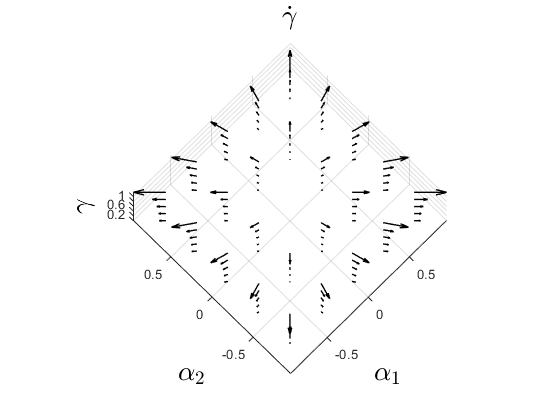

coeff_a1_12_func = matlabFunction(coeff_a1_12,'Vars',[a,l,alpha_1,alpha_2,gamma]);
coeff_a2_12_func = matlabFunction(coeff_a2_12,'Vars',[a,l,alpha_1,alpha_2,gamma]);
coeff_a1_12_sweep = coeff_a1_12_func(aa,ll,am,ap,g);
coeff_a2_12_sweep = coeff_a2_12_func(aa,ll,am,ap,g);
coeff_a3_34_func = matlabFunction(coeff_a3_34,'Vars',[a,l,alpha_3,alpha_4,gamma]);
coeff_a4_34_func = matlabFunction(coeff_a4_34,'Vars',[a,l,alpha_3,alpha_4,gamma]);
coeff_a3_34_sweep = coeff_a3_34_func(aa,ll,a3,a4,g);
coeff_a4_34_sweep = coeff_a4_34_func(aa,ll,a3,a4,g);

% Choose the view angle
% azi = -37.5; elv = 30; % default values
azi = -45; elv = 78;
% Size of the arrows
qW = 1;
% Let's plot only a fraction of the points- enter the number of points in
% each direction
numP = 5; 
skp = floor(dnum/(numP-1));
idx = 1:skp:dnum; transl = (dnum-idx(end))/2;
if transl >= 1
    idx = idx + floor(transl); % if it less than one, leave it as such.
end

% Plot
figure()
quiver3(am(idx,idx,idx),ap(idx,idx,idx),g(idx,idx,idx),...
    coeff_a1_12_sweep(idx,idx,idx),coeff_a2_12_sweep(idx,idx,idx),...
    zeros(size(coeff_a2_12_sweep(idx,idx,idx))),...
    'Color','k','LineWidth',qW);
axis equal tight; view(azi,elv);
title('$\dot{\gamma}$','Interpreter','latex','Color','k',FontSize=20);
xlabel('$\alpha_{1}$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\alpha_{2}$','Interpreter','latex','Color','k',FontSize=20);
zlabel('$\gamma$','Interpreter','latex','Color','k',FontSize=20);

Now, we are ready to get $\gamma$ as a function of given leg motion. Since this is a conservative vector field, note that we only need to explore straight line paths in the shape-space. The cool part is, unlike the CLARI kinematics, here most of the shape space in accessible. Let's choose the same paths for both submanifolds 12 and 34.

### Breast-stroke (bS) kind of forward motion

Get the analytical results first and then get the numerical results for comparison.

Analytical results took too long, let's compute this numerically starting with ode45.

syms p_1 p_2 p_3 p_4 real
syms t real positive % make sure you limit 't' to the [0,1] domain
% assume(t >= 0 & t < 1);
gamma_dot_bS_12 = subs(coeff_a1_12,[a,l,alpha_1,alpha_2],[aa,ll,p_1*t,p_2*t])*p_1...
    + subs(coeff_a2_12,[a,l,alpha_1,alpha_2],[aa,ll,p_1*t,p_2*t])*p_2

$$gamma\_dot\_bS\_12 = \begin{array}{l} \frac{p_{1}\,\left(2\,\cos\left(\gamma -p_{1}\,t\right)-2\,\cos\left(\gamma +p_{1}\,t\right)+\sqrt{2}\,\sin\left(p_{1}\,t-p_{2}\,t\right)\right)}{\sigma_{1}}-\frac{p_{2}\,\left(2\,\cos\left(\gamma +p_{2}\,t\right)-2\,\cos\left(\gamma -p_{2}\,t\right)+\sqrt{2}\,\sin\left(p_{1}\,t-p_{2}\,t\right)\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=4\,\cos\left(\gamma \right)\,\left(\cos\left(p_{1}\,t\right)+\cos\left(p_{2}\,t\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right) \end{array}$$

gamma_dot_bS_34 = subs(coeff_a3_34,[a,l,alpha_3,alpha_4],[aa,ll,p_3*t,p_4*t])*p_3...
    + subs(coeff_a4_34,[a,l,alpha_3,alpha_4],[aa,ll,p_3*t,p_4*t])*p_4

$$gamma\_dot\_bS\_34 = \begin{array}{l} \frac{p_{3}\,\left(2\,\cos\left(\gamma -p_{3}\,t\right)-2\,\cos\left(\gamma +p_{3}\,t\right)+\sqrt{2}\,\sin\left(p_{3}\,t-p_{4}\,t\right)\right)}{\sigma_{1}}-\frac{p_{4}\,\left(2\,\cos\left(\gamma +p_{4}\,t\right)-2\,\cos\left(\gamma -p_{4}\,t\right)+\sqrt{2}\,\sin\left(p_{3}\,t-p_{4}\,t\right)\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=4\,\cos\left(\gamma \right)\,\left(\cos\left(p_{3}\,t\right)+\cos\left(p_{4}\,t\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right) \end{array}$$

gamma_dot_bS_12_func = matlabFunction(simplify(subs(gamma_dot_bS_12,[a,l],[aa,ll])),'Vars',[p_1,p_2,t,gamma])

gamma_dot_bS_12_func = function_handle with value:
    @(p_1,p_2,t,gamma)(p_1.*sin(p_1.*t).*sin(gamma).*4.0+p_2.*sin(p_2.*t).*sin(gamma).*4.0-sqrt(2.0).*p_1.*cos(p_1.*t).*sin(p_2.*t)+sqrt(2.0).*p_1.*cos(p_2.*t).*sin(p_1.*t)+sqrt(2.0).*p_2.*cos(p_1.*t).*sin(p_2.*t)-sqrt(2.0).*p_2.*cos(p_2.*t).*sin(p_1.*t))./(cos(gamma).*(cos(p_1.*t)+cos(p_2.*t)+sqrt(2.0).*sin(gamma).*2.0).*4.0)


gamma_dot_bS_34_func = matlabFunction(simplify(subs(gamma_dot_bS_34,[a,l],[aa,ll])),'Vars',[p_3,p_4,t,gamma])

gamma_dot_bS_34_func = function_handle with value:
    @(p_3,p_4,t,gamma)(p_3.*sin(p_3.*t).*sin(gamma).*4.0+p_4.*sin(p_4.*t).*sin(gamma).*4.0-sqrt(2.0).*p_3.*cos(p_3.*t).*sin(p_4.*t)+sqrt(2.0).*p_3.*cos(p_4.*t).*sin(p_3.*t)+sqrt(2.0).*p_4.*cos(p_3.*t).*sin(p_4.*t)-sqrt(2.0).*p_4.*cos(p_4.*t).*sin(p_3.*t))./(cos(gamma).*(cos(p_3.*t)+cos(p_4.*t)+sqrt(2.0).*sin(gamma).*2.0).*4.0)


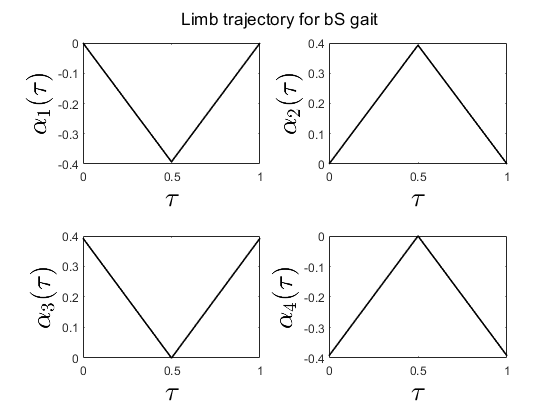

% running this multiple times for debugging and checking
clear t y temp1 temp2 a1_t a2_t a3_t a4_t g_t
% Let's swing the legs to the limits:
p1 = -ank; p2 = +ank; p3 = p2; p4 = p1; % forward breast-stroke kinda gait
% Ready to run the ode45 for a solution (giving each solution equal time):
[t,y] = ode45(@(t,y) gamma_dot_bS_12_func(p1,p2,t,y), [0 0.5], min(g,[],'all')); % give the lowest IC for gamma
temp1 = t(:); % first time vector -- we need this stitching procedure to be more adaptive to whatever time vector is returned
a1_t = p1*t(:); % this is your first leg motion in the first contact state
a2_t = p2*t(:); % second leg motion in the first contact state
g_t = y(:); % your gamma trajectory
% Solve for the second contact state
[t,y] = ode45(@(t,y) gamma_dot_bS_34_func(p3,p4,t,y), [0 0.5], g_t(end)); % continue with latest gamma for second contact state
temp2 = t(:); % second time vector
a3_t = [interp1(t(:),p3*flipud(t(:)),temp1); p3*t(2:end)]; % leg motion 3, for both contact phases
a4_t = [interp1(t(:),p4*flipud(t(:)),temp1); p4*t(2:end)]; % leg motion 4, for both contact phases
a1_t = [a1_t; interp1(temp1,flipud(a1_t),temp2(2:end))]; % leg motion 1 updated for the second contact phase
a2_t = [a2_t; interp1(temp1,flipud(a2_t),temp2(2:end))]; % leg motion 2 updated for the second contact phase
g_t = [g_t; y(2:end)]; % total gamma trajectory
tau = [temp1; temp1(end)+temp2(2:end)]; % gait phase trajectory
% Let's plot the leg trajectories and as a function of the gait phase
figure()
subplot(2,2,1)
plot(tau,a1_t,'k','linewidth',1.2);
xlabel('$\tau$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\alpha_{1}(\tau)$','Interpreter','latex','Color','k',FontSize=20);
subplot(2,2,2)
plot(tau,a2_t,'k','linewidth',1.2);
xlabel('$\tau$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\alpha_{2}(\tau)$','Interpreter','latex','Color','k',FontSize=20);

subplot(2,2,3)
plot(tau,a3_t,'k','linewidth',1.2);
xlabel('$\tau$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\alpha_{3}(\tau)$','Interpreter','latex','Color','k',FontSize=20);

subplot(2,2,4)
plot(tau,a4_t,'k','linewidth',1.2);
xlabel('$\tau$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\alpha_{4}(\tau)$','Interpreter','latex','Color','k',FontSize=20);

sgtitle('Limb trajectory for bS gait');

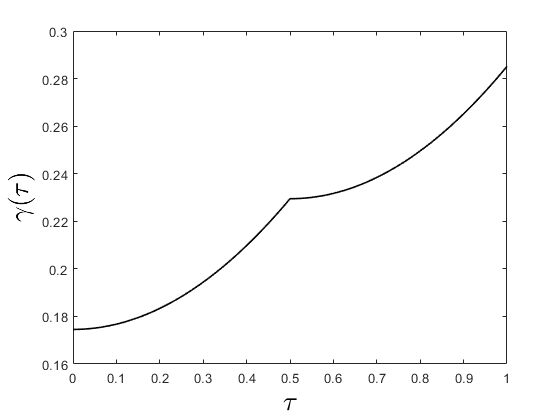

figure()
plot(tau,g_t,'k','linewidth',1.2);
xlabel('$\tau$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\gamma(\tau)$','Interpreter','latex','Color','k',FontSize=20);

This is great! Now, we are ready to plot the shape change as a function of gait.

Here, we shall make a video of the robot.

% % Let's define colors for the two contact states
% circ1 = (1/255)*[215, 25, 28]; % for contact state 12
% circ2 = (1/255)*[96, 0, 220]; % for contact state 34
% 
% % Line width
% lW = 2.0;
% % Size of leg contact
% circS = 300;
% 
% % Initialize different links
% topsprawl_leg1base_x = [h_b__12s(1) h_b__1b(1)]; topsprawl_leg1base_y = [h_b__12s(2) h_b__1b(2)];
% topsprawl_leg2base_x = [h_b__12s(1) h_b__2b(1)]; topsprawl_leg2base_y = [h_b__12s(2) h_b__2b(2)];
% botsprawl_leg3base_x = [h_b__34s(1) h_b__3b(1)]; botsprawl_leg3base_y = [h_b__34s(2) h_b__3b(2)];
% botsprawl_leg4base_x = [h_b__34s(1) h_b__4b(1)]; botsprawl_leg4base_y = [h_b__34s(2) h_b__4b(2)];
% legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
% legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
% legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
% legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];
% leg1base_leg4base_x = [h_b__1b(1) h_b__4b(1)]; leg1base_leg4base_y = [h_b__1b(2) h_b__4b(2)];
% leg2base_leg3base_x = [h_b__2b(1) h_b__3b(1)]; leg2base_leg3base_y = [h_b__2b(2) h_b__3b(2)];
% 
% % Initialize points at the leg tips"
% leg1_x = h_b__1(1); leg1_y = h_b__1(2);
% leg2_x = h_b__2(1); leg2_y = h_b__2(2);
% leg3_x = h_b__3(1); leg3_y = h_b__3(2);
% leg4_x = h_b__4(1); leg4_y = h_b__4(2);
% 
% % Make them into functions
% ts_lb1_x = matlabFunction(subs(topsprawl_leg1base_x,l,ll),'Vars',gamma); ts_lb1_y = matlabFunction(subs(topsprawl_leg1base_y,l,ll),'Vars',gamma);
% ts_lb2_x = matlabFunction(subs(topsprawl_leg2base_x,l,ll),'Vars',gamma); ts_lb2_y = matlabFunction(subs(topsprawl_leg2base_y,l,ll),'Vars',gamma);
% bs_lb3_x = matlabFunction(subs(botsprawl_leg3base_x,l,ll),'Vars',gamma); bs_lb3_y = matlabFunction(subs(botsprawl_leg3base_y,l,ll),'Vars',gamma);
% bs_lb4_x = matlabFunction(subs(botsprawl_leg4base_x,l,ll),'Vars',gamma); bs_lb4_y = matlabFunction(subs(botsprawl_leg4base_y,l,ll),'Vars',gamma);
% lb1_l1_x = matlabFunction(subs(legbase1_leg1_x,[a l],[aa ll]),'Vars',[gamma, alpha_1]); lb1_l1_y = matlabFunction(subs(legbase1_leg1_y,[a l],[aa ll]),'Vars',[gamma, alpha_1]);
% lb2_l2_x = matlabFunction(subs(legbase2_leg2_x,[a l],[aa ll]),'Vars',[gamma, alpha_2]); lb2_l2_y = matlabFunction(subs(legbase2_leg2_y,[a l],[aa ll]),'Vars',[gamma, alpha_2]);
% lb3_l3_x = matlabFunction(subs(legbase3_leg3_x,[a l],[aa ll]),'Vars',[gamma, alpha_3]); lb3_l3_y = matlabFunction(subs(legbase3_leg3_y,[a l],[aa ll]),'Vars',[gamma, alpha_3]);
% lb4_l4_x = matlabFunction(subs(legbase4_leg4_x,[a l],[aa ll]),'Vars',[gamma, alpha_4]); lb4_l4_y = matlabFunction(subs(legbase4_leg4_y,[a l],[aa ll]),'Vars',[gamma, alpha_4]);
% lb1_lb4_x = matlabFunction(subs(leg1base_leg4base_x,l,ll),'Vars',gamma); lb1_lb4_y = matlabFunction(subs(leg1base_leg4base_y,l,ll),'Vars',gamma);
% lb2_lb3_x = matlabFunction(subs(leg2base_leg3base_x,l,ll),'Vars',gamma); lb2_lb3_y = matlabFunction(subs(leg2base_leg3base_y,l,ll),'Vars',gamma);
% l1_x = matlabFunction(subs(leg1_x,[a l],[aa ll]),'Vars',[gamma, alpha_1]); l1_y = matlabFunction(subs(leg1_y,[a l],[aa ll]),'Vars',[gamma, alpha_1]);
% l2_x = matlabFunction(subs(leg2_x,[a l],[aa ll]),'Vars',[gamma, alpha_2]); l2_y = matlabFunction(subs(leg2_y,[a l],[aa ll]),'Vars',[gamma, alpha_2]);
% l3_x = matlabFunction(subs(leg3_x,[a l],[aa ll]),'Vars',[gamma, alpha_3]); l3_y = matlabFunction(subs(leg3_y,[a l],[aa ll]),'Vars',[gamma, alpha_3]);
% l4_x = matlabFunction(subs(leg4_x,[a l],[aa ll]),'Vars',[gamma, alpha_4]); l4_y = matlabFunction(subs(leg4_y,[a l],[aa ll]),'Vars',[gamma, alpha_4]);
% 
% % Start the loop and iterate over the configurations in body frame space:
% % Create the video object
% video = VideoWriter(strcat('case2_bS_12_34','.mp4'),'MPEG-4'); % creates mp4
% % Enter the length of the video:
% vidT = 5;
% % Set the framerate
% video.FrameRate = round(length(tau)/vidT); % roughly takes about 10seconds to complete the video
% % Set the quality
% video.Quality = 100;
% % Open the video
% open(video);
% 
% % Start plotting
% figure('units','pixels','position',[0 0 1920 1080],'Color','w')
% 
% for i = 1:length(tau)
%     
%     % Plot and set things up
%     plot(lb1_lb4_x(g_t(i)),lb1_lb4_y(g_t(i)),'k','LineWidth',lW);
%     grid on; hold on;
%     plot(lb2_lb3_x(g_t(i)),lb2_lb3_y(g_t(i)),'k','LineWidth',lW);
%     axis([-2.5 2.5 -2.5 2.5]);
%     axis equal;
%     % check if it is the first contact state or or
%     % the second one.
%     if tau(i) < 0.5 % contact state 1
%         plot(ts_lb1_x(g_t(i)),ts_lb1_y(g_t(i)),'LineWidth',lW,'Color',circ1);
%         plot(ts_lb2_x(g_t(i)),ts_lb2_y(g_t(i)),'LineWidth',lW,'Color',circ1);
%         plot(bs_lb3_x(g_t(i)),bs_lb3_y(g_t(i)),'LineWidth',lW,'Color','k');
%         plot(bs_lb4_x(g_t(i)),bs_lb4_y(g_t(i)),'LineWidth',lW,'Color','k');
%         plot(lb1_l1_x(g_t(i),a1_t(i)),lb1_l1_y(g_t(i),a1_t(i)),'LineWidth',lW,'Color',circ1);
%         plot(lb2_l2_x(g_t(i),a2_t(i)),lb2_l2_y(g_t(i),a2_t(i)),'LineWidth',lW,'Color',circ1);
%         plot(lb3_l3_x(g_t(i),a3_t(i)),lb3_l3_y(g_t(i),a3_t(i)),'LineWidth',lW,'Color','k');
%         plot(lb4_l4_x(g_t(i),a4_t(i)),lb4_l4_y(g_t(i),a4_t(i)),'LineWidth',lW,'Color','k');
%         scatter(l1_x(g_t(i),a1_t(i)),l1_y(g_t(i),a1_t(i)),circS,circ1,'filled');
%         scatter(l2_x(g_t(i),a2_t(i)),l2_y(g_t(i),a2_t(i)),circS,circ1,'filled');
%         scatter(l3_x(g_t(i),a3_t(i)),l3_y(g_t(i),a3_t(i)),circS,circ2);
%         scatter(l4_x(g_t(i),a4_t(i)),l4_y(g_t(i),a4_t(i)),circS,circ2);
%     else % contact state 2
%         plot(ts_lb1_x(g_t(i)),ts_lb1_y(g_t(i)),'LineWidth',lW,'Color','k');
%         plot(ts_lb2_x(g_t(i)),ts_lb2_y(g_t(i)),'LineWidth',lW,'Color','k');
%         plot(bs_lb3_x(g_t(i)),bs_lb3_y(g_t(i)),'LineWidth',lW,'Color',circ2);
%         plot(bs_lb4_x(g_t(i)),bs_lb4_y(g_t(i)),'LineWidth',lW,'Color',circ2);
%         plot(lb1_l1_x(g_t(i),a1_t(i)),lb1_l1_y(g_t(i),a1_t(i)),'LineWidth',lW,'Color','k');
%         plot(lb2_l2_x(g_t(i),a2_t(i)),lb2_l2_y(g_t(i),a2_t(i)),'LineWidth',lW,'Color','k');
%         plot(lb3_l3_x(g_t(i),a3_t(i)),lb3_l3_y(g_t(i),a3_t(i)),'LineWidth',lW,'Color',circ2);
%         plot(lb4_l4_x(g_t(i),a4_t(i)),lb4_l4_y(g_t(i),a4_t(i)),'LineWidth',lW,'Color',circ2);
%         scatter(l1_x(g_t(i),a1_t(i)),l1_y(g_t(i),a1_t(i)),circS,circ1);
%         scatter(l2_x(g_t(i),a2_t(i)),l2_y(g_t(i),a2_t(i)),circS,circ1);
%         scatter(l3_x(g_t(i),a3_t(i)),l3_y(g_t(i),a3_t(i)),circS,circ2,'filled');
%         scatter(l4_x(g_t(i),a4_t(i)),l4_y(g_t(i),a4_t(i)),circS,circ2,'filled');
%     end
% 
%     % Draw the current plot since we are in a loop:
%     drawnow;
%     % Capture the frame:
%     writeVideo(video,getframe(gcf));
%     % Clear the frame if it is not the final one:
%     if i ~= length(tau)
%         clf;
%     end
% end
% % Close the video once everything is plotted
% close(video);

### Spirals to explore the shape space

Since we have sprawl solutions covering the entire shape-space, we need an open loop gait to explore most of this space and interpolate. My solution to this is to use the simple archimedean spiram to explore the shape-space

% Let's first define them as symbolic variables
syms alpha_hat tau n real
alpha_1 = alpha_hat*tau*cos(n*2*pi*tau)

$$alpha\_1 = \hat{\alpha }\,\tau \,\cos\left(2\,\pi \,n\,\tau \right)$$

alpha_2 = alpha_hat*tau*sin(n*2*pi*tau)

$$alpha\_2 = \hat{\alpha }\,\tau \,\sin\left(2\,\pi \,n\,\tau \right)$$

alpha_dot_1 = simplify(diff(alpha_1,tau))

$$alpha\_dot\_1 = \hat{\alpha }\,\cos\left(2\,\pi \,n\,\tau \right)-2\,\pi \,\hat{\alpha }\,n\,\tau \,\sin\left(2\,\pi \,n\,\tau \right)$$

alpha_dot_2 = simplify(diff(alpha_2,tau))

$$alpha\_dot\_2 = \hat{\alpha }\,\sin\left(2\,\pi \,n\,\tau \right)+2\,\pi \,\hat{\alpha }\,n\,\tau \,\cos\left(2\,\pi \,n\,\tau \right)$$

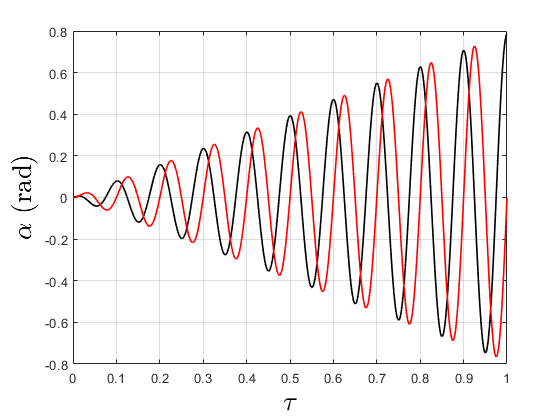

% Make functions numerical functions to plot the results
alpha_1_f = matlabFunction(alpha_1,'Vars',[n, tau, alpha_hat]);
alpha_2_f = matlabFunction(alpha_2,'Vars',[n, tau, alpha_hat]);
a_hat = pi/4; % the ankle limit that needs to be reached at the end of the spiral
numR = 10; % number of rotations to complete
t = linspace(0,1,100*numR);
alpha_1_t = alpha_1_f(numR, t, a_hat);
    alpha_2_t = alpha_2_f(numR, t, a_hat);

% Plot the signals individually
figure()
plot(t,alpha_1_t,'k','LineWidth',1.2);
hold on; grid on;
plot(t,alpha_2_t,'r','LineWidth',1.2);
xlabel('$\tau$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\alpha$ (rad)','Interpreter','latex','Color','k',FontSize=20);

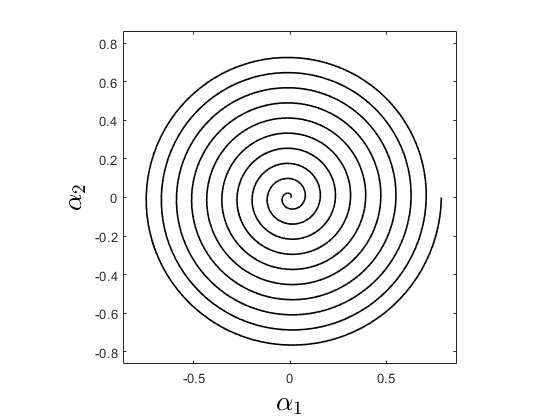

% Plot the path as a function of the shape space
figure()
plot(alpha_1_t,alpha_2_t,'k','LineWidth',1.2); axis equal; 
axis([-1.1*pi/4 1.1*pi/4 -1.1*pi/4 1.1*pi/4]);
xlabel('$\alpha_1$','Interpreter','latex','Color','k',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex','Color','k',FontSize=20);

Let's now write an external function based on the solver we wrote for the sprawl setup earlier.

### System Angular Velocity as a position dependent ODE

Let's obtain the connection on the system's rotation; here we shall redefine transforms and symbols as functions of time.

syms x y theta u v beta

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];
% We need to write this differently if we want to declare these as
% functions of time; sv stands for "select vector"
% sv_x = [1, 0, 0]; sv_y = [0, 1, 0]; sv_theta = [0, 0, 1];
% 
% sM_t_x = [zeros(3,2), [1, 0, 0]']; sM_t_y = [zeros(3,2), [0, 1, 0]'];
% sM_t_cos = [[1, 0, 0]; zeros(2,3)]; sM_t_sin = [zeros(1,3); [1, 0, 0]; zeros(2,3)];
% 
% v2M_SE2 = @(v) [cos(sv_theta*v), -sin(sv_theta*v), sv_x*v;
%                 sin(sv_theta*v),  cos(sv_theta*v), sv_y*v;
%                         0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);
% M2v_SE2 = @(M) simplify([sM_t_x*M; 
%                 sM_t_y*M;
%                 atan(sM_t_sin*M/sM_t_cos*M)], 'Steps', 10, ...
%                 'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';

syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real
syms gamma real
% assume(gamma < pi/2 && gamma >= 0); % nonnegative and range limited
% assumption

h_b__12b = [0, l, 0]';
h_b__34b = [0, -l, 0]';

h_12b__1b = [sqrt(2)*l*sin(gamma), 0, 0]';
h_12b__2b = [-sqrt(2)*l*sin(gamma), 0, pi]';
h_34b__3b = [-sqrt(2)*l*sin(gamma), 0, pi]';
h_34b__4b = [sqrt(2)*l*sin(gamma), 0, 0]';

syms alpha_i
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);

h_1b__1 = h_ib__i_func(a,l,alpha_1);
h_2b__2 = h_ib__i_func(a,l,alpha_2);
h_3b__3 = h_ib__i_func(a,l,alpha_3);
h_4b__4 = h_ib__i_func(a,l,alpha_4);

h_b__1b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b));
h_b__2b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b));
h_b__3b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b));
h_b__4b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b));

h_b__1 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1));
h_b__2 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2));
h_b__3 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3));
h_b__4 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4));

C = [eye(2,2),zeros(2,1)];
k_12 = simplify(C*(h_b__2 - h_b__1),'Steps',10)

$$k\_12 = \left(\begin{array}{c} -l\,\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)\\ -a\,l\,\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{2}\right)\right) \end{array}\right)$$

k_34 = simplify(C*(h_b__4 - h_b__3),'Steps',10)

$$k\_34 = \left(\begin{array}{c} l\,\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\,\sqrt{2}\,\sin\left(\gamma \right)\right)\\ a\,l\,\left(\sin\left(\alpha_{3}\right)+\sin\left(\alpha_{4}\right)\right) \end{array}\right)$$

We need to replace the variable with symbolick functions of time, and we do this in an elaborate manner.

syms delta beta_1 beta_2 beta_3 beta_4 real
k_12 = subs(k_12, [gamma, alpha_1, alpha_2], [delta, beta_1, beta_2])

$$k\_12 = \left(\begin{array}{c} -l\,\left(a\,\cos\left(\beta_{1}\right)+a\,\cos\left(\beta_{2}\right)+2\,\sqrt{2}\,\sin\left(\delta \right)\right)\\ -a\,l\,\left(\sin\left(\beta_{1}\right)+\sin\left(\beta_{2}\right)\right) \end{array}\right)$$

k_34 = subs(k_34, [gamma, alpha_3, alpha_4], [delta, beta_3, beta_4])

$$k\_34 = \left(\begin{array}{c} l\,\left(a\,\cos\left(\beta_{3}\right)+a\,\cos\left(\beta_{4}\right)+2\,\sqrt{2}\,\sin\left(\delta \right)\right)\\ a\,l\,\left(\sin\left(\beta_{3}\right)+\sin\left(\beta_{4}\right)\right) \end{array}\right)$$

% go back and add the symbolic functions
syms theta(t) gamma(t) alpha_1(t) alpha_2(t) alpha_3(t) alpha_4(t)
k_12 = subs(k_12, [delta, beta_1, beta_2] ,[gamma(t), alpha_1(t), alpha_2(t)])

$$k\_12 = \left(\begin{array}{c} -l\,\left(2\,\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{1}\left(t\right)\right)+a\,\cos\left(\alpha_{2}\left(t\right)\right)\right)\\ -a\,l\,\left(\sin\left(\alpha_{1}\left(t\right)\right)+\sin\left(\alpha_{2}\left(t\right)\right)\right) \end{array}\right)$$

k_34 = subs(k_34, [delta, beta_3, beta_4] ,[gamma(t), alpha_3(t), alpha_4(t)])

$$k\_34 = \left(\begin{array}{c} l\,\left(2\,\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{3}\left(t\right)\right)+a\,\cos\left(\alpha_{4}\left(t\right)\right)\right)\\ a\,l\,\left(\sin\left(\alpha_{3}\left(t\right)\right)+\sin\left(\alpha_{4}\left(t\right)\right)\right) \end{array}\right)$$

% Now, we can take derivatives with respect to time
k_dot_12 = diff(k_12)

$$k\_dot\_12 = \left(\begin{array}{c} l\,\left(a\,\sin\left(\alpha_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{1}\left(t\right)-2\,\sqrt{2}\,\cos\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)+a\,\sin\left(\alpha_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{2}\left(t\right)\right)\\ -a\,l\,\left(\cos\left(\alpha_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{1}\left(t\right)+\cos\left(\alpha_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{2}\left(t\right)\right) \end{array}\right)$$

k_dot_34 = diff(k_34)

$$k\_dot\_34 = \left(\begin{array}{c} -l\,\left(a\,\sin\left(\alpha_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{3}\left(t\right)-2\,\sqrt{2}\,\cos\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)+a\,\sin\left(\alpha_{4}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{4}\left(t\right)\right)\\ a\,l\,\left(\cos\left(\alpha_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{3}\left(t\right)+\cos\left(\alpha_{4}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{4}\left(t\right)\right) \end{array}\right)$$

Now, this can be used in conjunction with our analytical solution to obtain the change in systems orientation, $\dot{\theta}$.


$$\dot{\theta} = \cos^2{\theta} \frac{k_x \dot{k}_y - k_y \dot{k}_x}{k_{x}^2}$$


syms gamma_dot(t) alpha_dot_1(t) alpha_dot_2(t) alpha_dot_3(t) alpha_dot_4(t)
theta_dot_12 = collect(subs(cos(theta(t))^2 *(1/k_12(1)^2) *(k_12(1)*k_dot_12(2) - k_12(2)*k_dot_12(1)),...
    [diff(gamma(t), t) diff(alpha_1(t), t) diff(alpha_2(t), t)],...
    [gamma_dot(t) alpha_dot_1(t) alpha_dot_2(t)]),...
    [gamma_dot alpha_dot_1 alpha_dot_2])

$$theta\_dot\_12 = \begin{array}{l} \left(-\frac{2\,\sqrt{2}\,a\,\cos\left(\gamma \left(t\right)\right)\,\sigma_{2}\,\sigma_{1}}{{\sigma_{4}}^{2}}\right)\,\dot{\gamma }\left(t\right)+\frac{\sigma_{2}\,\left(a\,l^{2}\,\cos\left(\alpha_{1}\left(t\right)\right)\,\sigma_{4}+a^{2}\,l^{2}\,\sin\left(\alpha_{1}\left(t\right)\right)\,\sigma_{1}\right)}{\sigma_{3}}\,{\dot{\alpha }}_{1}\left(t\right)+\frac{\sigma_{2}\,\left(a\,l^{2}\,\cos\left(\alpha_{2}\left(t\right)\right)\,\sigma_{4}+a^{2}\,l^{2}\,\sin\left(\alpha_{2}\left(t\right)\right)\,\sigma_{1}\right)}{\sigma_{3}}\,{\dot{\alpha }}_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}\left(t\right)\right)+\sin\left(\alpha_{2}\left(t\right)\right)\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=l^{2}\,{\sigma_{4}}^{2}\\ \sigma_{4}=2\,\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{1}\left(t\right)\right)+a\,\cos\left(\alpha_{2}\left(t\right)\right) \end{array}$$

theta_dot_34 = collect(subs(cos(theta(t))^2 *(1/k_34(1)^2) *(k_34(1)*k_dot_34(2) - k_34(2)*k_dot_34(1)),...
    [diff(gamma(t), t) diff(alpha_3(t), t) diff(alpha_4(t), t)],...
    [gamma_dot(t) alpha_dot_3(t) alpha_dot_4(t)]),...
    [gamma_dot alpha_dot_3 alpha_dot_4])

$$theta\_dot\_34 = \begin{array}{l} \left(-\frac{2\,\sqrt{2}\,a\,\cos\left(\gamma \left(t\right)\right)\,\sigma_{2}\,\sigma_{1}}{{\sigma_{4}}^{2}}\right)\,\dot{\gamma }\left(t\right)+\frac{\sigma_{2}\,\left(a\,l^{2}\,\cos\left(\alpha_{3}\left(t\right)\right)\,\sigma_{4}+a^{2}\,l^{2}\,\sin\left(\alpha_{3}\left(t\right)\right)\,\sigma_{1}\right)}{\sigma_{3}}\,{\dot{\alpha }}_{3}\left(t\right)+\frac{\sigma_{2}\,\left(a\,l^{2}\,\cos\left(\alpha_{4}\left(t\right)\right)\,\sigma_{4}+a^{2}\,l^{2}\,\sin\left(\alpha_{4}\left(t\right)\right)\,\sigma_{1}\right)}{\sigma_{3}}\,{\dot{\alpha }}_{4}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{3}\left(t\right)\right)+\sin\left(\alpha_{4}\left(t\right)\right)\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=l^{2}\,{\sigma_{4}}^{2}\\ \sigma_{4}=2\,\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{3}\left(t\right)\right)+a\,\cos\left(\alpha_{4}\left(t\right)\right) \end{array}$$

We were able to collect all the terms we needed!

### System Translational Velocity as a position dependent ODE

Here, we extend our results from the previous section to also obtain the connection.

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';

syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real
syms gamma real
% assume(gamma < pi/2 && gamma >= 0); % nonnegative and range limited
% assumption

h_b__12b = [0, l, 0]';
h_b__34b = [0, -l, 0]';

h_12b__1b = [sqrt(2)*l*sin(gamma), 0, 0]';
h_12b__2b = [-sqrt(2)*l*sin(gamma), 0, pi]';
h_34b__3b = [-sqrt(2)*l*sin(gamma), 0, pi]';
h_34b__4b = [sqrt(2)*l*sin(gamma), 0, 0]';

syms alpha_i
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);

h_1b__1 = h_ib__i_func(a,l,alpha_1);
h_2b__2 = h_ib__i_func(a,l,alpha_2);
h_3b__3 = h_ib__i_func(a,l,alpha_3);
h_4b__4 = h_ib__i_func(a,l,alpha_4);

h_b__1b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b));
h_b__2b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b));
h_b__3b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b));
h_b__4b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b));

h_b__1 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1));
h_b__2 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2));
h_b__3 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3));
h_b__4 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4));

C = [eye(2,2),zeros(2,1)];

h_e__b = [u, v, beta]'

$$h\_e\_\_b = \left(\begin{array}{c} u\\ v\\ \beta \end{array}\right)$$

Now, we can evaluate the transforms to leg tips from a global rest frame and get the translational coordinates.

for i = 1:4
    eval(['h_e__' num2str(i) ' = M2v_SE2(v2M_SE2(h_e__b)*v2M_SE2(h_b__' num2str(i) '));'])
    eval(['k_' num2str(i) ' = C*h_e__' num2str(i) ';'])
end

Next, we can do the trick we used earlier to replace these terms as functions of time.

syms delta beta_1 beta_2 beta_3 beta_4
for i = 1:4
    eval(['k_' num2str(i) ' = subs(k_' num2str(i) ', [gamma alpha_' num2str(i) '], [delta beta_' num2str(i) ']);'])
end

Below, we can evaluate these equations as functions of time.

syms x(t) y(t) theta(t) gamma(t) alpha_1(t) alpha_2(t) alpha_3(t) alpha_4(t)
for i = 1:4
    eval(['k_' num2str(i) ' = subs(k_' num2str(i) ', [u v beta delta beta_' num2str(i) '], [x(t) y(t) theta(t) gamma(t) alpha_' num2str(i) '(t)])'])
end

$$k\_1 = \begin{array}{l} \left(\begin{array}{c} x\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}-l\,\sin\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{1}\left(t\right)\right)+1\right)\\ y\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{1}\left(t\right)\right)+1\right)+l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{1}\left(t\right)\right) \end{array}$$

$$k\_2 = \begin{array}{l} \left(\begin{array}{c} x\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+l\,\sin\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{2}\left(t\right)\right)-1\right)\\ y\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{2}\left(t\right)\right)-1\right)-l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{2}\left(t\right)\right) \end{array}$$

$$k\_3 = \begin{array}{l} \left(\begin{array}{c} x\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+l\,\sin\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{3}\left(t\right)\right)+1\right)\\ y\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{3}\left(t\right)\right)+1\right)-l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{3}\left(t\right)\right) \end{array}$$

$$k\_4 = \begin{array}{l} \left(\begin{array}{c} x\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}-l\,\sin\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{4}\left(t\right)\right)-1\right)\\ y\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\left(a\,\sin\left(\alpha_{4}\left(t\right)\right)-1\right)+l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{4}\left(t\right)\right) \end{array}$$

This can now be differentiated to obtain the required translational velocity rates!

syms x_dot(t) y_dot(t) theta_dot(t) gamma_dot(t) alpha_dot_1(t) alpha_dot_2(t) alpha_dot_3(t) alpha_dot_4(t)
for i = 1:4
    eval(['k_dot_' num2str(i) ' = collect(subs(diff(k_' num2str(i) '), [diff(x(t), t) diff(y(t), t) diff(theta(t), t) diff(gamma(t), t) diff(alpha_' num2str(i) '(t), t)],' ...
     '[x_dot(t) y_dot(t) theta_dot(t) gamma_dot(t) alpha_dot_' num2str(i) '(t)]), [x_dot(t) y_dot(t) theta_dot(t) gamma_dot(t) alpha_dot_' num2str(i) '(t)])'])
end

$$k\_dot\_1 = \begin{array}{l} \left(\begin{array}{c} \dot{x}\left(t\right)+\left(-l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}-l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,\dot{\theta }\left(t\right)+\left(\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(-a\,l\,\cos\left(\alpha_{1}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-a\,l\,\sin\left(\alpha_{1}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{1}\left(t\right)\\ \dot{y}\left(t\right)+\left(l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}-l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}\right)\,\dot{\theta }\left(t\right)+\left(\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(a\,l\,\cos\left(\alpha_{1}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-a\,l\,\sin\left(\alpha_{1}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{1}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{1}\left(t\right)\right)\\ \sigma_{2}=a\,\sin\left(\alpha_{1}\left(t\right)\right)+1 \end{array}$$

$$k\_dot\_2 = \begin{array}{l} \left(\begin{array}{c} \dot{x}\left(t\right)+\left(l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}+l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,\dot{\theta }\left(t\right)+\left(-\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(a\,l\,\cos\left(\alpha_{2}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+a\,l\,\sin\left(\alpha_{2}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{2}\left(t\right)\\ \dot{y}\left(t\right)+\left(l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,\dot{\theta }\left(t\right)+\left(-\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(a\,l\,\sin\left(\alpha_{2}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-a\,l\,\cos\left(\alpha_{2}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{2}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{2}\left(t\right)\right)\\ \sigma_{2}=a\,\sin\left(\alpha_{2}\left(t\right)\right)-1 \end{array}$$

$$k\_dot\_3 = \begin{array}{l} \left(\begin{array}{c} \dot{x}\left(t\right)+\left(l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}+l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,\dot{\theta }\left(t\right)+\left(-\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(a\,l\,\cos\left(\alpha_{3}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+a\,l\,\sin\left(\alpha_{3}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{3}\left(t\right)\\ \dot{y}\left(t\right)+\left(l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,\dot{\theta }\left(t\right)+\left(-\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(a\,l\,\sin\left(\alpha_{3}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-a\,l\,\cos\left(\alpha_{3}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{3}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{3}\left(t\right)\right)\\ \sigma_{2}=a\,\sin\left(\alpha_{3}\left(t\right)\right)+1 \end{array}$$

$$k\_dot\_4 = \begin{array}{l} \left(\begin{array}{c} \dot{x}\left(t\right)+\left(-l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}-l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,\dot{\theta }\left(t\right)+\left(\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(-a\,l\,\cos\left(\alpha_{4}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-a\,l\,\sin\left(\alpha_{4}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{4}\left(t\right)\\ \dot{y}\left(t\right)+\left(l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}-l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}\right)\,\dot{\theta }\left(t\right)+\left(\sqrt{2}\,l\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\,\dot{\gamma }\left(t\right)+\left(a\,l\,\cos\left(\alpha_{4}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-a\,l\,\sin\left(\alpha_{4}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\,{\dot{\alpha }}_{4}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\sin\left(\gamma \left(t\right)\right)+a\,\cos\left(\alpha_{4}\left(t\right)\right)\\ \sigma_{2}=a\,\sin\left(\alpha_{4}\left(t\right)\right)-1 \end{array}$$

Iterate over the number of ***viable*** contact states to obtain the average translational velocity ODEs.

for j = 1:2 % tried this and realized the gamma dot terms cancelled out; lets use this to complete our solver
    eval(['k_dot_' num2str(2*j-1) num2str(2*j) ' = collect(simplify(0.5*(k_dot_' num2str(2*j-1) ' + k_dot_' num2str(2*j)...
        '), Steps=10), [theta_dot(t) gamma_dot(t) alpha_dot_' num2str(2*j-1) '(t) alpha_dot_' num2str(2*j) '(t)])'])
end

$$k\_dot\_12 = \begin{array}{l} \left(\begin{array}{c} \dot{x}\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\dot{\theta }\left(t\right)-\frac{a\,l\,\sin\left(\sigma_{2}\right)\,{\dot{\alpha }}_{1}\left(t\right)}{2}+\frac{a\,l\,\sin\left(\sigma_{1}\right)\,{\dot{\alpha }}_{2}\left(t\right)}{2}-\frac{a\,l\,\sin\left(\sigma_{2}\right)\,\dot{\theta }\left(t\right)}{2}+\frac{a\,l\,\sin\left(\sigma_{1}\right)\,\dot{\theta }\left(t\right)}{2}\\ \dot{y}\left(t\right)-l\,\sin\left(\theta \left(t\right)\right)\,\dot{\theta }\left(t\right)+\frac{a\,l\,\cos\left(\sigma_{2}\right)\,{\dot{\alpha }}_{1}\left(t\right)}{2}-\frac{a\,l\,\cos\left(\sigma_{1}\right)\,{\dot{\alpha }}_{2}\left(t\right)}{2}+\frac{a\,l\,\cos\left(\sigma_{2}\right)\,\dot{\theta }\left(t\right)}{2}-\frac{a\,l\,\cos\left(\sigma_{1}\right)\,\dot{\theta }\left(t\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha_{2}\left(t\right)+\theta \left(t\right)\\ \sigma_{2}=\alpha_{1}\left(t\right)+\theta \left(t\right) \end{array}$$

$$k\_dot\_34 = \begin{array}{l} \left(\begin{array}{c} \dot{x}\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\dot{\theta }\left(t\right)+\frac{a\,l\,\sin\left(\sigma_{2}\right)\,{\dot{\alpha }}_{3}\left(t\right)}{2}-\frac{a\,l\,\sin\left(\sigma_{1}\right)\,{\dot{\alpha }}_{4}\left(t\right)}{2}+\frac{a\,l\,\sin\left(\sigma_{2}\right)\,\dot{\theta }\left(t\right)}{2}-\frac{a\,l\,\sin\left(\sigma_{1}\right)\,\dot{\theta }\left(t\right)}{2}\\ \dot{y}\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\dot{\theta }\left(t\right)-\frac{a\,l\,\cos\left(\sigma_{2}\right)\,{\dot{\alpha }}_{3}\left(t\right)}{2}+\frac{a\,l\,\cos\left(\sigma_{1}\right)\,{\dot{\alpha }}_{4}\left(t\right)}{2}-\frac{a\,l\,\cos\left(\sigma_{2}\right)\,\dot{\theta }\left(t\right)}{2}+\frac{a\,l\,\cos\left(\sigma_{1}\right)\,\dot{\theta }\left(t\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha_{4}\left(t\right)+\theta \left(t\right)\\ \sigma_{2}=\alpha_{3}\left(t\right)+\theta \left(t\right) \end{array}$$

% eval(['syms alpha_' num2str(1) ' alpha_' num2str(2) ' real'])

rmat = [1, 2;
        2, 3;
        3, 4;
        4, 1;
        1, 3;
        2, 4];
cs1 = 1; cs2 = 4;
rmat == cs1
rmat == cs2
(rmat == cs1) + (rmat == cs2)

ans = 6×2 logical array
   1   0
   0   0
   0   0
   0   1
   1   0
   0   0


sum((rmat == cs1) + (rmat == cs2),2)

ans = 6×2 logical array
   0   0
   0   0
   0   1
   1   0
   0   0
   0   1


find(sum((rmat == cs1) + (rmat == cs2),2) == 2)

ans =      1     0
     0     0
     0     1
     1     1
     1     0
     0     1


T = linspace(0,1,1000); % test the shape space bounds code for level-2 submanifolds in the case 1 system

ans =      1
     0
     1
     2
     1
     1


figure('units','pixels','position',[0 0 1920 1080],'Color','w')

ans = 4

plot(T,s(1)*sin(2*pi*(T - 1/s(2)))+s(3),'r','linewidth',1.2);
hold on; grid on;
yline(ank); yline(-ank);

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Here, I'm plotting the collection of velocities of the stratified panel first as a two-dimensional set of translational velocities. 

Then we shall obtain a plot for the displacement of such a system.

dnum = 101;
am = linspace(-pi/2, pi/2, dnum); ap = am; [am, ap] = meshgrid(am, ap);
amlimits = [ -pi/2, pi/2 ]; aplimits = amlimits;
dzIdotJ = thisAltGait.stanceSpace.dzIdotJ;
scatterLoc = thisAltGait.stanceSpace.a_dzThNull;
cfLvl = dnum; 
lW_contour = 0.4;
CUB = flipud([159.3750,99.6030,63.4312;
          239.0625,149.4045,95.1469;
          255.0000,199.2060,126.8625;
            204,204,204;
            150,150,150;
            99,99,99])/255; % define CUB colormap and interpolate for more colors
CUB = interpColorAndCondition((1:size(CUB, 1))', CUB, ... % X, V
    (linspace(1, size(CUB, 1), size(turbo, 1)))'); % Xq
fS = 25;
dot_title_txt = 'dz_{B}'; 
xTxt = '$$\alpha^{-}$$';
yTxt = '$$\alpha^{+}$$';
f = figure('units', 'pixels', 'position', [0 0 600 600], ...
    'Color','w'); set(f,'Visible','on'); ax = gca;
contourf(ax, am, ap, dzIdotJ, cfLvl, 'LineStyle', 'none');
axis equal tight; hold on; colormap(CUB);
thresh_value = 0.99; % 0.95 % 0.99 % 0.999
contour(ax, am, ap, dzIdotJ, thresh_value*ones(1, 2),...
    'k--','LineWidth',lW_contour+1); % , 'ShowText', 'on'
contour(ax, am, ap, dzIdotJ, -thresh_value*ones(1, 2),...
    'k--','LineWidth',lW_contour+1); % , 'ShowText', 'on'
scatter(ax, scatterLoc(1), scatterLoc(2), 100, "+",...
    'MarkerEdgeColor','k', 'LineWidth', lW_contour+1);
xlabel(ax, xTxt, "FontSize", fS);
ylabel(ax, yTxt, "FontSize", fS);
ax.XColor = thisAltGait.ithStance.p_info.gc_col; 
ax.YColor = thisAltGait.jthStance.p_info.gc_col;
title(ax, dot_title_txt, 'Color', 'k', FontSize=fS);
ax.XAxis.FontSize = fS; ax.YAxis.FontSize = fS; 
xlim(amlimits); ylim(aplimits); clim([-1, 1]);
colorbar(ax, 'FontSize', fS, 'TickLabelInterpreter', 'latex', ...
                                        'Ticks', [-1, 0, 1]);